# **Macroeconometrics: Advanced Time-Series Project**

# **Giovanni Manche & Timothée Dangleterre**

## Work based on the paper: When does Monetary Policy Matter? Policy Stance vs. Term Premium News

### Cleaning and imports

clear; clc; clearvars;
addpath('data');
addpath('graphs\plot_functions');
addpath('regressions');
addpath('utils');

## 1. Replication of the main results of the paper

### *1.1. The standard effects of monetary policy surprises*

#### 1.1.1. Monetary policy surprises and Target and Path factors

The authors start by presenting the event-study approach results about the effects of monetary policy surprises (MPS) on: 

- stock prices (S&P 500)

- Treasury nominal yields (zero coupon nominal interest rates at 2, 5, 10Y)

They consider the *news-adjusted* measure of MPS of Bauer & Swanson (2023) and use the Target and Path surprises estimated by Acosta, Brennan and Jacobson (2024), focusing on MP annoucenements following the scheduled FOMC meetings between 1999 and 2022.

% Import of the FOMC MPS data (Bauer & Swanson) and Path/Target factors (ABJ)
raw_dataset_mps = readtable("data\FOMC_surprises_Bauer_Swanson", "Sheet", "FOMC (update 2023)");

raw_dataset_abj = readtable("data\ABJ_2024_Path_Target.xlsx", "Sheet", "Data");

% Restrain over 1999-2022 + scheduled 
raw_dataset_mps.Date = datetime(raw_dataset_mps.Date);
raw_dataset_abj.Date = datetime(raw_dataset_abj.Date);
mask = raw_dataset_mps.Date>= datetime(1999,1,1) & raw_dataset_mps.Date <= datetime(2022,12,31) ...
    & raw_dataset_mps.Unscheduled == 0;
dataset_mps = raw_dataset_mps(mask,:);

% We merge B&S's MPSs with ABJ's estimated factors, and keep the subset of
% the merged table 
dataset_merged = innerjoin(dataset_mps, raw_dataset_abj, 'Keys', 'Date');
mps_base = dataset_merged(:, ["Date", "MPS_ORTH", "GSS_target", "GSS_path"]);
mps_base.Properties.VariableNames = ["Dates", "MPS", "Target", "Path"];
% If there are missing values for adjusted to news MPS, we replace the
% missing values by the unadjusted MPS
mps_base.MPS(isnan(mps_base.MPS)) = dataset_merged.MPS(isnan(mps_base.MPS));
fprintf("Number of FOMC announcements: %d\n", size(mps_base,1));

Number of FOMC announcements: 191


Over the 1999-2022 period, we have 191 scheduled FOMC annoucements, while the authors have 188. We decide to keep them all. 

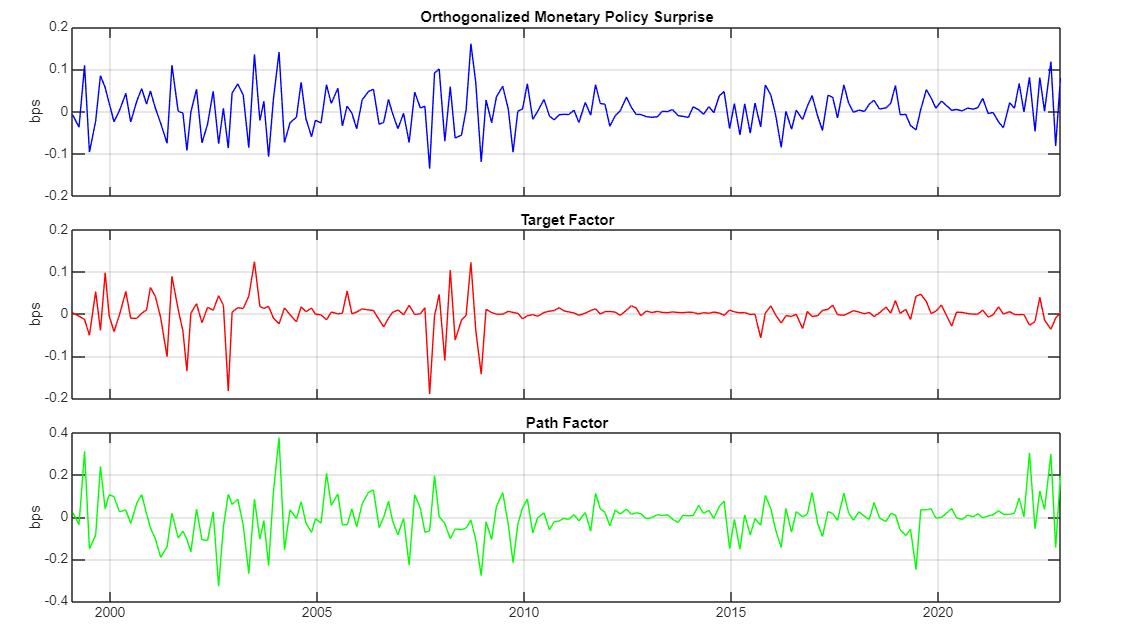

% We plot the series
f0 = figure("Units","normalized","Position",[0,0,1,1]);
t = tiledlayout(3,1,'Padding','compact','TileSpacing','compact');
nexttile
plot(mps_base.Dates, mps_base.MPS,'b'); title("Orthogonalized Monetary Policy Surprise");
ylabel("bps"); xticklabels({}); grid on;
nexttile
plot(mps_base.Dates, mps_base.Target,'r'); title("Target Factor");
ylabel("bps"); xticklabels({}); grid on;
nexttile
plot(mps_base.Dates, mps_base.Path, 'g'); title("Path Factor");
ylabel("bps"); grid on;
exportgraphics(f0, 'graphs/factors.pdf', 'ContentType', 'vector');

#### 1.1.2. Event-study

We assess the effect of MPSs on asset prices and zero coupon yields via the two following regressions:

- 
$$\Delta Y_t = \alpha + \beta_{MPS} . MPS_t + \varepsilon_t$$


- 
$$\Delta y_t = \alpha + \beta_t . Target_t + \beta_P . Path_t + \varepsilon_t$$


With $\Delta y_t$ the daily change in a given asset price or ZC nominal interest rates on 2,5 and 10 year maturities.  We got the daily SP500 close price from Yahoo Finance and the ZC nominal yields from Gürkaynak, Sack and Wright (available from Fed website)

% SP500 daily log-returns
raw_dataset_sp500 = readtable("data\sp500_daily.xlsx");

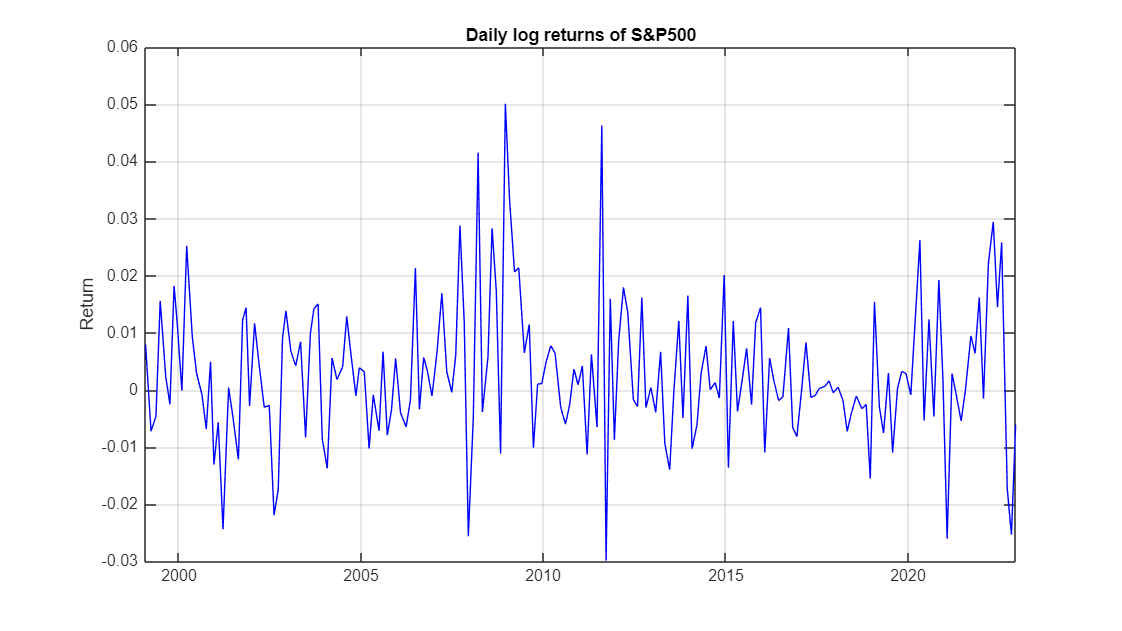

sp500_ret = diff(log(raw_dataset_sp500.GSPC_Close),1);
sp500_dataset = table(raw_dataset_sp500.Date(2:length(raw_dataset_sp500.Date)),...
    sp500_ret, 'VariableNames',{'Dates','SP500_returns'});

% Outerjoin to make sure that if data is missing from sp500_dataset, it
% won't affect the other columns of mps_base.
mps_base = outerjoin(mps_base, sp500_dataset, 'Keys', 'Dates', 'MergeKeys', true, 'Type', 'left');

% Plot
f1 = figure("Units","normalized","Position",[0,0,1,1]);
plot(mps_base.Dates, mps_base.SP500_returns, 'b'); title("Daily log returns of S&P500");
ylabel('Return'); grid on;
exportgraphics(f1, 'graphs/SP500.pdf', 'ContentType', 'vector');

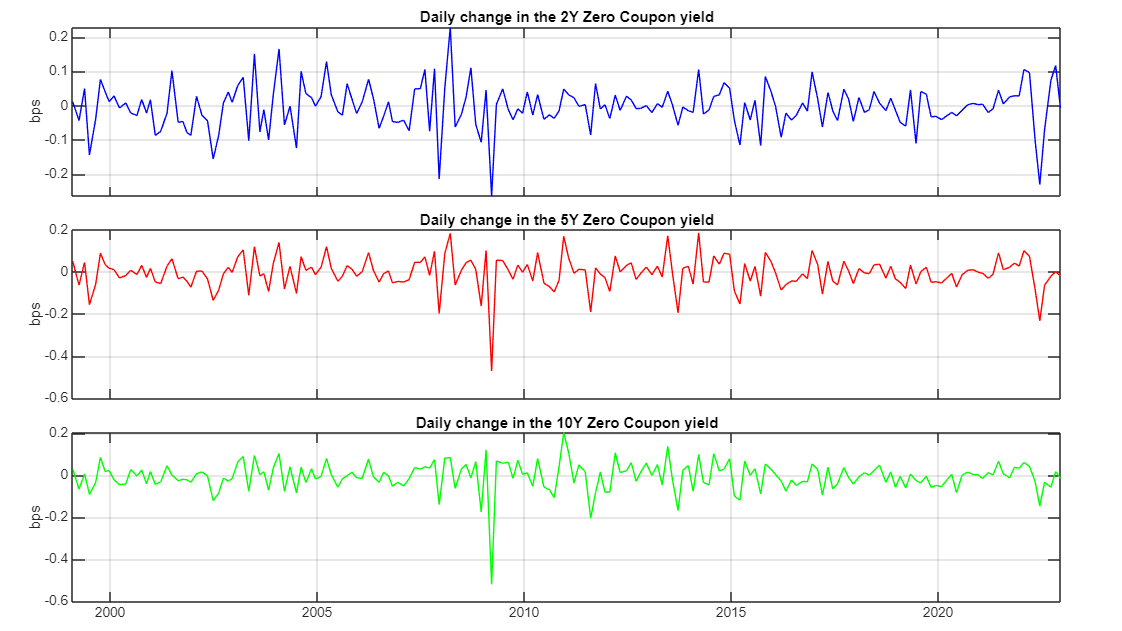

% Import Gurkaynak, Sack and Wright data (available from Fed website)
raw_dataset_gsw = readtable("data\GSW_feds200628.xlsx");
raw_dataset_gsw.Date = datetime(raw_dataset_gsw.Date, 'InputFormat', 'yyyy-MM-dd');

% Keep only values for 2, 5 and 10 year on from 1999-2022
dataset_yields = raw_dataset_gsw(raw_dataset_gsw.Date >= '01-Jan-1999' & raw_dataset_gsw.Date < '01-Jan-2023', ...
    ["Date", "SVENY02","SVENY05","SVENY10"]);

% Compute the daily change in nominal yields
yields_diff = diff(dataset_yields{:, 2:end}); 

% Create table 
yield_base = table(dataset_yields.Date(2:end), yields_diff(:,1), yields_diff(:,2), yields_diff(:,3), ...
    'VariableNames',{'Dates', 'Diff2y', 'Diff5y', 'Diff10y'});

% Merge into mps_base using Left Join
mps_base = outerjoin(mps_base, yield_base, 'Keys', 'Dates', 'MergeKeys', true, 'Type', 'left');

% Plot 
f2 = figure("Units","normalized","Position",[0,0,1,1]);
t = tiledlayout(3,1,'Padding','compact','TileSpacing','compact');
nexttile
plot(mps_base.Dates, mps_base.Diff2y,'b'); title("Daily change in the 2Y Zero Coupon yield");
ylabel("bps"); xticklabels({}); grid on;

nexttile
plot(mps_base.Dates, mps_base.Diff5y,'r'); title("Daily change in the 5Y Zero Coupon yield");
ylabel("bps"); xticklabels({}); grid on;

nexttile
plot(mps_base.Dates, mps_base.Diff10y, 'g'); title("Daily change in the 10Y Zero Coupon yield");
ylabel("bps"); grid on;
exportgraphics(f2, 'graphs/changes_in_ZC_yields.pdf', 'ContentType', 'vector');

We now conduct the regressions (endogenous variables are in basis points). It corresponds to table 1 in the paper.

Y_assets = [mps_base.SP500_returns*100, mps_base.Diff2y, mps_base.Diff5y, mps_base.Diff10y];
X_mps = mps_base.MPS;
X_tp = [mps_base.Target, mps_base.Path];

disp("========== STANDARD MP EFFECTS ==========")

========== STANDARD MP EFFECTS ==========


display_regression_results(Y_assets, {X_mps, X_tp}, ...
    'YNames', {'SP500', '2y', '5y', '10y'}, ...
    'XNames', {{'MPS'}, {'Target', 'Path'}}, ...
    'SpecNames', {'Baseline', 'Decomposition'}, ...
    'Title', 'Table 1: Standard Monetary Policy effects');


Table 1: Standard Monetary Policy effects

======= Baseline ======= 

               SP500        2y         5y         10y   
              ________    _______    _______    ________

    MPS        -4.6071    0.64176    0.55212     0.30639
    se_MPS      2.3591    0.11422    0.11613     0.10465
    R2        0.032556    0.22373    0.12145    0.043564
    Obs            191        191        191         191


P-values:
                 SP500          2y            5y           10y   
                ________    __________  

Compared to the paper:

- The coefficient associated with the S&P 500 is always found to be significative at 5%

- With the MPS regression, all the coefficients associated with the yield are found to be significative at the 0.01 threshold

- With the path / target regression: target is only significative for the 2 year ZC, while Path is highly significative for all ZC.

Similarly to what the authors note, the R-squared explain only a small fraction of the variance of these asset prices, even though FOMC should be the main market mover of bond yields.

### *1.2. Target and Path surprises do not discriminate *future *policy*

The authors, in order to better grasp the information conveyed by the Target and Path surprises, run the following regressions on each of the federal funds/ Eurodollar futures contracts $F_t^k$ used to construct MPS and their decomposition:


$$\Delta F_t^k = \alpha + \beta_{MPS} \cdot MPS_t + \epsilon_t$$
 


$$\Delta F_t^k = \alpha + \beta_{T} \cdot Target_t + \epsilon_t$$



$$\Delta F_t^k = \alpha + \beta_{P} \cdot Path_t + \epsilon_t$$
    

% For clarity and safety, we constitute a new table composed of the elements we need
FF_eurodollar_base = table(mps_base.Dates, mps_base.MPS, mps_base.Target, mps_base.Path, ...
    mps_base.Target + mps_base.Path, dataset_merged.FF1, dataset_merged.ED1, dataset_merged.ED2,...
    dataset_merged.ED3, dataset_merged.ED4);
FF_eurodollar_base.Properties.VariableNames = ["Dates", "MPS_BS", "Target", "Path", "MPS_GSS",...
    "FF1", "ED1", "ED2", "ED3", "ED4"];
% There are "NA" values (considered as text by MATLAB)
varsRates = ["FF1","ED1","ED2","ED3","ED4"];
for v = varsRates
    FF_eurodollar_base.(v) = str2double(string(FF_eurodollar_base.(v)));
end
disp(sum(isnan(FF_eurodollar_base{:, varsRates})));

    88     0     0     0     0



In the dataset at our disposal (from Bauer & Swanson), we do not have data about FF1 until 2010. We ignore it for now.


 RÉSULTATS POUR L'ACTIF : ED1
      Modele       Coef         SE        P_Value        Sig        R2   
    __________    _______    ________    __________    _______    _______

    {'GSS'   }    0.30758    0.040463     2.931e-14    {'***'}     0.5517
    {'BS'    }    0.72297    0.076678             0    {'***'}    0.64602
    {'Target'}     0.8703     0.11104    4.6629e-15    {'***'}     0.5425
    {'Path'  }    0.22614     0.03973     1.256e-08    {'***'}    0.26465


 RÉSULTATS POUR L'ACTIF : ED2
      Modele       Coef         SE        P_Value   

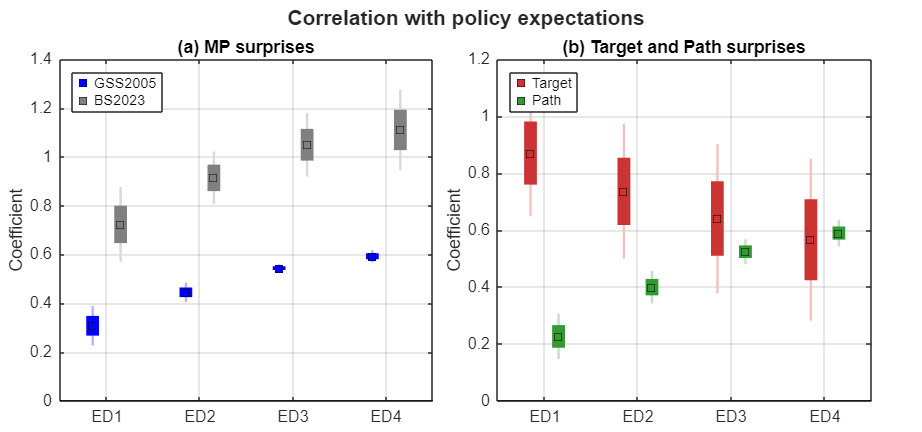

plot_ci(FF_eurodollar_base(:, FF_eurodollar_base.Properties.VariableNames ~= "FF1"))

Results obtained are different from those of the authors, which may be due to the nature of the data: we have intraday changes in Eurodollars, while they use daily changes. Nonetheless, the results we obtain can be interpreted the same way as the authors: target surprises reflect information about both the current and the future policy stance while path surprises seem to only convey information about future stance.

### *1.3. Policy stance vs. high-order moments news*

The authors argue that the "information about the future" contained in the Target factor is a first-order moment news about future policy, i.e. information directly concerning future MP stance. The information contained in the Path factor is by construction orthogonal to that; they argue it conveys higher-order moments surronding the expected policy path (= uncertainty about the policy). In line with standard term structure theory:

- the "information about the future" contained in the Target factor is linked to the expectation of future policy rates

- the information contained in the Path factor is linked to the term premium

If Target and Path are of opposite sign, it means that hawkish / dovish surprises do not have the same effect on the entire term structure. It could induce arbitrage if term premium doesn't adjust. Same-sign Target-Path shocks identify standard policy stance transmission, whereas opposite-sign shocks reveal changes in uncertainty and term premia, allowing identification of higher-order moment news.


 RÉSULTATS POUR L'ACTIF : ED1
      Modele       Coef         SE        P_Value        Sig        R2   
    __________    _______    ________    __________    _______    _______

    {'GSS'   }    0.16957    0.026196    9.5907e-11    {'***'}    0.43382
    {'BS'    }    0.46644    0.069466    1.8846e-11    {'***'}    0.63644
    {'Target'}    0.32562     0.16183      0.044208    {'**' }    0.12818
    {'Path'  }    0.11735    0.022192    1.2365e-07    {'***'}    0.25403


 RÉSULTATS POUR L'ACTIF : ED2
      Modele        Coef          SE       P_Value  

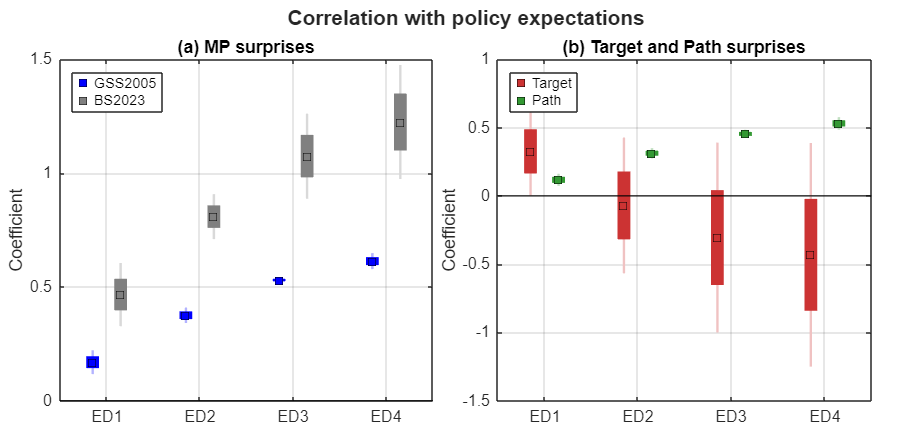

% We create indicators corresponding to opposite signs (and for later, to
% attenuation and high-order moments)
[indic_opp, indic_att, indic_hom] = classifier_mp_events(mps_base);
plot_ci(FF_eurodollar_base(indic_opp, FF_eurodollar_base.Properties.VariableNames ~= "FF1"))

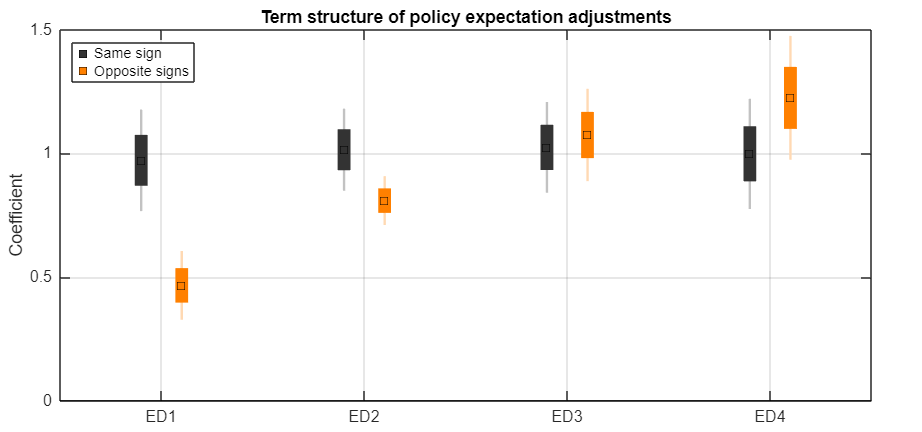

plot_figure2(FF_eurodollar_base(:, FF_eurodollar_base.Properties.VariableNames ~= "FF1"), indic_opp);

We again do not have exactly the same values as the authors but the same interpretation. 

### *1.4. Monetary policy transmission with same vs. opposite signs*

To analyze the importance of the "opposite sign" element, the following regression is conducted:


$$\Delta Y_t = \alpha + \beta_1 MPS_t + \beta_2 \cdot MPS_t \cdot \mathbb{1}_t^{Opp} + \beta_3 \cdot \mathbb{1}_t^{Opp} + \epsilon_t$$


X_opp = [mps_base.MPS mps_base.MPS.* indic_opp indic_opp];
display_regression_results(Y_assets, {X_opp}, ...
    'YNames', {'SP500', '2y', '5y', '10y'}, ...
    'XNames', {{'MPS', 'MPS x indic_opp', 'indic_opp'}}, ...
    'Title', 'Table 2: Monetary Policy effects with same or opposite sign');


Table 2: Monetary Policy effects with same or opposite sign

======= Spec1 ======= 

                           SP500         2y            5y           10y    
                          ________    _________    __________    __________

    MPS                    -7.5437       0.3952       0.29023      0.065616
    se_MPS                  3.4447      0.19463       0.18754        0.1606
    MPS x indic_opp         5.8596      0.49626       0.52987        0.4871
    se_MPS x indic_opp      4.4966      0.22305       0.23472        0.2146
    indic_opp              0.18951    0.0038197    -0.0037574    -0.003270

We again obtain very similar results to those of the authors (our standard errors are slightly different though).

The authors also compute descriptive statics for monetary surprises based on the signs

% Table for descriptive statistics result (Table 3 of the paper)
same_sign_mps = mps_base(indic_opp==0,:); 
opposite_sign_mps = mps_base(indic_opp,:);
rowNames = {'Same Signs','Opposite Signs'};
colNames = {'N','%','Mean','Mean Abs','SD'};
table3 = array2table(nan(numel(rowNames), numel(colNames)), ...
                'RowNames', rowNames, ...
                'VariableNames', colNames);
table3{1,:} = [height(same_sign_mps), ...
               round(100 * height(same_sign_mps) / height(mps_base), 1), ...
               round(mean(same_sign_mps.MPS), 3), ...
               round(mean(abs(same_sign_mps.MPS)), 3), ...
               round(std(same_sign_mps.MPS), 3)];

table3{2,:} = [height(opposite_sign_mps), ...
               round(100 * height(opposite_sign_mps) / height(mps_base), 1), ...
               round(mean(opposite_sign_mps.MPS), 3), ...
               round(mean(abs(opposite_sign_mps.MPS)), 3), ...
               round(std(opposite_sign_mps.MPS), 3)];

disp('Table 3: Descriptive Statistics');

Table 3: Descriptive Statistics


disp(table3)

                       N      %      Mean     Mean Abs     SD  
                      ___    ____    _____    ________    _____

    Same Signs         90    47.1    0.004     0.038       0.05
    Opposite Signs    101    52.9    0.005     0.032      0.046



The standard deviation we have are slightly higher, but overall, our descriptive statistics are in line with those reported by the authors.

### *1.5. Monetary policy transmission with high-order moment signals*

We now move to the following distinctions:

- attenuation statements: when Target and Path have different signs and Target's magnitude is larger than Path surprise's one,  then the variation in the slope of the term structure of anticipations is mostly due to the policy stance shock

- high-order moment statements: when Target and Path have different signs and Target's magnitude is smaller than Path surprise's one, then the variation in the slope of the term structure of anticipations is mostly due to the uncertainty shock.

They run the following regression to analyze the heterogenous transmission of monetary policy on asset prices:


$$\Delta Y_t = \alpha + \beta_1 MPS_t + \beta_2 MPS_t \cdot 1_t^{Att} + \beta_3 MPS_t \cdot 1_t^{HOM} + \beta_4 \cdot 1_t^{Att} + \beta_5 \cdot 1_t^{HOM} + \epsilon_t$$


X_att_hom = [mps_base.MPS mps_base.MPS.* indic_att mps_base.MPS.* indic_hom indic_att indic_hom];
const = ones(height(mps_base), 1);
display_regression_results(Y_assets, {X_att_hom}, ...
    'YNames', {'SP500', '2y', '5y', '10y'}, ...
    'XNames', {{'MPS', 'MPS x indic_att', 'MPS x indic_hom', 'indic_att', 'indic_hom'}}, ...
    'Title', 'Table 4: Monetary Policy effects with higher-order moment signals');


Table 4: Monetary Policy effects with higher-order moment signals

======= Spec1 ======= 

                            SP500          2y            5y           10y    
                          _________    __________    __________    __________

    MPS                     -7.5437        0.3952       0.29023      0.065616
    se_MPS                   3.4447       0.19463       0.18754        0.1606
    MPS x indic_att          13.492          0.14     -0.012244     -0.039605
    se_MPS x indic_att       7.3136       0.32624       0.28432       0.25482
    MPS x indic_hom           4.349       0.54927       


% Marginal effects of MPS depending on the type of statement

colNames = {'SP500', '2y', '5y', '10y'}; 
% Attenuation statements
rowNames_Att = {'Marginal_Att', 'se_att'};
table_me_att = array2table(nan(2, length(colNames)), ...
    'RowNames', rowNames_Att, 'VariableNames', colNames);
table_me_att = me_results(Y_assets, [const X_att_hom], table_me_att, [2, 3]);

% HOM statements
rowNames_Hom = {'Marginal_Hom', 'se_hom'};
table_me_hom = array2table(nan(2, length(colNames)), ...
    'RowNames', rowNames_Hom, 'VariableNames', colNames);
table_me_hom = me_results(Y_assets, [const X_att_hom], table_me_hom, [2, 4]);
disp('===== Marginal Effect: Attenuation ====');

===== Marginal Effect: Attenuation ====


disp(table_me_att);

                    SP500     2y       5y       10y 
                    _____    _____    _____    _____

    Marginal_Att    5.948    0.535    0.278    0.026
    se_att          6.452    0.262    0.214    0.198




disp('==== Marginal Effect: HOM ====');

==== Marginal Effect: HOM ====


disp(table_me_hom);

                    SP500      2y       5y       10y 
                    ______    _____    _____    _____

    Marginal_Hom    -3.195    0.944    0.918    0.661
    se_hom           2.895      0.1    0.147    0.152




% R2 on the subsamples
[~, ~, r2_same, n_same] = robust_ols(Y_assets(~indic_opp,:), mps_base.MPS(~indic_opp), true);
[~, ~, r2_att, n_att] = robust_ols(Y_assets(indic_att,:), mps_base.MPS(indic_att), true);
[~, ~, r2_hom, n_hom] = robust_ols(Y_assets(indic_hom,:), mps_base.MPS(indic_hom), true);

results_r2_subsamples = [r2_same; r2_att; r2_hom; repmat(height(Y_assets), 1, width(Y_assets))];
rowNamesR2 = {'R2 Same Sign', 'R2 Att', 'R2 HOM', 'Obs'};
table_r2_final = array2table(results_r2_subsamples, 'RowNames', rowNamesR2, 'VariableNames', colNames);
disp(' ==== R2 Decomposition ====');

 ==== R2 Decomposition ====


disp(table_r2_final);

                     SP500         2y          5y          10y    
                    ________    ________    ________    __________

    R2 Same Sign    0.092777    0.095942     0.04866     0.0033346
    R2 Att          0.042983     0.15205    0.037154    0.00039435
    R2 HOM          0.015587     0.44841     0.23907       0.13062
    Obs                  191         191         191           191



We now seek to analyze the differentiated effects of HOM statements VS other statements on changes in Treasury yields

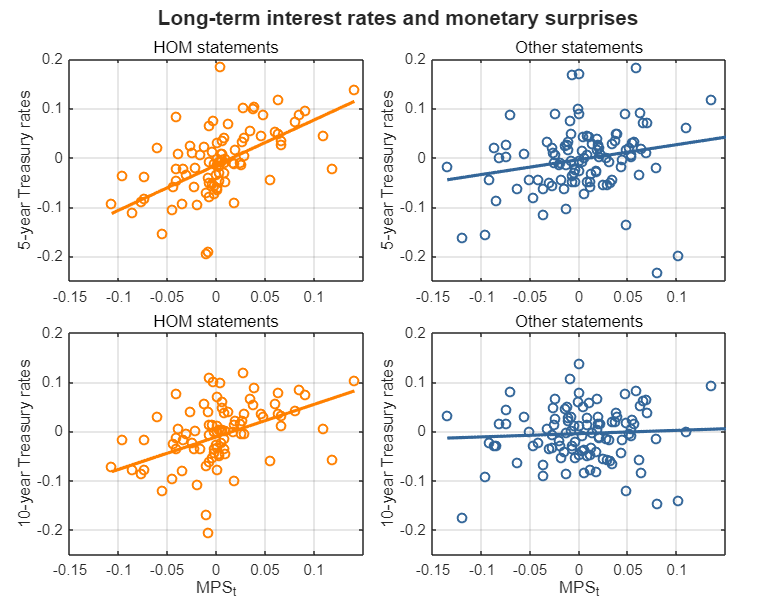

nominal_yields_base = raw_dataset_gsw(raw_dataset_gsw.Date > '01-Jan-1999' & ...
raw_dataset_gsw.Date < '01-Jan-2023', ...
    ["Date", "SVENY01", "SVENY02", ...
    "SVENY03", "SVENY04", "SVENY05", "SVENY06", ...
    "SVENY07", "SVENY08", "SVENY09", "SVENY10", ...
    "SVENY11", "SVENY12", "SVENY13", "SVENY14", "SVENY15", ...
    "SVENY20","SVENY25","SVENY30"]);

% If there are missing values, we forward fill
nominal_yields_base = fillmissing(nominal_yields_base, 'previous');

% Compute the daily change in nominal yields and keep the matching dates
diff_yield = diff(nominal_yields_base(:,2:size(nominal_yields_base.Properties.VariableNames,2)),1);
annual_yield_base = table(nominal_yields_base.Date(2:length(nominal_yields_base.Date)),...
    'VariableNames',{'Dates'});
annual_yield_base = [annual_yield_base, diff_yield];
match_dates_yield = ismember(annual_yield_base.Dates,  mps_base.Dates);
annual_yield_base = annual_yield_base(match_dates_yield,:);
[~, idx_yields, idx_mps] = intersect(annual_yield_base.Dates, FF_eurodollar_base.Dates);
yields_final = annual_yield_base(idx_yields, :);
mps_final    = FF_eurodollar_base(idx_mps, :);

% Figure 3 
plot_figure3(yields_final, mps_final, indic_hom);

As the authors, we find that, for HOM statements, the relationship is much steeper and data points for HOM statements are much more clustered around the regression line, which means the relationship is more meaningful.

 We now replicate one of the main result of the paper, displayed in their Table 5. That is, the heterogenous effects of MPS on (long-term) interest rates depending on the interplay between Target and Path factors.

Y_yields = table2array(yields_final(:, 2:end));
X_att_hom = [mps_base.MPS mps_base.MPS.* indic_att mps_base.MPS.* indic_hom indic_att indic_hom];
const = ones(height(mps_base), 1);
colNames = {'1y', '2y', '3y', '4y', '5y', '6y', '7y', '8y', '9y', '10y', '11y', '12y', '13y', '14y',...
                                '15y', '20y', '25y', '30y'};
display_regression_results(Y_yields, {X_att_hom}, ...
    'YNames', colNames, ...
    'XNames', {{'MPS', 'MPS x indic_att', 'MPS x indic_hom', 'indic_att', 'indic_hom'}}, ...
    'Title', 'Table 5: MPS effects on nominal yields at various maturities');


Table 5: MPS effects on nominal yields at various maturities

======= Spec1 ======= 

                             1y            2y            3y           4y            5y            6y            7y            8y            9y           10y           11y           12y            13y            14y           15y          20y           25y          30y   
                          _________    __________    __________    _________    __________


% Marginal effects of MPS for HOM statements
rowNames_Hom = {'Marginal_Hom', 'se_hom'};
table_me_hom = array2table(nan(2, length(colNames)), ...
    'RowNames', rowNames_Hom, 'VariableNames', colNames);

table_me_hom = me_results(Y_yields, [const X_att_hom], table_me_hom, [2, 4]);
disp('==== Marginal Effect: HOM ====');

==== Marginal Effect: HOM ====


disp(table_me_hom);

                     1y       2y       3y       4y       5y       6y       7y       8y       9y       10y      11y      12y      13y      14y      15y      20y      25y      30y 
                    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____

    Marginal_Hom


% R2 on the subsamples
[~, ~, r2_other, ~] = robust_ols(Y_yields(~indic_hom,:), mps_base.MPS(~indic_hom), true);
[~, ~, r2_hom, ~]  = robust_ols(Y_yields(logical(indic_hom),:), mps_base.MPS(logical(indic_hom)), true);

results_r2_subsamples = [r2_other; r2_hom; repmat(height(Y_yields), 1, width(Y_yields))];
rowNamesR2 = {'R2 Other', 'R2 HOM', 'Obs'};
table_r2_final = array2table(results_r2_subsamples, 'RowNames', rowNamesR2, 'VariableNames', colNames);

disp(' ==== Table 5: R2 Decomposition (Same vs HOM) ====');

 ==== Table 5: R2 Decomposition (Same vs HOM) ====


disp(table_r2_final);

                  1y         2y          3y          4y          5y          6y          7y          8y          9y           10y          11y          12y           13y           14y           15y          20y         25y         30y   
                _______    _______    ________    ________    ________    ________    ________    ________    _________    _________    _________    __________    __________    __________    _________ 

Results are, again, close to the authors'.

### *1.6. Asset price responses in a narrow window*

We previously used daily changes in interest rates to analyze monetary policy surprise effects. Now, we use the database provided by Bauer & Swanson which contains intraday changes (30-min window around the FOMC annoucements). We do not have intraday changes of the S&P500 for the whole period.

% Now we do the regression
varsRates = ["SP500Emini","TNOTE02","TNOTE05","TNOTE10"];
for v = varsRates
    dataset_merged.(v) = str2double(string(dataset_merged.(v)));
end
Y_narrow = [dataset_merged.SP500Emini dataset_merged.TNOTE02 dataset_merged.TNOTE05 dataset_merged.TNOTE10];
const = ones(height(mps_base), 1);

display_regression_results(Y_narrow, {X_att_hom}, ...
    'YNames', {'SP500', '2y', '5y', '10y'}, ...
    'XNames', {{'MPS', 'MPS x indic_att', 'MPS x indic_hom', 'indic_att', 'indic_hom'}}, ...
    'Title', 'Table 3: Monetary Policy effects with higher-order moment signals');


Table 3: Monetary Policy effects with higher-order moment signals

======= Spec1 ======= 

                            SP500          2y            5y           10y    
                          _________    __________    __________    __________

    MPS                      -6.805       0.68002       0.52648       0.30255
    se_MPS                   1.2051       0.09666       0.10386      0.079737
    MPS x indic_att          4.3232     -0.056149      0.023483     0.0031206
    se_MPS x indic_att       3.2421       0.11677       0.13014       0.10336
    MPS x indic_hom         0.78424       0.34688       


% Marginal effects of MPS depending on the type of statement

colNames = {'SP500', '2y', '5y', '10y'}; 

% HOM statements
rowNames_Hom = {'Marginal_Hom', 'se_hom'};
table_me_hom = array2table(nan(2, length(colNames)), ...
    'RowNames', rowNames_Hom, 'VariableNames', colNames);
table_me_hom = me_results(Y_narrow, [const X_att_hom], table_me_hom, [2, 4]);

disp('==== Marginal Effect: HOM ====');

==== Marginal Effect: HOM ====


disp(table_me_hom);

                    SP500      2y       5y       10y 
                    ______    _____    _____    _____

    Marginal_Hom    -6.021    1.027    1.046    0.758
    se_hom           1.255    0.068    0.102    0.091




% R2 on the subsamples
[~, ~, r2_same, n_same] = robust_ols(Y_narrow(~indic_hom,:), mps_base.MPS(~indic_hom), true);
[~, ~, r2_hom, n_hom] = robust_ols(Y_narrow(indic_hom,:), mps_base.MPS(indic_hom), true);

results_r2_subsamples = [r2_same; r2_hom; repmat(height(Y_assets), 1, width(Y_assets))];
rowNamesR2 = {'R2 Other', 'R2 HOM', 'Obs'};
table_r2_final = array2table(results_r2_subsamples, 'RowNames', rowNamesR2, 'VariableNames', colNames);
disp(' ==== R2 Decomposition ====');

 ==== R2 Decomposition ====


disp(table_r2_final);

                 SP500       2y         5y         10y  
                _______    _______    _______    _______

    R2 Other    0.33165     0.5838    0.39999    0.26194
    R2 HOM      0.25707    0.75497    0.60474    0.41941
    Obs             191        191        191        191



Results are quite different (notably the interaction coef for SP500), to check but it might be due differences in the data...

### *1.7. Euro area evidence*

We redo the same work but on Euro area data. 

raw_eu_mpd_dataset = readtable('data\Dataset_EA-MPD.xlsx', 'Sheet', 'Press Release Window');
raw_eu_mpd_dataset.date = datetime(raw_eu_mpd_dataset.date);
mask = raw_eu_mpd_dataset.date>= datetime(1999,1,1) & raw_eu_mpd_dataset.date <= datetime(2023,10,31);
eu_mpd_dataset = raw_eu_mpd_dataset(mask,:);

% Factors construction
eu_target = eu_mpd_dataset.OIS_1M;
mdl = fitlm(eu_target, eu_mpd_dataset.OIS_1Y);
eu_path = mdl.Residuals.Raw;
eu_target = eu_target./std(eu_target);
eu_path = eu_path./std(eu_path);
disp(['Target/Path correlation: ', num2str(corr(eu_target, eu_path))]);

Target/Path correlation: 7.7492e-17


mps_base_eu = table(eu_target, eu_path, 'VariableNames', {'Target','Path'});
mps_base_eu.Total = eu_mpd_dataset.OIS_1Y;

% Indicators for HOM statements
[indic_opp_eu, indic_att_eu, indic_hom_eu] = classifier_mp_events(mps_base_eu);

% Regressions
Y_eu = [eu_mpd_dataset.STOXX50 eu_mpd_dataset.DE2Y eu_mpd_dataset.DE5Y eu_mpd_dataset.DE10Y];
X_att_hom_eu = [mps_base_eu.Total mps_base_eu.Total.* indic_att_eu ...
                mps_base_eu.Total.* indic_hom_eu indic_att_eu indic_hom_eu];
const = ones(height(mps_base_eu), 1);
display_regression_results(Y_eu, {X_att_hom_eu}, ...
    'YNames', {'STOXX50', '2y', '5y', '10y'}, ...
    'XNames', {{'MPS', 'MPS x indic_att', 'MPS x indic_hom', 'indic_att', 'indic_hom'}}, ...
    'Title', 'Table 8: Euro area evidence');


Table 8: Euro area evidence

======= Spec1 ======= 

                           STOXX50         2y          5y          10y   
                          __________    ________    _________    ________

    MPS                    -0.058847     0.84427      0.58782     0.19831
    se_MPS                  0.022146    0.056065      0.07056    0.079967
    MPS x indic_att        0.0083712    -0.43107     -0.54982    -0.37726
    se_MPS x indic_att      0.025625     0.15989      0.18709     0.18063
    MPS x indic_hom         0.018625     0.35444      0.67563     0.66659
    se_MPS x indic_hom     


% Marginal effects of MPS depending on the type of statement

colNames = {'STOXX50', '2y', '5y', '10y'}; 

% HOM statements
rowNames_Hom = {'Marginal_Hom', 'se_hom'};
table_me_hom = array2table(nan(2, length(colNames)), ...
    'RowNames', rowNames_Hom, 'VariableNames', colNames);
table_me_hom = me_results(Y_eu, [const X_att_hom_eu], table_me_hom, [2, 4]);

disp('==== Marginal Effect: HOM ====');

==== Marginal Effect: HOM ====


disp(table_me_hom);

                    STOXX50     2y       5y       10y 
                    _______    _____    _____    _____

    Marginal_Hom     -0.04     1.199    1.263    0.865
    se_hom           0.017     0.134     0.14    0.126




% R2 on the subsamples
[~, ~, r2_same, n_same] = robust_ols(Y_eu(~indic_hom_eu,:), mps_base_eu.Total(~indic_hom_eu), true);
[~, ~, r2_hom, n_hom] = robust_ols(Y_eu(indic_hom_eu,:), mps_base_eu.Total(indic_hom_eu), true);

results_r2_subsamples = [r2_same; r2_hom; repmat(height(Y_eu), 1, width(Y_eu))];
rowNamesR2 = {'R2 Other', 'R2 HOM', 'Obs'};
table_r2_final = array2table(results_r2_subsamples, 'RowNames', rowNamesR2, 'VariableNames', colNames);
disp(' ==== R2 Decomposition ====');

 ==== R2 Decomposition ====


disp(table_r2_final);

                STOXX50       2y         5y         10y   
                ________    _______    _______    ________

    R2 Other     0.15434    0.69513    0.39374    0.052056
    R2 HOM      0.068667    0.79142    0.75392     0.59333
    Obs              299        299        299         299



### *1.8. The information content of high-order moment statements*

We have confirmed that monetary surprises from HOM statements have a significant effect on long term interest rates, like the authors. In theory, monetary policy only has a temporary effect on real variables, and is neutral in the long run, so the authors investigate what drives its influence on long-term interest rates. This section aims to understand what information is learned by the markets from HOM statements.

#### 1.8.1. Real rates and inflation compensation

First they decompose the nominal yields into real yields (via TIPS) and inflation compensation (via break-even inflation rates). 

raw_tips_dataset = readtable('data\feds200805.xlsx');
raw_tips_dataset.Date = datetime(raw_tips_dataset.Date);
mask = raw_tips_dataset.Date>= datetime(1999,1,1) & raw_tips_dataset.Date <= datetime(2023,10,31);
tips_dataset = raw_tips_dataset(mask,:);
tips_changes = diff(tips_dataset(:,2:size(tips_dataset,2)), 1);
tips_changes_dataset = array2table(tips_dataset.Date(2:size(tips_dataset,1)), ...
    'VariableNames',{'Dates'});
tips_changes_dataset = [tips_changes_dataset tips_changes];
match_dates_tips = ismember(tips_changes_dataset.Dates,  mps_base.Dates);
tips_changes_dataset = tips_changes_dataset(match_dates_tips, :);

% Regressions
Y_tips = [yields_final.SVENY02, yields_final.SVENY05, yields_final.SVENY10,...
    tips_changes_dataset.TIPSY02, tips_changes_dataset.TIPSY05, tips_changes_dataset.TIPSY10 ...
    tips_changes_dataset.BKEVEN02 tips_changes_dataset.BKEVEN05 tips_changes_dataset.BKEVEN10];
colNames = {'NIR-2y','NIR-5y','NIR-10y','RIR-2y',...
    'RIR-5y','RIR-10y','IC-2y','IC-5y','IC-10y'}

colNames = 1×9 cell array
    {'NIR-2y'}    {'NIR-5y'}    {'NIR-10y'}    {'RIR-2y'}    {'RIR-5y'}    {'RIR-10y'}    {'IC-2y'}    {'IC-5y'}    {'IC-10y'}


display_regression_results(Y_tips, {X_att_hom}, ...
    'YNames', colNames, ...
    'XNames', {{'MPS', 'MPS x indic_att', 'MPS x indic_hom', 'indic_att', 'indic_hom'}}, ...
    'Title', 'Table 9: Decomposition of nominal interest rates: real rates and inflation compensation');


Table 9: Decomposition of nominal interest rates: real rates and inflation compensation

======= Spec1 ======= 

                            NIR-2y        NIR-5y       NIR-10y       RIR-2y        RIR-5y       RIR-10y       IC-2y         IC-5y        IC-10y  
                          __________    __________    __________    _________    __________    _________    __________    __________    _________

    MPS                       0.3952       0.29023      0.065616     -0.39225       0.17055      0.11589    


% Marginal effects of MPS depending on the type of statement
% HOM statements
const = ones(height(mps_base), 1);
rowNames_Hom = {'Marginal_Hom', 'se_hom'};
table_me_hom = array2table(nan(2, length(colNames)), ...
     'RowNames', rowNames_Hom, 'VariableNames', colNames);
table_me_hom = me_results(Y_tips, [const X_att_hom], table_me_hom, [2, 4]);

disp('==== Marginal Effect: HOM ====');

==== Marginal Effect: HOM ====


disp(table_me_hom);

                    NIR-2y    NIR-5y    NIR-10y    RIR-2y    RIR-5y    RIR-10y    IC-2y     IC-5y    IC-10y
                    ______    ______    _______    ______    ______    _______    ______    _____    ______

    Marginal_Hom    0.944     0.918      0.661     1.315     0.856      0.673     -0.371    0.062    -0.012
    se_hom            0.1     0.147      0.152      0.36     0.199      0.154      0.363    0.124      0.07



 
% R2 on the subsamples
[~, ~, r2_same, n_same] = robust_ols(Y_tips(~indic_hom,:), mps_base.MPS(~indic_hom), true);
[~, ~, r2_hom, n_hom] = robust_ols(Y_tips(indic_hom,:), mps_base.MPS(indic_hom), true);

results_r2_subsamples = [r2_same; r2_hom; repmat(height(Y_tips), 1, width(Y_tips))];
rowNamesR2 = {'R2 Other', 'R2 HOM', 'Obs'};
table_r2_final = array2table(results_r2_subsamples, 'RowNames', rowNamesR2, 'VariableNames', colNames);
disp(' ==== R2 Decomposition ====');

 ==== R2 Decomposition ====


disp(table_r2_final);

                NIR-2y      NIR-5y      NIR-10y      RIR-2y       RIR-5y     RIR-10y      IC-2y        IC-5y         IC-10y  
                _______    ________    _________    _________    ________    ________    ________    __________    __________

    R2 Other    0.10976    0.050723    0.0032683    0.0014033    0.035774    0.025107    0.023222    3.2255e-06       0.02785
    R2 HOM      0.44841     0.23907      0.13062      0.14388     0.15024      0.1235     0.01732     0.0038932    0.00036272
    Obs             191         191          191          191         191         191         191           191           191



#### 1.8.2. Expectation hypothesis vs. term premium 

We now move to the standard nominal yield decomposition based on the ACM model: nominal yield is composed of:

- an expectation hypothesis component

- a term premium component, given in the ACM database

% Import the ACM database and align dates 
raw_acm = readtable('data\ACMTermPremium.xls', 'Sheet', 'ACM Daily');
raw_acm.DATE = datetime(raw_acm.DATE);
acm_changes = diff(raw_acm(:,2:size(raw_acm,2)), 1);
acm_changes_dataset = array2table(raw_acm.DATE(2:size(raw_acm.DATE,1)), ...
    'VariableNames',{'Dates'});
acm_changes_dataset = [acm_changes_dataset acm_changes];
match_dates_fftr = ismember(acm_changes_dataset.Dates, mps_base.Dates);
acm_changes_dataset = acm_changes_dataset(match_dates_fftr,:);

% We create expectation hypothesis change estimates as the difference
% between nominal yield and term premium
eh_changes = table(acm_changes_dataset.ACMY02 - acm_changes_dataset.ACMTP02,...
    acm_changes_dataset.ACMY05 - acm_changes_dataset.ACMTP05,...
    acm_changes_dataset.ACMY10 - acm_changes_dataset.ACMTP10,...
    'VariableNames', {'ACMEH02', 'ACMEH05', 'ACMEH10'});

% Regressions
Y_acm = [acm_changes_dataset.ACMY02, acm_changes_dataset.ACMY05, acm_changes_dataset.ACMY10,...
    eh_changes.ACMEH02, eh_changes.ACMEH05, eh_changes.ACMEH10,...
    acm_changes_dataset.ACMTP02, acm_changes_dataset.ACMTP05, acm_changes_dataset.ACMTP10];
colNames = {'NIR-2y','NIR-5y','NIR-10y','EH-2y',...
    'EH-5y','EH-10y','TP-2y','TP-5y','TP-10y'}

colNames = 1×9 cell array
    {'NIR-2y'}    {'NIR-5y'}    {'NIR-10y'}    {'EH-2y'}    {'EH-5y'}    {'EH-10y'}    {'TP-2y'}    {'TP-5y'}    {'TP-10y'}


display_regression_results(Y_acm, {X_att_hom}, ...
    'YNames', colNames, ...
    'XNames', {{'MPS', 'MPS x indic_att', 'MPS x indic_hom', 'indic_att', 'indic_hom'}}, ...
    'Title', 'Table 10: Decomposition of nominal interest rates: expectation hypothesis and term premium');


Table 10: Decomposition of nominal interest rates: expectation hypothesis and term premium

======= Spec1 ======= 

                            NIR-2y         NIR-5y       NIR-10y        EH-2y         EH-5y         EH-10y         TP-2y         TP-5y        TP-10y  
                          ___________    __________    __________    __________    __________    __________    ___________    __________    _________

    MPS                       0.39642       0.28997      0.064452       0.52392       0.48721    


% Marginal effects of MPS depending on the type of statement
% HOM statements
const = ones(height(mps_base), 1);
rowNames_Hom = {'Marginal_Hom', 'se_hom'};
table_me_hom = array2table(nan(2, length(colNames)), ...
     'RowNames', rowNames_Hom, 'VariableNames', colNames);
table_me_hom = me_results(Y_acm, [const X_att_hom], table_me_hom, [2, 4]);

disp('==== Marginal Effect: HOM ====');

==== Marginal Effect: HOM ====


disp(table_me_hom);

                    NIR-2y    NIR-5y    NIR-10y    EH-2y    EH-5y    EH-10y    TP-2y    TP-5y    TP-10y
                    ______    ______    _______    _____    _____    ______    _____    _____    ______

    Marginal_Hom    0.952     0.919      0.671     0.687    0.754    0.634     0.265    0.166    0.036 
    se_hom          0.098     0.148      0.152     0.077     0.08    0.067     0.059    0.093    0.115 



 
% R2 on the subsamples
[~, ~, r2_same, n_same] = robust_ols(Y_acm(~indic_hom,:), mps_base.MPS(~indic_hom), true);
[~, ~, r2_hom, n_hom] = robust_ols(Y_acm(indic_hom,:), mps_base.MPS(indic_hom), true);

results_r2_subsamples = [r2_same; r2_hom; repmat(height(Y_acm), 1, width(Y_acm))];
rowNamesR2 = {'R2 Other', 'R2 HOM', 'Obs'};
table_r2_final = array2table(results_r2_subsamples, 'RowNames', rowNamesR2, 'VariableNames', colNames);
disp(' ==== R2 Decomposition ====');

 ==== R2 Decomposition ====


disp(table_r2_final);

                NIR-2y      NIR-5y      NIR-10y      EH-2y      EH-5y     EH-10y      TP-2y       TP-5y        TP-10y  
                _______    ________    _________    _______    _______    _______    ________    ________    __________

    R2 Other    0.11034    0.050529    0.0028334    0.19585     0.1666    0.15422    0.041443    0.077824       0.09876
    R2 HOM      0.45723     0.23877      0.12859    0.35956    0.36314    0.35752     0.15176    0.021338    0.00062405
    Obs             191         191          191        191        191        191         191         191           191



Results are overall similar to those of the authors. 

### *1.9. Balance of risks vs risk appetite*

Finally, the authors estimate the effect of MPS on changes in several risk, uncertainty and term premium measures.

% All the data comes from different sources, so aggregating them requires
% the following loop
risk_indicators = {'VIX', 'BBM23', 'BEX21', 'KW05', 'BLM22'};

for i = 1:length(risk_indicators)
    indicator_name = risk_indicators{i};
    % Download raw data
    raw_data = readtable("data\risk_indicators.xlsx", "Sheet", indicator_name);
    raw_data.date = datetime(raw_data.date);
    
    % Forward fill for missing values
    indicator_base = fillmissing(raw_data, 'previous');
    
    % Changes 
    diff_indicator = diff(indicator_base{:, 2:end}, 1);
    indicator_changes = table(indicator_base.date(2:end), ...
                             'VariableNames', {'Dates'});
    var_names = indicator_base.Properties.VariableNames(2:end);
    for j = 1:length(var_names)
        indicator_changes.(var_names{j}) = diff_indicator(:, j);
    end
    
    % Match with MPS dates
    match_dates = ismember(indicator_changes.Dates, mps_base.Dates);
    indicator_changes = indicator_changes(match_dates, :);
    
    % Save dynamically
    eval([indicator_name '_final = indicator_changes;']);
end

% Regressions
Y_risk = [VIX_final.VIX, BEX21_final.index,...
    KW05_final.THREEFYTP0100_B, KW05_final.THREEFFTP0100_B,...
    KW05_final.THREEFYTP1000_B, KW05_final.THREEFFTP1000_B,...,
    BLM22_final.x6Months];
colNames = {'VIX', 'BEX21', 'TP1Y', 'FTP1Y', 'TP10Y', 'FTP10Y', 'BLM22'};
display_regression_results(Y_risk, {X_att_hom}, ...
    'YNames', colNames, ...
    'XNames', {{'MPS', 'MPS x indic_att', 'MPS x indic_hom', 'indic_att', 'indic_hom'}}, ...
    'Title', 'Table 12: Monetary policy effects on various HOM measures');


Table 12: Monetary policy effects on various HOM measures

======= Spec1 ======= 

                            VIX         BEX21         TP1Y         FTP1Y         TP10Y         FTP10Y        BLM22   
                          ________    _________    __________    __________    __________    __________    __________

    MPS                      9.653       2.2706      0.032308      0.056806      0.064455      0.061855       0.13613
    se_MPS                   4.276       1.1627      0.029822      0.051905      0.072171      0.083134      0.093397
    


% Marginal effects of MPS depending on the type of statement
% HOM statements
const = ones(height(mps_base), 1);
rowNames_Hom = {'Marginal_Hom', 'se_hom'};
table_me_hom = array2table(nan(2, length(colNames)), ...
     'RowNames', rowNames_Hom, 'VariableNames', colNames);
table_me_hom = me_results(Y_risk, [const X_att_hom], table_me_hom, [2, 4]);

disp('==== Marginal Effect: HOM ====');

==== Marginal Effect: HOM ====


disp(table_me_hom);

                     VIX     BEX21     TP1Y     FTP1Y    TP10Y    FTP10Y    BLM22
                    _____    ______    _____    _____    _____    ______    _____

    Marginal_Hom    3.425    -0.057    0.145    0.252    0.341    0.375     0.094
    se_hom          3.025     0.309    0.019    0.034    0.055    0.073     0.065



 
% R2 on the subsamples
[~, ~, r2_same, n_same] = robust_ols(Y_risk(~indic_hom,:), mps_base.MPS(~indic_hom), true);
[~, ~, r2_hom, n_hom] = robust_ols(Y_risk(indic_hom,:), mps_base.MPS(indic_hom), true);

results_r2_subsamples = [r2_same; r2_hom; repmat(height(Y_risk), 1, width(Y_risk))];
rowNamesR2 = {'R2 Other', 'R2 HOM', 'Obs'};
table_r2_final = array2table(results_r2_subsamples, 'RowNames', rowNamesR2, 'VariableNames', colNames);
disp(' ==== R2 Decomposition ====');

 ==== R2 Decomposition ====


disp(table_r2_final);

                   VIX         BEX21         TP1Y       FTP1Y       TP10Y       FTP10Y       BLM22  
                _________    __________    ________    ________    ________    _________    ________

    R2 Other      0.03441      0.059945    0.036468    0.037242    0.020546    0.0091715    0.065403
    R2 HOM      0.0080013    7.4577e-05     0.29287     0.29584     0.21928      0.16177    0.039517
    Obs               191           191         191         191         191          191         191



Results are really coherent with the authors except for BLM22 (probably due to a different measure: what we found is a dataset containing several market-based monetary policy uncertainty indexes, but the authors do not specify the one they use). 

## 2. Robustness checks

### *2.1. Controlling for QE*

QE_dates  = datetime([ ...
    2008 11 25;
    2009 03 18;
    2010 11 03;
    2011 09 21;
    2012 09 13;
    2013 12 18;
    2014 10 29], ...
    'Format','yyyy-MM-dd');
I_QE = ismember(mps_base.Dates, QE_dates);
X_att_hom_qe = [ ...
    mps_base.MPS, ...
    mps_base.MPS.*indic_att, ...
    mps_base.MPS.*indic_hom, ...
    indic_att, ...
    indic_hom, ...
    mps_base.MPS.*I_QE, ...
    I_QE ...
];

const = ones(height(mps_base), 1);

display_regression_results(Y_assets, {X_att_hom_qe}, ...
    'YNames', {'SP500', '2y', '5y', '10y'}, ...
    'XNames', {{ ...
        'MPS', ...
        'MPS x indic_att', ...
        'MPS x indic_hom', ...
        'indic_att', ...
        'indic_hom', ...
        'MPS x QE', ...
        'QE' ...
    }}, ...
    'Title', 'Controlling for QE');


Controlling for QE

======= Spec1 ======= 

                            SP500          2y            5y           10y    
                          _________    __________    __________    __________

    MPS                     -6.8621       0.36727       0.25233       0.04685
    se_MPS                   3.4377       0.19758        0.1926       0.16432
    MPS x indic_att           12.81       0.16793      0.025662     -0.020839
    se_MPS x indic_att       7.3103       0.32801       0.28768       0.25718
    MPS x indic_hom          4.3543       0.54685       0.62014       0.58507
    se_MPS x indi


% Marginal effects of MPS depending on the type of statement

colNames = {'SP500', '2y', '5y', '10y'}; 

% HOM statements
rowNames_Hom = {'Marginal_Hom', 'se_hom'};
table_me_hom = array2table(nan(2, length(colNames)), ...
    'RowNames', rowNames_Hom, 'VariableNames', colNames);
table_me_hom = me_results(Y_assets, [const X_att_hom_qe], table_me_hom, [2, 4]);
disp('==== Marginal Effect: HOM ====');

==== Marginal Effect: HOM ====


disp(table_me_hom);

                    SP500      2y       5y       10y 
                    ______    _____    _____    _____

    Marginal_Hom    -2.508    0.914    0.872    0.632
    se_hom           2.931    0.092    0.127     0.13




% R2 on the subsamples
[~, ~, r2_same, n_same] = robust_ols(Y_assets(~indic_opp,:), mps_base.MPS(~indic_opp), true);
[~, ~, r2_att, n_att] = robust_ols(Y_assets(indic_att,:), mps_base.MPS(indic_att), true);
[~, ~, r2_hom, n_hom] = robust_ols(Y_assets(indic_hom,:), mps_base.MPS(indic_hom), true);

results_r2_subsamples = [r2_same; r2_att; r2_hom; repmat(height(Y_assets), 1, width(Y_assets))];
rowNamesR2 = {'R2 Same Sign', 'R2 Att', 'R2 HOM', 'Obs'};
table_r2_final = array2table(results_r2_subsamples, 'RowNames', rowNamesR2, 'VariableNames', colNames);
disp(' ==== R2 Decomposition ====');

 ==== R2 Decomposition ====


disp(table_r2_final);

                     SP500         2y          5y          10y    
                    ________    ________    ________    __________

    R2 Same Sign    0.092777    0.095942     0.04866     0.0033346
    R2 Att          0.042983     0.15205    0.037154    0.00039435
    R2 HOM          0.015587     0.44841     0.23907       0.13062
    Obs                  191         191         191           191



### *2.2. Controlling for the type of decision*

We want to see whether the conclusions are robust to the type of decision (hike/cut/hold). 

Federal Fed Target Rate = the one in place before 2009, then the mean between the upper and lower bounds

FFTR = readtable("data\FED_rates.xlsx");
FFTR.Date = datetime(FFTR.Date);
match_dates_fftr = ismember(FFTR.Date, mps_base.Dates);
FFTR_dataset = FFTR(match_dates_fftr,:);
rate = FFTR_dataset.FFTR;
FFTR_dataset.Hike = [false; rate(2:end) > rate(1:end-1)];
FFTR_dataset.Cut = [false; rate(2:end) < rate(1:end-1)];
FFTR_dataset.Hold = [false; rate(2:end) == rate(1:end-1)];
% First decision was to hold
FFTR_dataset.Hold(1) = 1;

% Regression
X_att_hom_dec = [ ...
    mps_base.MPS, ...
    mps_base.MPS.*indic_att, ...
    mps_base.MPS.*indic_hom, ...
    indic_att, ...
    indic_hom, ...
    mps_base.MPS.*FFTR_dataset.Hike, ...
    mps_base.MPS.*FFTR_dataset.Hold, ...
    FFTR_dataset.Hike, ...
    FFTR_dataset.Hold ...
];

const = ones(height(mps_base), 1);
display_regression_results(Y_assets, {X_att_hom_dec}, ...
    'YNames', {'SP500', '2y', '5y', '10y'}, ...
    'XNames', {{ ...
        'MPS', ...
        'MPS x indic_att', ...
        'MPS x indic_hom', ...
        'indic_att', ...
        'indic_hom', ...
        'MPS x Hike', ...
        'MPS x Hold', ...
        'Hike', ...
        'Hold' ...
    }}, ...
    'Title', 'Controlling for the type of decision');


Controlling for the type of decision

======= Spec1 ======= 

                           SP500         2y            5y           10y    
                          ________    _________    __________    __________

    MPS                    -11.032      0.44367       0.32596       0.19564
    se_MPS                  4.5244      0.27552       0.26805       0.24494
    MPS x indic_att         12.117     0.075314     -0.086192     -0.061556
    se_MPS x indic_att      7.0149      0.36766         0.309       0.23974
    MPS x indic_hom        0.61486      0.55827       0.60703       0.67295
    se_MPS x 

% Marginal effects of MPS depending on the type of statement

colNames = {'SP500', '2y', '5y', '10y'}; 

% HOM statements
rowNames_Hom = {'Marginal_Hom', 'se_hom'};
table_me_hom = array2table(nan(2, length(colNames)), ...
    'RowNames', rowNames_Hom, 'VariableNames', colNames);
table_me_hom = me_results(Y_assets, [const X_att_hom_dec], table_me_hom, [2, 4]);
disp('==== Marginal Effect: HOM ====');

==== Marginal Effect: HOM ====


disp(table_me_hom);

                     SP500      2y       5y       10y 
                    _______    _____    _____    _____

    Marginal_Hom    -10.417    1.002    0.933    0.869
    se_hom            6.299    0.314     0.32    0.285




% R2 on the subsamples
[~, ~, r2_same, n_same] = robust_ols(Y_assets(~indic_opp,:), mps_base.MPS(~indic_opp), true);
[~, ~, r2_att, n_att] = robust_ols(Y_assets(indic_att,:), mps_base.MPS(indic_att), true);
[~, ~, r2_hom, n_hom] = robust_ols(Y_assets(indic_hom,:), mps_base.MPS(indic_hom), true);

results_r2_subsamples = [r2_same; r2_att; r2_hom; repmat(height(Y_assets), 1, width(Y_assets))];
rowNamesR2 = {'R2 Same Sign', 'R2 Att', 'R2 HOM', 'Obs'};
table_r2_final = array2table(results_r2_subsamples, 'RowNames', rowNamesR2, 'VariableNames', colNames);
disp(' ==== R2 Decomposition ====');

 ==== R2 Decomposition ====


disp(table_r2_final);

                     SP500         2y          5y          10y    
                    ________    ________    ________    __________

    R2 Same Sign    0.092777    0.095942     0.04866     0.0033346
    R2 Att          0.042983     0.15205    0.037154    0.00039435
    R2 HOM          0.015587     0.44841     0.23907       0.13062
    Obs                  191         191         191           191



HOM effect stays significant for long term interest rate even with these controls. Meanwhile, control coefficients on Hike and Hold are not significant, which means that heterogenous transmission *does not come* from different type of decisions. 

## 3. Extending to recent data and other monetary events

    We now decide to extend the study by adding more recent data, to see whether the main results hold. For that, we use the public US-MPD dataset, composed of high-frequency interest rates changes and asset returns around FOMC statements, but also press conferences and other monetary events. The procedure is in three steps:

- reconstructing the *news-adjusted *Bauer & Swanson (2023)'s monetary surprises;

- reconstructing the Gürkaynak et al. (2005) target and path factors in order to extend the HOM identification;

- Check if the main results from the study hold.

We first make sure that we retrieve globally the same MPS and factors as Bauer & Swanson and Acosta et al. by using only the asset changes around FOMC statements. If the procedure yields satisfying results, we will extend it to other events.

### *3.1. Constructing Bauer & Swanson (2023) orthogonalized monetary surprise*

    Bauer & Swanson, based on Nakamura and Steinsson (2018), computes the "raw" monetary surprise as the first principal component of the changes in a narrow window around FOMC statements of the 1 to 4 quarter-ahead Eurodollar futures. They scale this first principal component so that a one-unit change in the principal component corresponds to a 1 percentage point change in the ED4 rate.


PCA (Statements)

Variance explained by first 1 PCs:
  PC1: 90.46%
  Cumulative: 90.46%



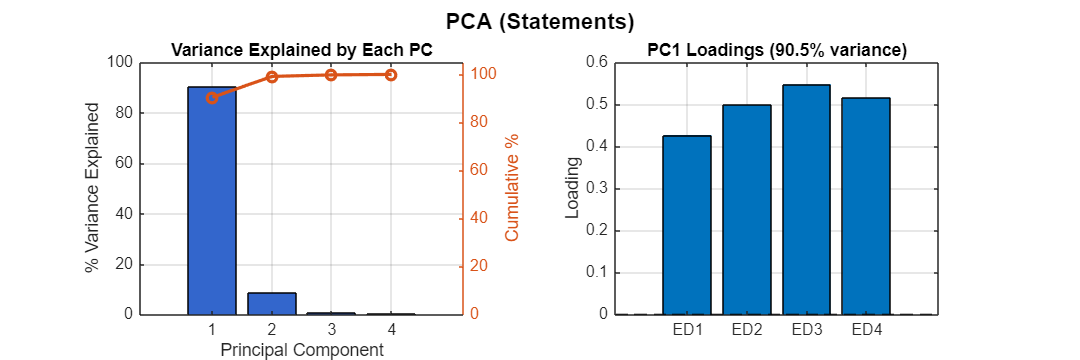

raw_dataset_stmt = readtable("data\USMPD.xlsx", "Sheet", "Statements");
raw_dataset_stmt.Date = datetime(raw_dataset_stmt.Date);
% We start in 1999
mask = raw_dataset_stmt.Date  >= datetime(1999,1,1) & raw_dataset_stmt.Date  <= datetime(2025,12,31);
reduced_dataset_stmt = raw_dataset_stmt(mask,{'Date','MP1', 'MP2', 'FF1', 'FF2', 'ED1', 'ED2', 'ED3', 'ED4'});
reduced_dataset_stmt.Properties.VariableNames = {'Date', 'MP1_Stmt', 'MP2_Stmt', 'FF1_Stmt', 'FF2_Stmt', 'ED1_Stmt',...
    'ED2_Stmt', 'ED3_Stmt','ED4_Stmt'};

% First we extend the daily return computations
dataset_yields_extended = raw_dataset_gsw(:, {'Date','SVENY01', 'SVENY02','SVENY05','SVENY10'});
varsRates = ["SVENY01", "SVENY02","SVENY05","SVENY10"];
for v = varsRates
    dataset_yields_extended.(v) = str2double(string(dataset_yields_extended.(v)));
end

yields_diff_extended = diff(dataset_yields_extended{:, 2:end}); 

yield_base_extended = table(dataset_yields_extended.Date(2:end), yields_diff_extended(:,1), yields_diff_extended(:,2),...
    yields_diff_extended(:,3), yields_diff_extended(:,4), ...
    'VariableNames',{'Date', 'Diff1y', 'Diff2y', 'Diff5y', 'Diff10y'});

% Now we compute the raw MPS
X_stmt = reduced_dataset_stmt{:, {'ED1_Stmt','ED2_Stmt','ED3_Stmt','ED4_Stmt'}};
[loadings_stmt, score_stmt, latent_stmt, explained_stmt, mu_stmt] = pca_analysis(X_stmt, ...
    'Labels', {'ED1','ED2','ED3','ED4'}, ...
    'Title', 'PCA (Statements)', ...
    'NumPCs', 1);

% We scale the first PC
reduced_dataset_stmt = outerjoin(reduced_dataset_stmt, yield_base_extended, 'Keys','Date', 'MergeKeys',true, 'Type', 'left');
reduced_dataset_stmt = fillmissing(reduced_dataset_stmt, 'previous');
[scaled_loadings_stmt, scaled_PC1_stmt] = scaling(loadings_stmt(:,1), score_stmt(:,1), reduced_dataset_stmt.ED4_Stmt);
reduced_dataset_stmt.MPS_stmt =  scaled_PC1_stmt;

    To address the potential endogeneity of monetary policy surprises, Bauer & Swanson argue that, in order to be *truly* unpredictable, the MPS should be orthogonalized with respect to: 

- Nonfarm payrolls (NFP) surprises 

- Employment growth (YoY)

- 3-months log change in the S&P 500

- Yield curve slope change 

- 3-months log change in the Bloomberg Commodity Spot Price index

- Treasury skewness

Please note that we will not add NFP surprises, as we don't have access to the Money Market Services surveys. However, the 5 other elements are accessible via the FRED website, Yahoo Finance of the FED website. For more details, please see the paper from Bauer and Swanson, *A Reassessment of Monetary Policy Surprises and High-Frequency Identification.* 

% ================================================
% We import data
% ================================================

% 1. Employment growth (YoY%, data are monthly)
nfp = readtable("data\Base Macro News", 'Sheet', "NFP");
nfp.Date = datetime(nfp.Date);
nfp.Growth_YoY = 100 * (log(nfp.PAYEMS) - log(lagmatrix(nfp.PAYEMS, 12)));

% 2. S&P 500 (Log prices, data are daily)
sp500 = raw_dataset_sp500;
sp500.Date = datetime(sp500.Date);
sp500.LogPrice = log(sp500.GSPC_Close);

% 3. Yield Curve Slope (data are daily)
yc_slope = readtable("data\Base Macro News", 'Sheet', "Slope");
yc_slope.Date = datetime(yc_slope.Date);

% 4. Commodities (log BCOM, data are daily)
bcom = readtable("data\Base Macro News", 'Sheet', "BCOM");

bcom.Date = datetime(bcom.Dates);
bcom.LogPrice = log(bcom.BCOMIndex);

% 5. Treasury Skewness (data are daily)
skew = readtable("data\Base Macro News", 'Sheet', "Implied skew");
skew.Date = datetime(skew.Date);

% ================================================
% We transform the data
% ================================================

num_meetings = height(reduced_dataset_stmt);

% Storage
X = array2table(nan(num_meetings, 5), ...
    'VariableNames', {'NFP_YoY', 'SP500_3m', 'Slope_3m', 'BCOM_3m', 'Skew_Avg'});
X.Date = reduced_dataset_stmt.Date;

for i = 1:num_meetings
    fomc_date = reduced_dataset_stmt.Date(i);
    
    % 1. Employment growth: Last release before the FOMC meeting
    idx_nfp = find(nfp.Date < fomc_date, 1, 'last');
    if ~isempty(idx_nfp)
        X.NFP_YoY(i) = nfp.Growth_YoY(idx_nfp);
    end
    
    % 2. S&P 500: Log change over 65 trading days
    idx_sp_end = find(sp500.Date < fomc_date, 1, 'last');
    if ~isempty(idx_sp_end) && (idx_sp_end > 65)
        idx_sp_start = idx_sp_end - 65;
        X.SP500_3m(i) = sp500.LogPrice(idx_sp_end) - sp500.LogPrice(idx_sp_start);
    end
    
    % 3. YC SLOPE: Change over 65 days
    idx_sl_end = find(yc_slope.Date < fomc_date, 1, 'last');
    if ~isempty(idx_sl_end) && (idx_sl_end > 65)
        idx_sl_start = idx_sl_end - 65;
        X.Slope_3m(i) = yc_slope.BETA1(idx_sl_end) - yc_slope.BETA1(idx_sl_start);
    end
    
    % 4. BCOM: Log change over 65 days
    idx_bc_end = find(bcom.Date < fomc_date, 1, 'last');
    if ~isempty(idx_bc_end) && (idx_bc_end > 65)
        idx_bc_start = idx_bc_end - 65;
        X.BCOM_3m(i) = bcom.LogPrice(idx_bc_end) - bcom.LogPrice(idx_bc_start);
    end
    
    % 5. IMPLIED SKEW: Average over the preceding month
    date_start_skew = fomc_date - 30;
    date_end_skew = fomc_date - 1;
    
    mask_skew = (skew.Date >= date_start_skew) & (skew.Date <= date_end_skew);
    vals_skew = skew.isk(mask_skew);
    if ~isempty(vals_skew)
        X.Skew_Avg(i) = mean(vals_skew, 'omitnan');
    end
end

dataset_reg = [reduced_dataset_stmt(:, {'Date','MPS_stmt'}), X(:, {'NFP_YoY', 'SP500_3m', 'Slope_3m', 'BCOM_3m', 'Skew_Avg'})];
dataset_reg = rmmissing(dataset_reg);

% ================================================
% We perform the regression
% ================================================

mdl = fitlm(dataset_reg, 'MPS_stmt ~ NFP_YoY + SP500_3m + Slope_3m + BCOM_3m + Skew_Avg');

% The orthogonalized MPS are the residuals
dataset_reg.MPS_ORTH = mdl.Residuals.Raw;

We want to compare our reconstructed MPS to those of Bauer & Swanson, from 1999 to 2023. For that, we compute the correlation and RMSE and plot both types of MPS with the B&S ones. 

% Comparison
comparative_mps = table(dataset_mps.Date, dataset_mps.MPS, dataset_mps.MPS_ORTH,...
    'VariableNames', {'Date', 'MPS_BS', 'MPS_ORTH_BS'});
comparative_mps = outerjoin(comparative_mps, ...
    table(reduced_dataset_stmt.Date, reduced_dataset_stmt.MPS_stmt, ...
    'VariableNames', {'Date','MPS_reconstructed'}), ...
    'Keys','Date', 'MergeKeys',true, ...
    'Type', 'left');
comparative_mps = outerjoin(comparative_mps, ...
    table(dataset_reg.Date, dataset_reg.MPS_ORTH, ...
    'VariableNames', {'Date','MPS_ORTH_reconstructed'}), ...
    'Keys','Date', 'MergeKeys',true, ...
    'Type', 'left');

comp_nonorth = comparative_mps(:, {'Date','MPS_BS','MPS_reconstructed'});
comp_orth    = comparative_mps(:, {'Date','MPS_ORTH_BS','MPS_ORTH_reconstructed'});

comp_nonorth = rmmissing(comp_nonorth, 'DataVariables', {'MPS_BS','MPS_reconstructed'});
comp_orth    = rmmissing(comp_orth,    'DataVariables', {'MPS_ORTH_BS','MPS_ORTH_reconstructed'});

% Metrics
corr_nonorth = corr(comp_nonorth.MPS_BS, comp_nonorth.MPS_reconstructed, 'rows','complete');
rmse_nonorth = sqrt(mean((comp_nonorth.MPS_BS - comp_nonorth.MPS_reconstructed).^2, 'omitnan'));
n_nonorth    = height(comp_nonorth);

corr_orth = corr(comp_orth.MPS_ORTH_BS, comp_orth.MPS_ORTH_reconstructed, 'rows','complete');
rmse_orth = sqrt(mean((comp_orth.MPS_ORTH_BS - comp_orth.MPS_ORTH_reconstructed).^2, 'omitnan'));
n_orth    = height(comp_orth);
ComparisonMetrics = table( ...
    ["MPS (non-orth)"; "MPS ORTH"], ...
    [corr_nonorth; corr_orth], ...
    [rmse_nonorth; rmse_orth], ...
    [n_nonorth; n_orth], ...
    'VariableNames', {'Series','Correlation','RMSE','N_Common'} ...
);
disp(ComparisonMetrics);

         Series         Correlation      RMSE       N_Common
    ________________    ___________    _________    ________

    "MPS (non-orth)"      0.99243      0.0066604      191   
    "MPS ORTH"            0.94847       0.016124      181   



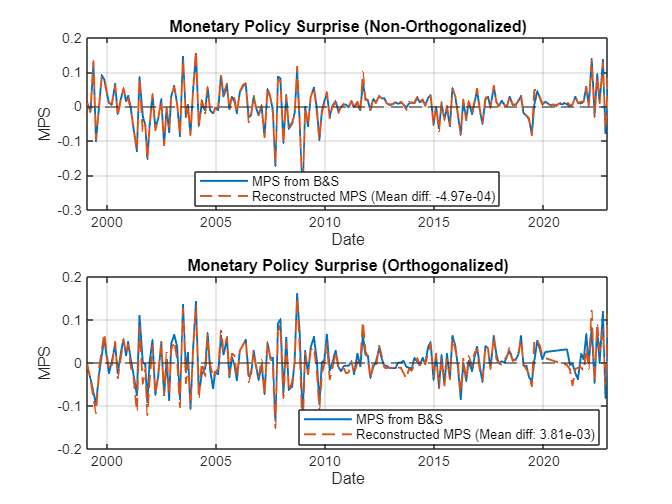


% Graph
mean_diff_nonorth = mean(comp_nonorth.MPS_BS - comp_nonorth.MPS_reconstructed, 'omitnan');
mean_diff_orth = mean(comp_orth.MPS_ORTH_BS - comp_orth.MPS_ORTH_reconstructed, 'omitnan');

f6 = figure;
subplot(2,1,1)
plot(comp_nonorth.Date, comp_nonorth.MPS_BS, 'LineWidth', 1.2); hold on;
plot(comp_nonorth.Date, comp_nonorth.MPS_reconstructed, '--', 'LineWidth', 1.2);
yline(0,'--'); grid on;
title('Monetary Policy Surprise (Non-Orthogonalized)');
xlabel('Date'); ylabel('MPS');
legend('MPS from B&S', ...
       sprintf('Reconstructed MPS (Mean diff: %.2e)', mean_diff_nonorth), ...
       'Location','best');

subplot(2,1,2)
plot(comp_orth.Date, comp_orth.MPS_ORTH_BS, 'LineWidth', 1.2); hold on;
plot(comp_orth.Date, comp_orth.MPS_ORTH_reconstructed, '--', 'LineWidth', 1.2);
yline(0,'--'); grid on;
title('Monetary Policy Surprise (Orthogonalized)');
xlabel('Date'); ylabel('MPS');
legend('MPS from B&S', ...
       sprintf('Reconstructed MPS (Mean diff: %.2e)', mean_diff_orth), ...
       'Location','best');
exportgraphics(f6, 'graphs/BS_MPS_vs_reconstructed.pdf', 'ContentType', 'vector');

Our reconstruction is really close to Bauer and Swanson, despite the lack of the NFP surprise for the orthogonalized one. 

### *3.2. Constructing Gurkaynak, Sack and Swanson (2005) target and path factors*

    Gürkaynak, Sack and Swanson (2005) computed the now broadly used Target and Path factors as the rotated two first principal components of adjusted changes in federal funds futures and 2 to 4-quarter ahead Eurodollar futures. The rotation procedure allows for economic interpretability, and is described in the Appendix of their paper but basically:

- factors are normalized to have unit variance

- factors remain orthogonal

- the second factor does not influence the current policy surprise (MP1)

- the first factor moves MP1 one-for-one

- the two factors have the same magnitude effect on ED4

Please note that the adjusted changes in federal funds futures are already computed and available in the US-MPD database (MP1 and MP2). Also, if the methodology is the one of Gürkaynak et al., the factors used as benchmark are those computed by Acosta et al. (2024), where they replace Eurodollars by SOFR futures for recent data due to regulation changes and trade volumes. They show however that it doesn't change any significant analysis.


PCA (Statements) - GSS

Variance explained by first 2 PCs:
  PC1: 78.43%
  PC2: 18.29%
  Cumulative: 96.72%



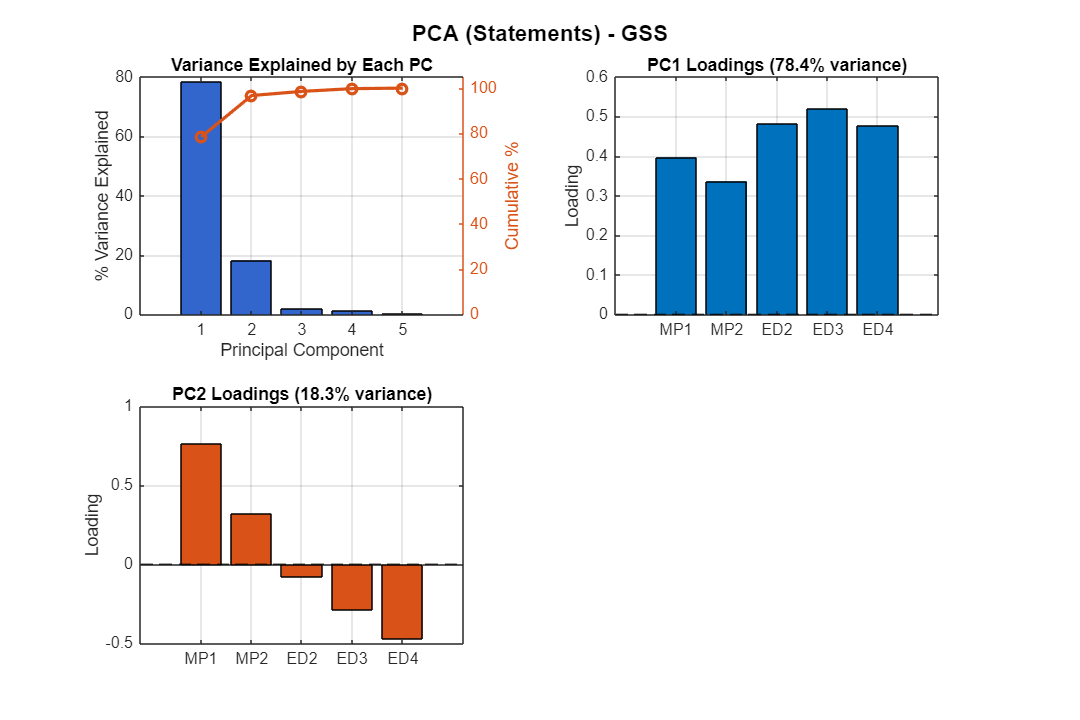

X_stmt_tp = reduced_dataset_stmt{:, {'MP1_Stmt','MP2_Stmt', 'ED2_Stmt', 'ED3_Stmt','ED4_Stmt'}};
[loadings_stmt_tp, score_stmt_tp, latent_stmt_tp, explained_stmt_tp, mu_stmt_tp] = pca_analysis(X_stmt_tp, ...
    'Labels', {'MP1','MP2','ED2','ED3', 'ED4'}, ...
    'Title', 'PCA (Statements) - GSS', ...
    'NumPCs', 2);


% We follow the appendix in GSS 2005 to rotate the factors so that they are
% economically interpretable. MP1 and MP2 are already computed in the USMPD database.
F1 = zscore(score_stmt_tp(:,1));
F2 = zscore(score_stmt_tp(:,2));
mp1 = reduced_dataset_stmt.MP1_Stmt;
ed4 = reduced_dataset_stmt.ED4_Stmt;
[target, path, rotated_loadings] = GSS_replication(X_stmt_tp);

Correlation between Target and Path: -0.0000 (Should be very close to 0)


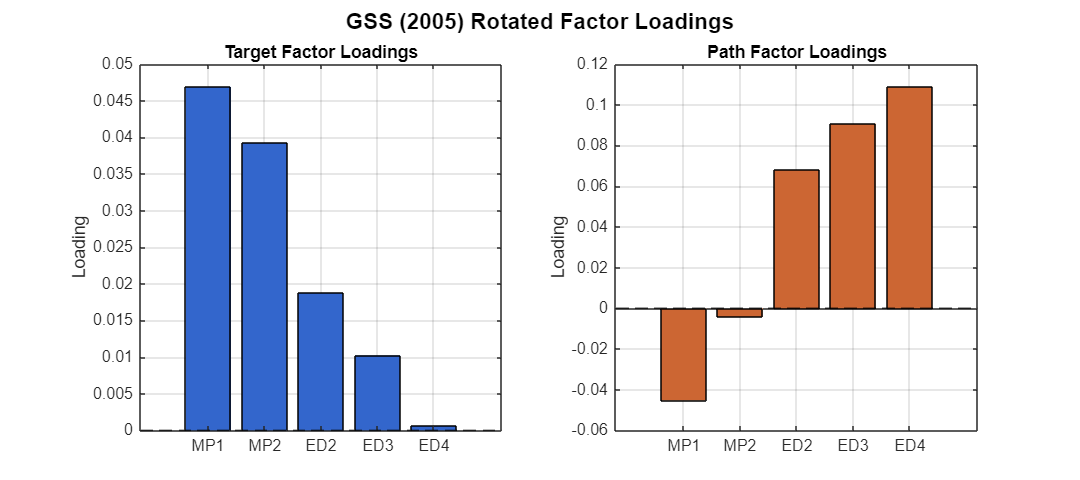

surprises_gss = table(reduced_dataset_stmt.Date, target, path, ...
    'VariableNames', {'Dates', 'Target', 'Path'});

% Plot rotated loadings
labels = {'MP1','MP2','ED2','ED3', 'ED4'};
figure('Position', [100, 100, 900, 400]);
colors = [0.2 0.4 0.8; 0.8 0.4 0.2];
factor_names = {'Target', 'Path'};

for i = 1:2
    subplot(1, 2, i);
    
    b = bar(rotated_loadings(:, i), 'FaceColor', colors(i,:));
    
    set(gca, 'XTick', 1:length(labels), 'XTickLabel', labels);
    ylabel('Loading');
    title(sprintf('%s Factor Loadings', factor_names{i}));
    grid on;
    
    hold on;
    yline(0, 'k--', 'LineWidth', 1);
    hold off;
    
    if length(labels) > 6
        xtickangle(45);
    end
end
sgtitle('GSS (2005) Rotated Factor Loadings', 'FontSize', 14, 'FontWeight', 'bold');


% We compare the two factors to those of Acosta et al. (2024)
reduced_dataset_stmt.target_stmt =  target;
reduced_dataset_stmt.path_stmt =  path;
comparative_mps.target_abj = mps_base.Target;
comparative_mps.path_abj = mps_base.Path;
comparative_mps = outerjoin(comparative_mps, ...
    table(reduced_dataset_stmt.Date, reduced_dataset_stmt.target_stmt, reduced_dataset_stmt.path_stmt, ...
    'VariableNames', {'Date','target_stmt',  'path_stmt'}), ...
    'Keys','Date', 'MergeKeys',true, ...
    'Type', 'left');

comp_target = comparative_mps(:, {'Date','target_abj','target_stmt'});
comp_path    = comparative_mps(:, {'Date','path_abj','path_stmt'});

comp_target = rmmissing(comp_target, 'DataVariables', {'target_abj','target_stmt'});
comp_path    = rmmissing(comp_path,    'DataVariables', {'path_abj','path_stmt'});

% Metrics
corr_target = corr(comp_target.target_abj, comp_target.target_stmt, 'rows','complete');
rmse_target = sqrt(mean((comp_target.target_abj - comp_target.target_stmt).^2, 'omitnan'));
n_target   = height(comp_target);

corr_path = corr(comp_path.path_abj, comp_path.path_stmt, 'rows','complete');
rmse_path = sqrt(mean((comp_path.path_abj - comp_path.path_stmt).^2, 'omitnan'));
n_path    = height(comp_path);
ComparisonMetrics = table( ...
    ["TARGET"; "PATH"], ...
    [corr_target; corr_path], ...
    [rmse_target; rmse_path], ...
    [n_target; n_path], ...
    'VariableNames', {'Series','Correlation','RMSE','N_Common'} ...
);
disp(ComparisonMetrics);

     Series     Correlation      RMSE       N_Common
    ________    ___________    _________    ________

    "TARGET"      0.98573      0.0098593      191   
    "PATH"        0.98017       0.065577      191   



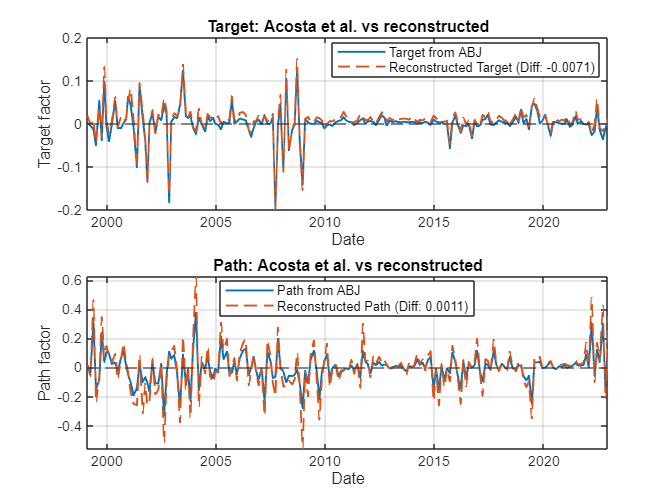



f7 = figure;
subplot(2,1,1);
plot(comparative_mps.Date, comparative_mps.target_abj, 'LineWidth', 1.2); hold on;
plot(comparative_mps.Date, comparative_mps.target_stmt, '--', 'LineWidth', 1.2);
yline(0,'--');
grid on;
xlabel('Date'); ylabel('Target factor');
title('Target: Acosta et al. vs reconstructed');
mean_diff_target = mean(comparative_mps.target_abj - comparative_mps.target_stmt);
legend_str_target = sprintf('Reconstructed Target (Diff: %.4f)', mean_diff_target);
legend('Target from ABJ', legend_str_target, 'Location', 'best');

subplot(2,1,2);
plot(comparative_mps.Date, comparative_mps.path_abj, 'LineWidth', 1.2); hold on;
plot(comparative_mps.Date, comparative_mps.path_stmt, '--', 'LineWidth', 1.2);
yline(0,'--');
grid on;
xlabel('Date'); ylabel('Path factor');
title('Path: Acosta et al. vs reconstructed');
mean_diff_path = mean(comparative_mps.path_abj - comparative_mps.path_stmt);
legend_str_path = sprintf('Reconstructed Path (Diff: %.4f)', mean_diff_path);
legend('Path from ABJ', legend_str_path, 'Location', 'best');

exportgraphics(f7, 'graphs/Target_Path_ABJ_vs_reconstructed.pdf', 'ContentType', 'vector');

Our reconstruction is really close to Acosta et al. 

### *3.3. Extending to recent data*

Since we showed that our procedure was robust, we now extend it to more recent data, as well as to other types of monetary events. We first do the same procedure for press conference and monetary events surprises individually, then for all the events combined in one single dataset.

% ================================================
% We load all the needed data
% ================================================

% Yields 
dataset_yields_extended = raw_dataset_gsw(:, {'Date','SVENY01', 'SVENY02','SVENY05','SVENY10'});
varsRates = ["SVENY01", "SVENY02","SVENY05","SVENY10"];
for v = varsRates
    dataset_yields_extended.(v) = str2double(string(dataset_yields_extended.(v)));
end
yields_diff_extended = diff(dataset_yields_extended{:, 2:end}); 
yield_base_extended = table(dataset_yields_extended.Date(2:end), ...
    yields_diff_extended(:,1), yields_diff_extended(:,2),...
    yields_diff_extended(:,3), yields_diff_extended(:,4), ...
    'VariableNames',{'Date', 'Diff1y', 'Diff2y', 'Diff5y', 'Diff10y'});

% TIPS Data 
mask_tips = raw_tips_dataset.Date >= datetime(1999,1,1) & raw_tips_dataset.Date <= datetime(2025,12,31);
tips_dataset = raw_tips_dataset(mask_tips,:);
tips_changes = diff(tips_dataset{:,2:end}, 1);
tips_changes_dataset = array2table(tips_dataset.Date(2:end), 'VariableNames',{'Dates'});
tips_changes_dataset = [tips_changes_dataset array2table(tips_changes, 'VariableNames', tips_dataset.Properties.VariableNames(2:end))];

% ================================================
% We load macro data for orthogonalization
% ================================================
macro_data.nfp = readtable("data\Base Macro News.xlsx", 'Sheet', "NFP");
macro_data.sp500 = raw_dataset_sp500;  % Already loaded
macro_data.yc_slope = readtable("data\Base Macro News.xlsx", 'Sheet', "Slope");
macro_data.bcom = readtable("data\Base Macro News.xlsx", 'Sheet', "BCOM");


PCA (Statements)

Variance explained by first 1 PCs:
  PC1: 90.46%
  Cumulative: 90.46%




=== Bauer & Swanson (2023) Orthogonalization ===
MPS variable used: MPS
Original sample size: 231
Complete cases: 220 (95.2%)
Missing observations: 11
R² of MPS on macro variables: 0.1400
Adj. R²: 0.1199

Regression coefficients:
                    Estimate        SE         tStat      pValue  
                   __________    _________    _______    _________

    (Intercept)    -0.0054981    0.0041638    -1.3204       0.1881
    NFP_YoY          0.003251    0.0015465     2.1021     0.036712
    SP500_3m          0.13725     0.051739     2.6527    0.0085845
    Slope_3m       -0.0021502    0.0017227    -1.2481      0.21336
    BCOM_3m          0.068639     0.046548     1.4746       0.1418
    Skew_Avg         0.028005      0.01243     2.2531     0.0

Correlation between Target and Path: -0.0000 (Should be very close to 0)



Table 1 (Statements) - BS2023 Orthogonalized: Standard MP effects

======= Baseline (B&S Orth) ======= 

                    SP500         2y          5y         10y   
                   ________    ________    ________    ________

    MPS_ORTH        -4.8159      0.5455     0.40401     0.19977
    se_MPS_ORTH        2.25    0.097268       0.102    0.084762
    R2             0.038674     0.16815    0.075163    0.023268
    Obs                 231         231         231         231


P-values:
                      SP500         2y           5y          10y


Table 2 (Statements) - BS2023 Orthogonalized: MP effects with same/opposite sign

======= Spec1 ======= 

                                 SP500          2y            5y           10y    
                               _________    __________    __________    __________

    MPS_ORTH                     -4.8437       0.49257       0.33349       0.13108
    se_MPS_ORTH                   2.7854       0.10539       0.10541      0.090255
    MPS_ORTH x indic_opp        0.021263       0.14669       0.19583       0.20113
    se_MPS_ORTH x indic_opp       4.7757       0.21805       0.23244        0.1976
    indic_opp       

Table 3 (Statements) - BS2023 Orthogonalized: Descriptive Statistics


                       N      %       Mean     Mean Abs     SD  
                      ___    ____    ______    ________    _____

    Same Signs        124    53.7     0.005     0.042      0.062
    Opposite Signs    107    46.3    -0.003     0.035      0.047




Table 4 (Statements) - BS2023 Orthogonalized: MP effects with HOM signals

======= Spec1 ======= 

                           SP500         2y           5y           10y   
                         _________    _________    _________    _________

    MPS_ORTH               -4.8437      0.49257      0.33349      0.13108
    se_MPS_ORTH             2.7854      0.10539      0.10541     0.090255
    MPS_ORTH x Att       -0.054754     -0.22984     -0.59236     -0.46369
    se_MPS_ORTH x Att        15.48      0.50175      0.65365      0.55433
    MPS_ORTH x HOM        0.044558      0.21758      0.34242      0.3248

Marginal Effect: Attenuation (Statements) - BS2023 Orthogonalized


                    SP500      2y        5y       10y  
                    ______    _____    ______    ______

    Marginal_Att    -4.898    0.263    -0.259    -0.333
    se_att          15.227    0.491     0.645     0.547



Marginal Effect: HOM (Statements) - BS2023 Orthogonalized


                    SP500      2y       5y       10y 
                    ______    _____    _____    _____

    Marginal_Hom    -4.799     0.71    0.676    0.456
    se_hom           3.647    0.202    0.205    0.177



R2 Decomposition (Statements) - BS2023 Orthogonalized


                SP500        2y          5y         10y   
               ________    _______    ________    ________

    R2 Same     0.05737     0.1997    0.092814    0.022296
    R2 Att      0.01484    0.02254    0.016615    0.035425
    R2 HOM     0.026072    0.18117     0.11384     0.05708
    Obs             231        231         231         231




Table 9 (Statements) - BS2023 Orthogonalized: Real Rates & Inflation Comp.

======= Spec1 ======= 

                          NIR-2y       NIR-5y      NIR-10y      RIR-2y       RIR-5y       RIR-10y       IC-2y        IC-5y       IC-10y  
                         _________    _________    ________    _________    _________    _________    _________    _________    _________

    MPS_ORTH               0.47714      0.31734     0.11759     0.087408      0.36064      0.21429      0.37778    -0.062199     -0.11917

Marginal Effect: HOM - TIPS (Statements) - BS2023 Orthogonalized


                    NIR-2y    NIR-5y    NIR-10y    RIR-2y    RIR-5y    RIR-10y    IC-2y    IC-5y     IC-10y
                    ______    ______    _______    ______    ______    _______    _____    ______    ______

    Marginal_Hom    0.712     0.679      0.459      0.83     0.838       0.64     0.016    -0.022    -0.092
    se_hom          0.202     0.204      0.177     0.328     0.254      0.208     0.261     0.118     0.082



R2 Decomposition - TIPS (Statements) - BS2023 Orthogonalized


                NIR-2y      NIR-5y      NIR-10y       RIR-2y       RIR-5y     RIR-10y       IC-2y         IC-5y        IC-10y 
                _______    ________    _________    __________    ________    ________    __________    __________    ________

    R2 Other    0.15339    0.050175    0.0060788    0.00076264    0.072284    0.045751      0.013245      0.015265    0.063083
    R2 HOM      0.18301     0.11696     0.058511      0.046509      0.1188    0.091892    2.0662e-05    0.00044835     0.01536
    Obs             229         229          229           229         229         229           229           229         229




PCA (Press Conferences)

Variance explained by first 1 PCs:
  PC1: 95.39%
  Cumulative: 95.39%



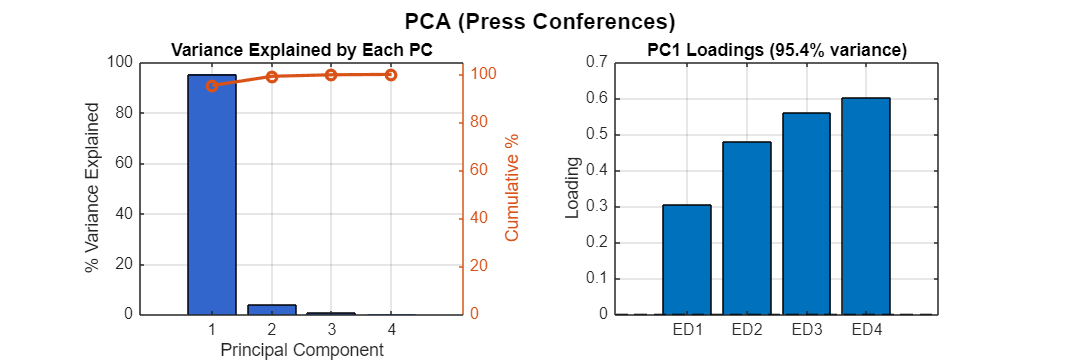


=== Bauer & Swanson (2023) Orthogonalization ===
MPS variable used: MPS
Original sample size: 89
Complete cases: 84 (94.4%)
Missing observations: 5
R² of MPS on macro variables: 0.0804
Adj. R²: 0.0214

Regression coefficients:
                    Estimate        SE         tStat      pValue 
                   __________    _________    ________    _______

    (Intercept)    -0.0069051    0.0073998    -0.93315    0.35362
    NFP_YoY        -0.0012925    0.0019001    -0.68025    0.49836
    SP500_3m          0.17009      0.10535      1.6145    0.11045
    Slope_3m        0.0026352    0.0019833      1.3287    0.18783
    BCOM_3m          -0.11455     0.085454     -1.3405    0.18399
    Skew_Avg         0.011805     0.018185     0.64915    0.51815



Correlation between Target and Path: -0.0000 (Should be very close to 0)



Table 1 (Press Conferences) - BS2023 Orthogonalized: Standard MP effects

======= Baseline (B&S Orth) ======= 

                    SP500       2y         5y         10y   
                   _______    _______    _______    ________

    MPS_ORTH        -8.573    0.68164    0.64736      0.4091
    se_MPS_ORTH     2.0527    0.10269    0.11959    0.078262
    R2             0.15123    0.29517    0.24458     0.17788
    Obs                 89         89         89          89


P-values:
                       SP500           2y            5y           10y    



Table 2 (Press Conferences) - BS2023 Orthogonalized: MP effects with same/opposite sign

======= Spec1 ======= 

                                 SP500         2y          5y         10y   
                               _________    ________    ________    ________

    MPS_ORTH                     -8.5318     0.63902      0.5451     0.36174
    se_MPS_ORTH                   2.4736      0.1075     0.13835    0.085794
    MPS_ORTH x indic_opp       -0.081149     0.16667     0.38818     0.18855
    se_MPS_ORTH x indic_opp       4.3118     0.27662     0.25706     0.18111
    indic_opp                   0.039299

Table 3 (Press Conferences) - BS2023 Orthogonalized: Descriptive Statistics


                      N      %      Mean     Mean Abs     SD  
                      __    ____    _____    ________    _____

    Same Signs        40    44.9    0.006     0.046       0.07
    Opposite Signs    49    55.1    0.001     0.027      0.039




Table 4 (Press Conferences) - BS2023 Orthogonalized: MP effects with HOM signals

======= Spec1 ======= 

                           SP500          2y           5y         10y   
                         __________    _________    ________    ________

    MPS_ORTH                -8.5318      0.63902      0.5451     0.36174
    se_MPS_ORTH              2.4736       0.1075     0.13835    0.085794
    MPS_ORTH x Att           19.397      0.76225      0.9159     0.84077
    se_MPS_ORTH x Att        23.935        1.451      1.5835      1.2307
    MPS_ORTH x HOM         -0.49342      0.15512      0.3776     0.1744

Marginal Effect: Attenuation (Press Conferences) - BS2023 Orthogonalized


                    SP500      2y       5y       10y 
                    ______    _____    _____    _____

    Marginal_Att    10.865    1.401    1.461    1.203
    se_att          23.807    1.447    1.577    1.228



Marginal Effect: HOM (Press Conferences) - BS2023 Orthogonalized


                    SP500      2y       5y       10y 
                    ______    _____    _____    _____

    Marginal_Hom    -9.025    0.794    0.923    0.536
    se_hom           3.587    0.259     0.22    0.162



R2 Decomposition (Press Conferences) - BS2023 Orthogonalized


                SP500        2y          5y         10y   
               ________    _______    ________    ________

    R2 Same     0.19906    0.38152     0.24144      0.1756
    R2 Att     0.012309    0.10615    0.091951    0.080395
    R2 HOM      0.13354    0.24818     0.33974     0.26782
    Obs              89         89          89          89




Table 9 (Press Conferences) - BS2023 Orthogonalized: Real Rates & Inflation Comp.

======= Spec1 ======= 

                           NIR-2y        NIR-5y       NIR-10y      RIR-2y       RIR-5y       RIR-10y        IC-2y         IC-5y         IC-10y  
                         ___________    _________    _________    _________    _________    __________    __________    __________    __________

    MPS_ORTH                 0.69537      0.59059      0.39262      0.91409      0.94336       0.56844     -0.076167

Marginal Effect: HOM - TIPS (Press Conferences) - BS2023 Orthogonalized


                    NIR-2y    NIR-5y    NIR-10y    RIR-2y    RIR-5y    RIR-10y    IC-2y     IC-5y    IC-10y
                    ______    ______    _______    ______    ______    _______    ______    _____    ______

    Marginal_Hom    0.794     0.923      0.536     1.297     1.246      0.864     -0.358    -0.15    -0.18 
    se_hom          0.259      0.22      0.162     0.288     0.243       0.17       0.12    0.123    0.092 



R2 Decomposition - TIPS (Press Conferences) - BS2023 Orthogonalized


                NIR-2y     NIR-5y     NIR-10y    RIR-2y     RIR-5y     RIR-10y      IC-2y       IC-5y       IC-10y 
                _______    _______    _______    _______    _______    _______    _________    ________    ________

    R2 Other    0.41019    0.25065    0.17622    0.30918    0.33902    0.22716    0.0078704      0.1715    0.041917
    R2 HOM      0.24818    0.33974    0.26782    0.33383     0.3864    0.36423     0.071638    0.025688     0.05233
    Obs              88         88         88         88         88         88           88          88          88




PCA (Monetary Events)

Variance explained by first 1 PCs:
  PC1: 90.64%
  Cumulative: 90.64%



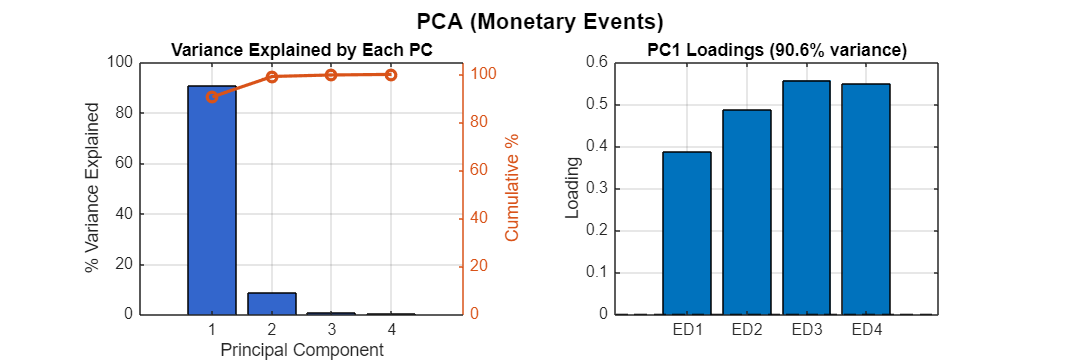


=== Bauer & Swanson (2023) Orthogonalization ===
MPS variable used: MPS
Original sample size: 231
Complete cases: 220 (95.2%)
Missing observations: 11
R² of MPS on macro variables: 0.1217
Adj. R²: 0.1011

Regression coefficients:
                    Estimate         SE         tStat       pValue  
                   ___________    _________    ________    _________

    (Intercept)      -0.006463    0.0047831     -1.3512      0.17806
    NFP_YoY          0.0020618    0.0017766      1.1605      0.24712
    SP500_3m            0.1756     0.059434      2.9545    0.0034821
    Slope_3m       -0.00072315     0.001979    -0.36542      0.71516
    BCOM_3m           0.037645     0.053471     0.70402      0.48219
    Skew_Avg          0.034296     0.014279    

Correlation between Target and Path: -0.0000 (Should be very close to 0)



Table 1 (Monetary Events) - BS2023 Orthogonalized: Standard MP effects

======= Baseline (B&S Orth) ======= 

                    SP500         2y          5y         10y   
                   ________    ________    ________    ________

    MPS_ORTH        -6.1231     0.62816     0.50378     0.26924
    se_MPS_ORTH      1.6992    0.084138    0.088849    0.071404
    R2             0.083665     0.29839      0.1564    0.056562
    Obs                 231         231         231         231


P-values:
                       SP500           2y            5y           1


Table 2 (Monetary Events) - BS2023 Orthogonalized: MP effects with same/opposite sign

======= Spec1 ======= 

                                 SP500          2y           5y          10y   
                               _________    __________    ________    _________

    MPS_ORTH                     -6.2347       0.54847     0.39084      0.16836
    se_MPS_ORTH                   2.2882      0.089007    0.091063      0.08146
    MPS_ORTH x indic_opp       -0.062058       0.17146     0.23572      0.21744
    se_MPS_ORTH x indic_opp         3.33       0.16792     0.17211      0.14242
    indic_opp              

Table 3 (Monetary Events) - BS2023 Orthogonalized: Descriptive Statistics


                       N      %       Mean     Mean Abs     SD  
                      ___    ____    ______    ________    _____

    Same Signs        121    52.4     0.008     0.046      0.067
    Opposite Signs    110    47.6    -0.004     0.046      0.061




Table 4 (Monetary Events) - BS2023 Orthogonalized: MP effects with HOM signals

======= Spec1 ======= 

                          SP500         2y           5y           10y   
                         ________    _________    _________    _________

    MPS_ORTH              -6.2347      0.54847      0.39084      0.16836
    se_MPS_ORTH            2.2882     0.089007     0.091063      0.08146
    MPS_ORTH x Att         4.0521     -0.10476     -0.32745     -0.27757
    se_MPS_ORTH x Att      14.346      0.49889      0.59136      0.48177
    MPS_ORTH x HOM       -0.56895       0.1961       0.2878      0.26358


Marginal Effect: Attenuation (Monetary Events) - BS2023 Orthogonalized


                    SP500      2y       5y       10y  
                    ______    _____    _____    ______

    Marginal_Att    -2.183    0.444    0.063    -0.109
    se_att          14.162    0.491    0.584     0.475



Marginal Effect: HOM (Monetary Events) - BS2023 Orthogonalized


                    SP500      2y       5y       10y 
                    ______    _____    _____    _____

    Marginal_Hom    -6.804    0.745    0.679    0.432
    se_hom            2.17    0.146    0.144    0.116



R2 Decomposition (Monetary Events) - BS2023 Orthogonalized


                 SP500         2y          5y           10y   
               _________    ________    _________    _________

    R2 Same      0.11156     0.32396      0.16706     0.040582
    R2 Att     0.0031534    0.076269    0.0012333    0.0051035
    R2 HOM      0.095011     0.32034      0.19339     0.094087
    Obs              231         231          231          231




Table 9 (Monetary Events) - BS2023 Orthogonalized: Real Rates & Inflation Comp.

======= Spec1 ======= 

                          NIR-2y       NIR-5y       NIR-10y      RIR-2y       RIR-5y       RIR-10y        IC-2y        IC-5y       IC-10y  
                         _________    _________    _________    _________    _________    __________    _________    _________    _________

    MPS_ORTH               0.53939      0.38224      0.16206      0.27216      0.51388        0.3016      0.29403     -0.11551  

Marginal Effect: HOM - TIPS (Monetary Events) - BS2023 Orthogonalized


                    NIR-2y    NIR-5y    NIR-10y    RIR-2y    RIR-5y    RIR-10y    IC-2y    IC-5y     IC-10y
                    ______    ______    _______    ______    ______    _______    _____    ______    ______

    Marginal_Hom    0.745      0.68      0.433     0.823     0.868       0.63     0.011    -0.083    -0.118
    se_hom          0.146     0.144      0.116     0.213     0.172      0.136     0.168     0.079      0.06



R2 Decomposition - TIPS (Monetary Events) - BS2023 Orthogonalized


                NIR-2y     NIR-5y     NIR-10y      RIR-2y      RIR-5y     RIR-10y      IC-2y        IC-5y       IC-10y 
                _______    _______    ________    _________    _______    _______    __________    ________    ________

    R2 Other    0.27637    0.12044     0.02433    0.0074034    0.19936    0.10914      0.010076    0.032183    0.071819
    R2 HOM      0.32255    0.19752    0.095904     0.081559    0.21325    0.15624    1.7194e-05    0.011231    0.042213
    Obs             229        229         229          229        229        229           229         229         229



macro_data.skew = readtable("data\Base Macro News.xlsx", 'Sheet', "Implied skew");

% ================================================
% Store loadings
% ================================================
loadings_storage = struct();

% ================================================
% List of sheets to process
% ================================================
sheet_names = {'Statements', 'Press Conferences', 'Monetary Events'};

for i = 1:length(sheet_names)
    current_sheet = sheet_names{i};

    % We load and filter data of the current sheet
    try
        raw_data = readtable("data\USMPD.xlsx", "Sheet", current_sheet);
    catch
        fprintf('Sheet "%s" not found or error loading. Skipping.\n', current_sheet);
        continue;
    end
    raw_data.Date = datetime(raw_data.Date);
    mask = raw_data.Date >= datetime(1999,1,1) & raw_data.Date <= datetime(2025,12,31);
    
    % Columns of interest
    reduced_data = raw_data(mask, {'Date','MP1', 'MP2', 'FF1', 'FF2', 'ED1', 'ED2', 'ED3', 'ED4'});
    
    % ================================================
    % Bauer & Swanson orthogonalized MPS
    % ================================================
    X_pca = reduced_data{:, {'ED1','ED2','ED3','ED4'}};
    X_pca = fillmissing(X_pca, 'previous'); 
    
    [loadings_mps, score, ~, ~, ~] = pca_analysis(X_pca, ...
        'Labels', {'ED1','ED2','ED3','ED4'}, ...
        'Title', ['PCA (' current_sheet ')'], ...
        'NumPCs', 1);
    
    % Store MPS loadings
    sheet_name_valid = matlab.lang.makeValidName(current_sheet);
    loadings_storage.(sheet_name_valid).MPS_loadings = loadings_mps(:,1);
    loadings_storage.(sheet_name_valid).MPS_labels = {'ED1','ED2','ED3','ED4'};
    
    % Scaling
    [~, scaled_PC1] = scaling(loadings_mps(:,1), score(:,1), reduced_data.ED4);
    reduced_data.MPS = scaled_PC1;
    
    % Orthogonalization
    reduced_data_orth = orthogonalize_mps_BS2023(reduced_data(:, {'Date', 'MPS'}), ...
        macro_data, ...
        'Orthogonalize', true, ...
        'Verbose', true);
    
    % Merge orthogonalized data back
    reduced_data = outerjoin(reduced_data, ...
        reduced_data_orth(:, {'Date', 'MPS_ORTH', 'NFP_YoY', 'SP500_3m', 'Slope_3m', 'BCOM_3m', 'Skew_Avg'}), ...
        'Keys', 'Date', 'MergeKeys', true);

    % ================================================
    % GSS (2005) Target and Path Factors
    % ================================================
    X_gss = reduced_data{:, {'MP1','MP2', 'ED2', 'ED3','ED4'}};
    X_gss = fillmissing(X_gss, 'previous');
    
    [target, path, loadings_gss] = GSS_replication(X_gss);
    
    reduced_data.Target = target;
    reduced_data.Path = path;
    
    % Store Target and Path loadings 
    loadings_storage.(sheet_name_valid).Target_loadings = loadings_gss(:,1);
    loadings_storage.(sheet_name_valid).Path_loadings = loadings_gss(:,2);
    loadings_storage.(sheet_name_valid).GSS_labels = {'MP1','MP2','ED2','ED3','ED4'};

    % ================================================
    % Merge all data together
    % ================================================
    recent_data = outerjoin(reduced_data, yield_base_extended, ...
        'Keys', 'Date', 'MergeKeys', true, 'Type', 'left');
    
    % Merge SP500
    recent_data = outerjoin(recent_data, sp500_dataset, ...
        'LeftKeys', 'Date', 'RightKeys', 'Dates', 'MergeKeys', true, 'Type', 'left');
    
    % Fill missing asset data 
    recent_data = fillmissing(recent_data, 'previous');
    recent_data.Properties.VariableNames{'Date_Dates'} = 'Date';
    
    % ================================================
    % Classification (HOM, Attenuation, Opp)
    % ================================================
    [indic_opp, indic_att, indic_hom] = classifier_mp_events(table(recent_data.Target, recent_data.Path, ...
        'VariableNames', {'Target', 'Path'}));
    
    % ================================================
    % Main regressions
    % ================================================
    
    % Filter to non-missing MPS_ORTH
    mask_orth = ~isnan(recent_data.MPS_ORTH);
    
    % Dependent Variables Y
    Y_assets = [recent_data.SP500_returns(mask_orth)*100, recent_data.Diff2y(mask_orth), ...
                recent_data.Diff5y(mask_orth), recent_data.Diff10y(mask_orth)];
    
    mps_reg = recent_data.MPS_ORTH(mask_orth);
    target_reg = recent_data.Target(mask_orth);
    path_reg = recent_data.Path(mask_orth);
    indic_opp_reg = indic_opp(mask_orth);
    indic_att_reg = indic_att(mask_orth);
    indic_hom_reg = indic_hom(mask_orth);
    
    % Table 1: Standard Effects 
    X_mps = mps_reg;
    X_tp = [target_reg, path_reg];
    
    display_regression_results(Y_assets, {X_mps, X_tp}, ...
        'YNames', {'SP500', '2y', '5y', '10y'}, ...
        'XNames', {{'MPS_ORTH'}, {'Target', 'Path'}}, ...
        'SpecNames', {'Baseline (B&S Orth)', 'Decomposition'}, ...
        'Title', sprintf('Table 1 (%s) - BS2023 Orthogonalized: Standard MP effects', current_sheet));

    % Table 2: Opposite Signs 
    X_opp = [mps_reg, mps_reg .* indic_opp_reg, indic_opp_reg];
    
    display_regression_results(Y_assets, {X_opp}, ...
        'YNames', {'SP500', '2y', '5y', '10y'}, ...
        'XNames', {{'MPS_ORTH', 'MPS_ORTH x indic_opp', 'indic_opp'}}, ...
        'Title', sprintf('Table 2 (%s) - BS2023 Orthogonalized: MP effects with same/opposite sign', current_sheet));

    % Table 3: Descriptive Stats 
    same_sign = mps_reg(indic_opp_reg==0);
    opp_sign = mps_reg(indic_opp_reg==1);
    
    rowNames = {'Same Signs','Opposite Signs'};
    colNames = {'N','%','Mean','Mean Abs','SD'};
    table3 = array2table(nan(2,5), 'RowNames', rowNames, 'VariableNames', colNames);
    
    table3{1,:} = [length(same_sign), round(100*length(same_sign)/length(mps_reg),1), ...
                   round(mean(same_sign),3), round(mean(abs(same_sign)),3), round(std(same_sign),3)];
    table3{2,:} = [length(opp_sign), round(100*length(opp_sign)/length(mps_reg),1), ...
                   round(mean(opp_sign),3), round(mean(abs(opp_sign)),3), round(std(opp_sign),3)];
               
    fprintf('Table 3 (%s) - BS2023 Orthogonalized: Descriptive Statistics\n', current_sheet);
    disp(table3);

    % Table 4: Higher-Order Moments (HOM)
    X_att_hom = [mps_reg, mps_reg .* indic_att_reg, mps_reg .* indic_hom_reg, indic_att_reg, indic_hom_reg];
    const = ones(length(mps_reg), 1);
    
    display_regression_results(Y_assets, {X_att_hom}, ...
        'YNames', {'SP500', '2y', '5y', '10y'}, ...
        'XNames', {{'MPS_ORTH', 'MPS_ORTH x Att', 'MPS_ORTH x HOM', 'Att', 'HOM'}}, ...
        'Title', sprintf('Table 4 (%s) - BS2023 Orthogonalized: MP effects with HOM signals', current_sheet));

    % Marginal Effects
    colNamesME = {'SP500', '2y', '5y', '10y'};
    
    % ME Attenuation
    table_me_att = array2table(nan(2,4), 'RowNames', {'Marginal_Att', 'se_att'}, 'VariableNames', colNamesME);
    table_me_att = me_results(Y_assets, [const X_att_hom], table_me_att, [2, 3]); 
    
    % ME HOM
    table_me_hom = array2table(nan(2,4), 'RowNames', {'Marginal_Hom', 'se_hom'}, 'VariableNames', colNamesME);
    table_me_hom = me_results(Y_assets, [const X_att_hom], table_me_hom, [2, 4]); 
    
    fprintf('Marginal Effect: Attenuation (%s) - BS2023 Orthogonalized\n', current_sheet);
    disp(table_me_att);
    fprintf('Marginal Effect: HOM (%s) - BS2023 Orthogonalized\n', current_sheet);
    disp(table_me_hom);

    % R2 Decomposition
    [~, ~, r2_same, ~] = robust_ols(Y_assets(~indic_opp_reg,:), mps_reg(~indic_opp_reg), true);
    [~, ~, r2_att, ~]  = robust_ols(Y_assets(indic_att_reg,:), mps_reg(indic_att_reg), true);
    [~, ~, r2_hom, ~]  = robust_ols(Y_assets(indic_hom_reg,:), mps_reg(indic_hom_reg), true);
    
    res_r2 = [r2_same; r2_att; r2_hom; repmat(length(mps_reg),1,4)];
    tab_r2 = array2table(res_r2, 'RowNames', {'R2 Same', 'R2 Att', 'R2 HOM', 'Obs'}, 'VariableNames', colNamesME);
    fprintf('R2 Decomposition (%s) - BS2023 Orthogonalized\n', current_sheet);
    disp(tab_r2);

    % Table 9: TIPS Analysis 
    recent_data_orth = recent_data(mask_orth, :);
    [~, idx_rec, idx_tips] = intersect(recent_data_orth.Date, tips_changes_dataset.Dates);
    
    if isempty(idx_rec)
        fprintf('Warning: No overlapping dates found for TIPS analysis in sheet %s.\n', current_sheet);
    else
        % Construct Y_tips
        Y_tips_vals = [recent_data_orth.Diff2y(idx_rec), recent_data_orth.Diff5y(idx_rec), recent_data_orth.Diff10y(idx_rec), ...
                       tips_changes_dataset.TIPSY02(idx_tips), tips_changes_dataset.TIPSY05(idx_tips), tips_changes_dataset.TIPSY10(idx_tips), ...
                       tips_changes_dataset.BKEVEN02(idx_tips), tips_changes_dataset.BKEVEN05(idx_tips), tips_changes_dataset.BKEVEN10(idx_tips)];
        Y_tips_vals = fillmissing(Y_tips_vals, 'previous');
        
        % Subset X
        X_tips = X_att_hom(idx_rec, :);
        const_tips = ones(length(idx_rec), 1);
        indic_hom_tips = indic_hom_reg(idx_rec);
        mps_tips = mps_reg(idx_rec);
        
        tipsNames = {'NIR-2y','NIR-5y','NIR-10y','RIR-2y','RIR-5y','RIR-10y','IC-2y','IC-5y','IC-10y'};
        
        display_regression_results(Y_tips_vals, {X_tips}, ...
            'YNames', tipsNames, ...
            'XNames', {{'MPS_ORTH', 'MPS_ORTH x Att', 'MPS_ORTH x HOM', 'Att', 'HOM'}}, ...
            'Title', sprintf('Table 9 (%s) - BS2023 Orthogonalized: Real Rates & Inflation Comp.', current_sheet));
        
        % ME HOM for TIPS
        tab_me_tips = array2table(nan(2,9), 'RowNames', {'Marginal_Hom', 'se_hom'}, 'VariableNames', tipsNames);
        tab_me_tips = me_results(Y_tips_vals, [const_tips X_tips], tab_me_tips, [2, 4]);
        fprintf('Marginal Effect: HOM - TIPS (%s) - BS2023 Orthogonalized\n', current_sheet);
        disp(tab_me_tips);
        
        % R2 Decomposition for TIPS
        [~, ~, r2_s_tips, ~] = robust_ols(Y_tips_vals(~indic_hom_tips,:), mps_tips(~indic_hom_tips), true);
        [~, ~, r2_h_tips, ~] = robust_ols(Y_tips_vals(indic_hom_tips,:), mps_tips(indic_hom_tips), true);
        
        res_r2_tips = [r2_s_tips; r2_h_tips; repmat(length(idx_rec),1,9)];
        tab_r2_tips = array2table(res_r2_tips, 'RowNames', {'R2 Other', 'R2 HOM', 'Obs'}, 'VariableNames', tipsNames);
        fprintf('R2 Decomposition - TIPS (%s) - BS2023 Orthogonalized\n', current_sheet);
        disp(tab_r2_tips);
    end
end

And finally, we use all the data available in one single big dataset.

%% Assemble all 3 sheets chronologically
fprintf('\n\n================================================================================\n');

fprintf('ASSEMBLING ALL SHEETS CHRONOLOGICALLY\n');

ASSEMBLING ALL SHEETS CHRONOLOGICALLY


fprintf('================================================================================\n');


sheet_names = {'Statements', 'Press Conferences', 'Monetary Events', 'Minutes'};
all_data = [];
for i = 1:length(sheet_names)
    current_sheet = sheet_names{i};
    
    try
        raw_data = readtable("data\USMPD.xlsx", "Sheet", current_sheet);
    catch
        fprintf('Sheet "%s" not found. Skipping.\n', current_sheet);
        continue;
    end
    
    raw_data.Date = datetime(raw_data.Date);
    mask = raw_data.Date >= datetime(1999,1,1) & raw_data.Date <= datetime(2025,12,31);
    
    reduced_data = raw_data(mask, {'Date','MP1', 'MP2', 'FF1', 'FF2', 'ED1', 'ED2', 'ED3', 'ED4'});
    reduced_data.Sheet = repmat({current_sheet}, height(reduced_data), 1);
    
    if isempty(all_data)
        all_data = reduced_data;
    else
        all_data = [all_data; reduced_data];
    end
    
    fprintf('Added %d observations from %s\n', height(reduced_data), current_sheet);
end

Added 231 observations from Statements
Added 89 observations from Press Conferences
Added 231 observations from Monetary Events
Added 200 observations from Minutes


[all_data, sort_idx] = sortrows(all_data, 'Date');
fprintf('\nTotal observations: %d\n', height(all_data));


Total observations: 751


fprintf('Date range: %s to %s\n', datestr(min(all_data.Date)), datestr(max(all_data.Date)));

Date range: 03-Feb-1999 to 10-Dec-2025



PCA (All Events Combined)

Variance explained by first 1 PCs:
  PC1: 90.91%
  Cumulative: 90.91%



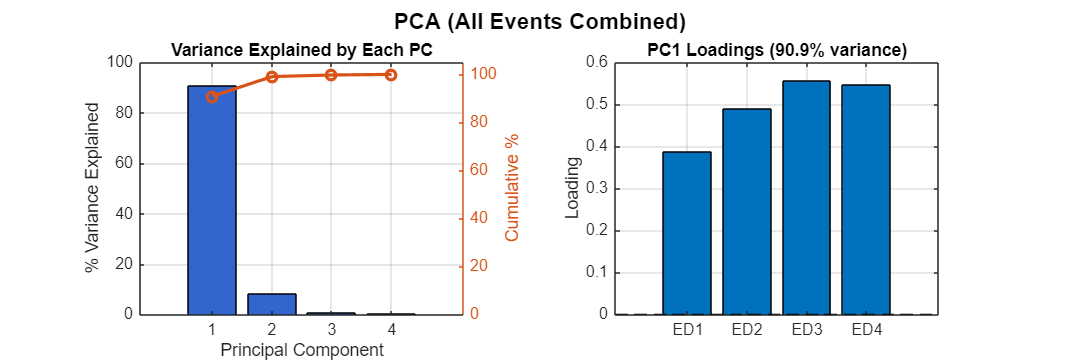



% =======================================
% B&S's MPS on the whole dataset
% =======================================
X_pca = all_data{:, {'ED1','ED2','ED3','ED4'}};
X_pca = fillmissing(X_pca, 'previous');

[loadings_mps, score, ~, ~, ~] = pca_analysis(X_pca, ...
    'Labels', {'ED1','ED2','ED3','ED4'}, ...
    'Title', 'PCA (All Events Combined)', ...
    'NumPCs', 1);


% Store combined MPS loadings
loadings_storage.Combined.MPS_loadings = loadings_mps(:,1);
loadings_storage.Combined.MPS_labels = {'ED1','ED2','ED3','ED4'};

[~, scaled_PC1] = scaling(loadings_mps(:,1), score(:,1), all_data.ED4);
all_data.MPS = scaled_PC1;

% Orthogonalization
all_data_orth = orthogonalize_mps_BS2023(all_data(:, {'Date', 'MPS'}), ...
    macro_data, ...
    'Orthogonalize', true, ...
    'Verbose', true);


=== Bauer & Swanson (2023) Orthogonalization ===
MPS variable used: MPS
Original sample size: 751
Complete cases: 698 (92.9%)
Missing observations: 53
Note: Dataset contains 320 duplicate dates (431 unique dates)
R² of MPS on macro variables: 0.0772
Adj. R²: 0.0705

Regression coefficients:
                    Estimate         SE         tStat        pValue  
                   __________    __________    ________    __________

    (Intercept)    -0.0046999     0.0022461     -2.0924      0.036765
    NFP_YoY         0.0010711    0.00077119      1.3889        0.1653
    SP500_3m          0.13147      0.028697      4.5813    5.4803e-06
    Slope_3m       1.0602e-05    0.00089932    0.011789        0.9906
    BCOM_3m          0.024589      0.025652     0.95857       0.3


all_data = [all_data, all_data_orth(:, {'MPS_ORTH', 'NFP_YoY', 'SP500_3m', 'Slope_3m', 'BCOM_3m', 'Skew_Avg'})];

% =======================================
% Target and Path on the whole dataset
% =======================================

X_gss = all_data{:, {'MP1','MP2', 'ED2', 'ED3','ED4'}};
X_gss = fillmissing(X_gss, 'previous');

[target, path, loadings_gss] = GSS_replication(X_gss);

Correlation between Target and Path: -0.0000 (Should be very close to 0)


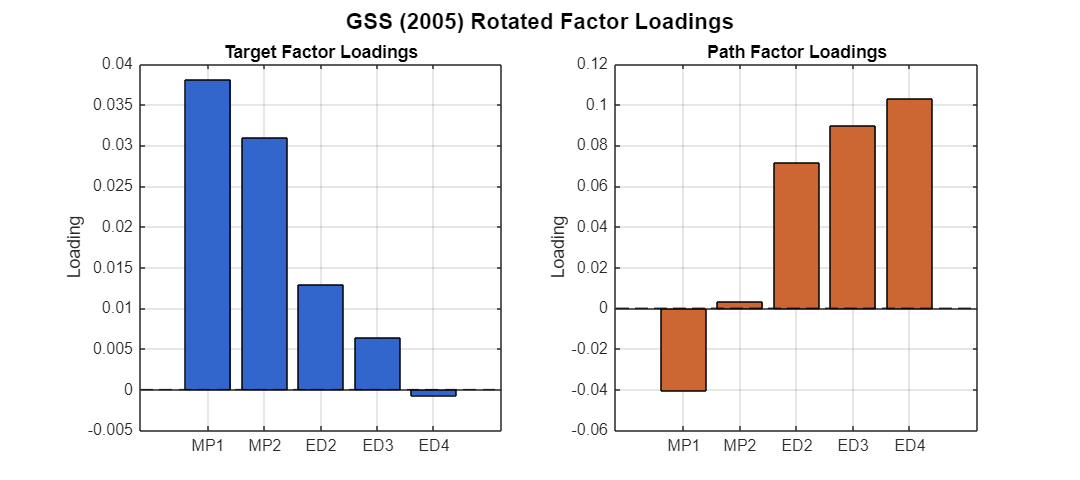


all_data.Target = target;
all_data.Path = path;


surprises_gss = table(all_data.Date, target, path, ...
    'VariableNames', {'Dates', 'Target', 'Path'});

% Plot rotated loadings
labels = {'MP1','MP2','ED2','ED3', 'ED4'};
figure('Position', [100, 100, 900, 400]);
colors = [0.2 0.4 0.8; 0.8 0.4 0.2];
factor_names = {'Target', 'Path'};

for i = 1:2
    subplot(1, 2, i);
    
    b = bar(loadings_gss(:, i), 'FaceColor', colors(i,:));
    
    set(gca, 'XTick', 1:length(labels), 'XTickLabel', labels);
    ylabel('Loading');
    title(sprintf('%s Factor Loadings', factor_names{i}));
    grid on;
    
    hold on;
    yline(0, 'k--', 'LineWidth', 1);
    hold off;
    
    if length(labels) > 6
        xtickangle(45);
    end
end
sgtitle('GSS (2005) Rotated Factor Loadings', 'FontSize', 14, 'FontWeight', 'bold');



% Store combined Target and Path loadings
loadings_storage.Combined.Target_loadings = loadings_gss(:,1);
loadings_storage.Combined.Path_loadings = loadings_gss(:,2);
loadings_storage.Combined.GSS_labels = {'MP1','MP2','ED2','ED3','ED4'};

% =======================================
% Combine with assets
% =======================================
combined_data = outerjoin(all_data, yield_base_extended, ...
    'Keys', 'Date', 'MergeKeys', true, 'Type', 'left');

combined_data = outerjoin(combined_data, sp500_dataset, ...
    'LeftKeys', 'Date', 'RightKeys', 'Dates', 'MergeKeys', true, 'Type', 'left');

combined_data = fillmissing(combined_data, 'previous');
combined_data.Properties.VariableNames{'Date_Dates'} = 'Date';


% =======================================
% Events classification
% =======================================
[indic_opp_all, indic_att_all, indic_hom_all] = classifier_mp_events(table(combined_data.Target, combined_data.Path, ...
    'VariableNames', {'Target', 'Path'}));

fprintf('Opposite signs: %d (%.1f%%)\n', sum(indic_opp_all), 100*sum(indic_opp_all)/height(combined_data));

Opposite signs: 332 (44.2%)


fprintf('Attenuation: %d (%.1f%%)\n', sum(indic_att_all), 100*sum(indic_att_all)/height(combined_data));

Attenuation: 39 (5.2%)


fprintf('HOM: %d (%.1f%%)\n', sum(indic_hom_all), 100*sum(indic_hom_all)/height(combined_data));

HOM: 293 (39.0%)




% =======================================
% Main regressions
% =======================================

% Filter to non-missing MPS_ORTH observations
mask_orth_all = ~isnan(combined_data.MPS_ORTH);

Y_assets_all = [combined_data.SP500_returns(mask_orth_all)*100, combined_data.Diff2y(mask_orth_all), ...
                combined_data.Diff5y(mask_orth_all), combined_data.Diff10y(mask_orth_all)];

% Use orthogonalized MPS
mps_reg_all = combined_data.MPS_ORTH(mask_orth_all);
target_reg_all = combined_data.Target(mask_orth_all);
path_reg_all = combined_data.Path(mask_orth_all);
indic_opp_reg_all = indic_opp_all(mask_orth_all);
indic_att_reg_all = indic_att_all(mask_orth_all);
indic_hom_reg_all = indic_hom_all(mask_orth_all);

%% Table 1: Standard Effects
X_mps_all = mps_reg_all;
X_tp_all = [target_reg_all, path_reg_all];

display_regression_results(Y_assets_all, {X_mps_all, X_tp_all}, ...
    'YNames', {'SP500', '2y', '5y', '10y'}, ...
    'XNames', {{'MPS_ORTH'}, {'Target', 'Path'}}, ...
    'SpecNames', {'Baseline (B&S Orth)', 'Decomposition'}, ...
    'Title', 'Table 1 (Combined) - BS2023 Orthogonalized: Standard MP effects');


Table 1 (Combined) - BS2023 Orthogonalized: Standard MP effects

======= Baseline (B&S Orth) ======= 

                    SP500       2y         5y         10y   
                   _______    _______    _______    ________

    MPS_ORTH       -5.0374    0.59066    0.47243     0.25987
    se_MPS_ORTH     1.2803     0.0534     0.0576    0.047159
    R2             0.04295    0.21754    0.11567    0.044631
    Obs                751        751        751         751


P-values:
                       SP500       2y        5y           10y    
                 


%% Table 2: Opposite Signs
X_opp_all = [mps_reg_all, mps_reg_all .* indic_opp_reg_all, indic_opp_reg_all];

display_regression_results(Y_assets_all, {X_opp_all}, ...
    'YNames', {'SP500', '2y', '5y', '10y'}, ...
    'XNames', {{'MPS_ORTH', 'MPS_ORTH x indic_opp', 'indic_opp'}}, ...
    'Title', 'Table 2 (Combined) - BS2023 Orthogonalized: MP effects with same/opposite sign');


Table 2 (Combined) - BS2023 Orthogonalized: MP effects with same/opposite sign

======= Spec1 ======= 

                                SP500          2y            5y           10y    
                               ________    __________    __________    __________

    MPS_ORTH                    -5.7403       0.49461       0.35655       0.15752
    se_MPS_ORTH                  1.5439      0.060132      0.063558       0.05587
    MPS_ORTH x indic_opp         1.9203       0.24707       0.28714       0.26352
    se_MPS_ORTH x indic_opp      2.7145       0.10853       0.11845      0.098234
    indic_opp              <


%% Table 3: Descriptive Stats
same_sign_all = mps_reg_all(indic_opp_reg_all==0);
opp_sign_all = mps_reg_all(indic_opp_reg_all==1);

rowNames = {'Same Signs','Opposite Signs'};
colNames = {'N','%','Mean','Mean Abs','SD'};
table3_all = array2table(nan(2,5), 'RowNames', rowNames, 'VariableNames', colNames);

table3_all{1,:} = [length(same_sign_all), round(100*length(same_sign_all)/length(mps_reg_all),1), ...
                   round(mean(same_sign_all),3), round(mean(abs(same_sign_all)),3), round(std(same_sign_all),3)];
table3_all{2,:} = [length(opp_sign_all), round(100*length(opp_sign_all)/length(mps_reg_all),1), ...
                   round(mean(opp_sign_all),3), round(mean(abs(opp_sign_all)),3), round(std(opp_sign_all),3)];

fprintf('\nTable 3 (Combined) - BS2023 Orthogonalized: Descriptive Statistics\n');


Table 3 (Combined) - BS2023 Orthogonalized: Descriptive Statistics


disp(table3_all);

                       N      %       Mean     Mean Abs     SD  
                      ___    ____    ______    ________    _____

    Same Signs        419    55.8     0.007     0.036      0.057
    Opposite Signs    332    44.2    -0.006     0.035      0.049




%% Table 4: Higher-Order Moments
X_att_hom_all = [mps_reg_all, mps_reg_all .* indic_att_reg_all, mps_reg_all .* indic_hom_reg_all, indic_att_reg_all, indic_hom_reg_all];
const_all = ones(length(mps_reg_all), 1);

display_regression_results(Y_assets_all, {X_att_hom_all}, ...
    'YNames', {'SP500', '2y', '5y', '10y'}, ...
    'XNames', {{'MPS_ORTH', 'MPS_ORTH x Att', 'MPS_ORTH x HOM', 'Att', 'HOM'}}, ...
    'Title', 'Table 4 (Combined) - BS2023 Orthogonalized: MP effects with HOM signals');


Table 4 (Combined) - BS2023 Orthogonalized: MP effects with HOM signals

======= Spec1 ======= 

                          SP500          2y            5y           10y    
                         ________    __________    __________    __________

    MPS_ORTH              -5.7403       0.49461       0.35655       0.15752
    se_MPS_ORTH            1.5439      0.060132      0.063558       0.05587
    MPS_ORTH x Att        -4.5001       -0.4712      -0.71106      -0.41868
    se_MPS_ORTH x Att      11.441       0.31681       0.45998       0.39425
    MPS_ORTH x HOM         2.4774       0.31452       0.38113 


%% Marginal Effects
colNamesME = {'SP500', '2y', '5y', '10y'};

table_me_att_all = array2table(nan(2,4), 'RowNames', {'Marginal_Att', 'se_att'}, 'VariableNames', colNamesME);
table_me_att_all = me_results(Y_assets_all, [const_all X_att_hom_all], table_me_att_all, [2, 3]);

table_me_hom_all = array2table(nan(2,4), 'RowNames', {'Marginal_Hom', 'se_hom'}, 'VariableNames', colNamesME);
table_me_hom_all = me_results(Y_assets_all, [const_all X_att_hom_all], table_me_hom_all, [2, 4]);

fprintf('\nMarginal Effect: Attenuation (Combined) - BS2023 Orthogonalized\n');


Marginal Effect: Attenuation (Combined) - BS2023 Orthogonalized


disp(table_me_att_all);

                    SP500      2y        5y       10y  
                    ______    _____    ______    ______

    Marginal_Att    -10.24    0.023    -0.355    -0.261
    se_att          11.337    0.311     0.456      0.39



fprintf('\nMarginal Effect: HOM (Combined) - BS2023 Orthogonalized\n');


Marginal Effect: HOM (Combined) - BS2023 Orthogonalized


disp(table_me_hom_all);

                    SP500      2y       5y       10y 
                    ______    _____    _____    _____

    Marginal_Hom    -3.263    0.809    0.738    0.486
    se_hom           2.206    0.093    0.098    0.079




%% R2 Decomposition
[~, ~, r2_same_all, ~] = robust_ols(Y_assets_all(~indic_opp_reg_all,:), mps_reg_all(~indic_opp_reg_all), true);
[~, ~, r2_att_all, ~]  = robust_ols(Y_assets_all(indic_att_reg_all,:), mps_reg_all(indic_att_reg_all), true);
[~, ~, r2_hom_all, ~]  = robust_ols(Y_assets_all(indic_hom_reg_all,:), mps_reg_all(indic_hom_reg_all), true);

res_r2_all = [r2_same_all; r2_att_all; r2_hom_all; repmat(length(mps_reg_all),1,4)];
tab_r2_all = array2table(res_r2_all, 'RowNames', {'R2 Same', 'R2 Att', 'R2 HOM', 'Obs'}, 'VariableNames', colNamesME);
fprintf('\nR2 Decomposition (Combined) - BS2023 Orthogonalized\n');


R2 Decomposition (Combined) - BS2023 Orthogonalized


disp(tab_r2_all);

                SP500          2y           5y         10y   
               ________    __________    ________    ________

    R2 Same    0.067426       0.19696    0.096246    0.024297
    R2 Att     0.073632    0.00041289    0.038076      0.0244
    R2 HOM     0.014705       0.28156     0.18484     0.10097
    Obs             751           751         751         751




%% Table 9: TIPS Analysis
combined_data_orth_all = combined_data(mask_orth_all, :);
[~, idx_comb_all, idx_tips_all] = intersect(combined_data_orth_all.Date, tips_changes_dataset.Dates);

if isempty(idx_comb_all)
    fprintf('\nWarning: No overlapping dates for TIPS analysis.\n');
else
    Y_tips_vals_all = [combined_data_orth_all.Diff2y(idx_comb_all), combined_data_orth_all.Diff5y(idx_comb_all), combined_data_orth_all.Diff10y(idx_comb_all), ...
                       tips_changes_dataset.TIPSY02(idx_tips_all), tips_changes_dataset.TIPSY05(idx_tips_all), tips_changes_dataset.TIPSY10(idx_tips_all), ...
                       tips_changes_dataset.BKEVEN02(idx_tips_all), tips_changes_dataset.BKEVEN05(idx_tips_all), tips_changes_dataset.BKEVEN10(idx_tips_all)];
    Y_tips_vals_all = fillmissing(Y_tips_vals_all, 'previous');
    
    X_tips_all = X_att_hom_all(idx_comb_all, :);
    const_tips_all = ones(length(idx_comb_all), 1);
    indic_hom_tips_all = indic_hom_reg_all(idx_comb_all);
    mps_tips_all = mps_reg_all(idx_comb_all);
    
    tipsNames = {'NIR-2y','NIR-5y','NIR-10y','RIR-2y','RIR-5y','RIR-10y','IC-2y','IC-5y','IC-10y'};
    
    display_regression_results(Y_tips_vals_all, {X_tips_all}, ...
        'YNames', tipsNames, ...
        'XNames', {{'MPS_ORTH', 'MPS_ORTH x Att', 'MPS_ORTH x HOM', 'Att', 'HOM'}}, ...
        'Title', 'Table 9 (Combined) - BS2023 Orthogonalized: Real Rates & Inflation Comp.');
    
    tab_me_tips_all = array2table(nan(2,9), 'RowNames', {'Marginal_Hom', 'se_hom'}, 'VariableNames', tipsNames);
    tab_me_tips_all = me_results(Y_tips_vals_all, [const_tips_all X_tips_all], tab_me_tips_all, [2, 4]);
    fprintf('\nMarginal Effect: HOM - TIPS (Combined) - BS2023 Orthogonalized\n');
    disp(tab_me_tips_all);
    
    [~, ~, r2_s_tips_all, ~] = robust_ols(Y_tips_vals_all(~indic_hom_tips_all,:), mps_tips_all(~indic_hom_tips_all), true);
    [~, ~, r2_h_tips_all, ~] = robust_ols(Y_tips_vals_all(indic_hom_tips_all,:), mps_tips_all(indic_hom_tips_all), true);
    
    res_r2_tips_all = [r2_s_tips_all; r2_h_tips_all; repmat(length(idx_comb_all),1,9)];
    tab_r2_tips_all = array2table(res_r2_tips_all, 'RowNames', {'R2 Other', 'R2 HOM', 'Obs'}, 'VariableNames', tipsNames);
    fprintf('\nR2 Decomposition - TIPS (Combined) - BS2023 Orthogonalized\n');
    disp(tab_r2_tips_all);
end


Table 9 (Combined) - BS2023 Orthogonalized: Real Rates & Inflation Comp.

======= Spec1 ======= 

                           NIR-2y        NIR-5y        NIR-10y       RIR-2y        RIR-5y       RIR-10y       IC-2y        IC-5y       IC-10y  
                         __________    __________    ___________    _________    __________    __________    ________    _________    _________

    MPS_ORTH                0.42585       0.26892        0.10121      0.11816       0.30911        0.1872     0.30224    -0.052


Marginal Effect: HOM - TIPS (Combined) - BS2023 Orthogonalized


                    NIR-2y    NIR-5y    NIR-10y    RIR-2y    RIR-5y    RIR-10y    IC-2y    IC-5y    IC-10y
                    ______    ______    _______    ______    ______    _______    _____    _____    ______

    Marginal_Hom    0.725     0.681       0.46     0.794     0.845      0.588     0.121    0.006    -0.029
    se_hom           0.15     0.154      0.134     0.216     0.166      0.137     0.179    0.089     0.061




R2 Decomposition - TIPS (Combined) - BS2023 Orthogonalized


                NIR-2y      NIR-5y      NIR-10y      RIR-2y       RIR-5y     RIR-10y       IC-2y        IC-5y        IC-10y  
                _______    ________    _________    _________    ________    ________    _________    __________    _________

    R2 Other    0.11243    0.033253    0.0044537    0.0011622    0.052819    0.031603    0.0092503     0.0099796     0.034465
    R2 HOM      0.19399     0.13011     0.070113     0.052873     0.15432     0.10694       0.0014    3.3051e-05    0.0012965
    Obs             429         429          429          429         429         429          429           429          429




%% Breakdown by sheet
fprintf('\n\n================================================================================\n');

fprintf('BREAKDOWN BY SHEET\n');

BREAKDOWN BY SHEET


fprintf('================================================================================\n');


for i = 1:length(sheet_names)
    sheet_mask = strcmp(combined_data.Sheet, sheet_names{i}) & mask_orth_all;
    fprintf('\n%s: %d events (%.1f%% of orthogonalized sample)\n', ...
        sheet_names{i}, sum(sheet_mask), 100*sum(sheet_mask)/sum(mask_orth_all));
    
    % Statistics by sheet
    mps_sheet = mps_reg_all(strcmp(combined_data_orth_all.Sheet, sheet_names{i}));
    if ~isempty(mps_sheet)
        fprintf('  MPS_ORTH - Mean: %.4f, Std: %.4f, Min: %.4f, Max: %.4f\n', ...
            mean(mps_sheet), std(mps_sheet), min(mps_sheet), max(mps_sheet));
    end
end


Statements: 231 events (30.8% of orthogonalized sample)


  MPS_ORTH - Mean: 0.0005, Std: 0.0599, Min: -0.3887, Max: 0.1548



Press Conferences: 89 events (11.9% of orthogonalized sample)


  MPS_ORTH - Mean: -0.0001, Std: 0.0512, Min: -0.2315, Max: 0.1852



Monetary Events: 231 events (30.8% of orthogonalized sample)


  MPS_ORTH - Mean: -0.0031, Std: 0.0643, Min: -0.3887, Max: 0.1548



Minutes: 200 events (26.6% of orthogonalized sample)


  MPS_ORTH - Mean: 0.0078, Std: 0.0295, Min: -0.1588, Max: 0.1064



fprintf('\n=== Sample composition after orthogonalization ===\n');


=== Sample composition after orthogonalization ===


fprintf('Total observations with MPS_ORTH: %d\n', sum(mask_orth_all));

Total observations with MPS_ORTH: 751


fprintf('Original total observations: %d\n', height(combined_data));

Original total observations: 751


fprintf('Observations dropped (missing macro data): %d (%.1f%%)\n', ...
    sum(~mask_orth_all), 100*sum(~mask_orth_all)/height(combined_data));

Observations dropped (missing macro data): 0 (0.0%)


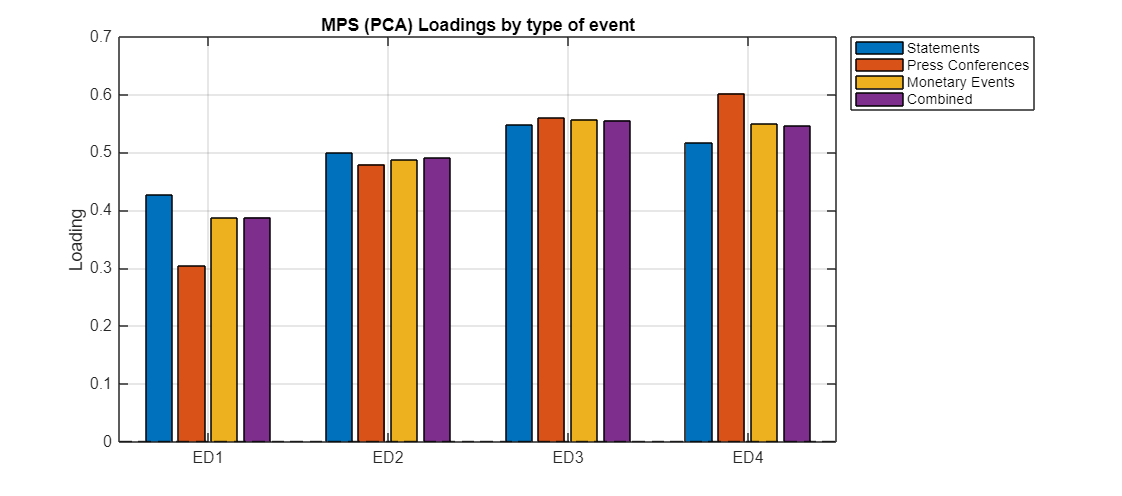

%% ================================================
% Loadings by sheet + Target/Path scatter
% ================================================

%% ---- Sheets to include 
sheets_plot = {'Statements','Press Conferences','Monetary Events', 'Combined'};
sheet_field = cellfun(@matlab.lang.makeValidName, sheets_plot, 'UniformOutput', false);

%% =========================
% MPS loadings by sheet
% =========================
labels_mps = {'ED1','ED2','ED3','ED4'};
L_mps = nan(numel(labels_mps), numel(sheet_field));

for j = 1:numel(sheet_field)
    f = sheet_field{j};
    if isfield(loadings_storage, f) && isfield(loadings_storage.(f), 'MPS_loadings')
        L_mps(:,j) = loadings_storage.(f).MPS_loadings(:);
    else
        warning('Missing MPS_loadings for: %s', sheets_plot{j});
    end
end

figure('Position',[120 120 950 420]);
bar(L_mps, 'grouped');
grid on; yline(0,'k--','LineWidth',1);
set(gca,'XTick',1:numel(labels_mps),'XTickLabel',labels_mps);
ylabel('Loading');
title('MPS (PCA) Loadings by type of event');
legend(sheets_plot,'Location','bestoutside');

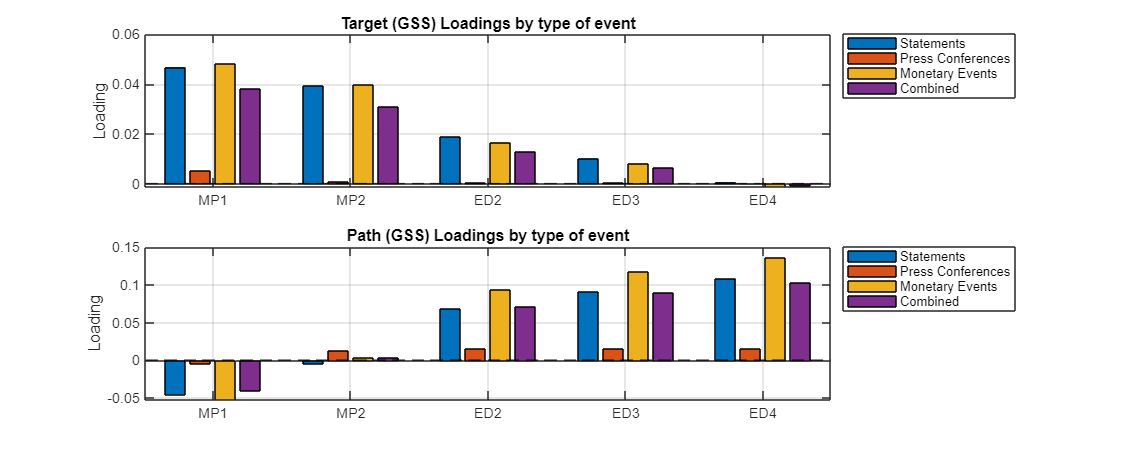


%% =========================
% Target & Path loadings by sheet
% =========================
labels_gss = {'MP1','MP2','ED2','ED3','ED4'};
L_target = nan(numel(labels_gss), numel(sheet_field));
L_path   = nan(numel(labels_gss), numel(sheet_field));

for j = 1:numel(sheet_field)
    f = sheet_field{j};
    
    if isfield(loadings_storage, f) && isfield(loadings_storage.(f), 'Target_loadings')
        L_target(:,j) = loadings_storage.(f).Target_loadings(:);
    else
        warning('Missing Target_loadings for: %s', sheets_plot{j});
    end
    
    if isfield(loadings_storage, f) && isfield(loadings_storage.(f), 'Path_loadings')
        L_path(:,j) = loadings_storage.(f).Path_loadings(:);
    else
        warning('Missing Path_loadings for: %s', sheets_plot{j});
    end
end

figure('Position',[140 140 1050 420]);
subplot(2,1,1)
bar(L_target, 'grouped');
grid on; yline(0,'k--','LineWidth',1);
set(gca,'XTick',1:numel(labels_gss),'XTickLabel',labels_gss);
ylabel('Loading');
title('Target (GSS) Loadings by type of event');
legend(sheets_plot,'Location','bestoutside');

subplot(2,1,2)
bar(L_path, 'grouped');
grid on; yline(0,'k--','LineWidth',1);
set(gca,'XTick',1:numel(labels_gss),'XTickLabel',labels_gss);
ylabel('Loading');
title('Path (GSS) Loadings by type of event');
legend(sheets_plot,'Location','bestoutside');

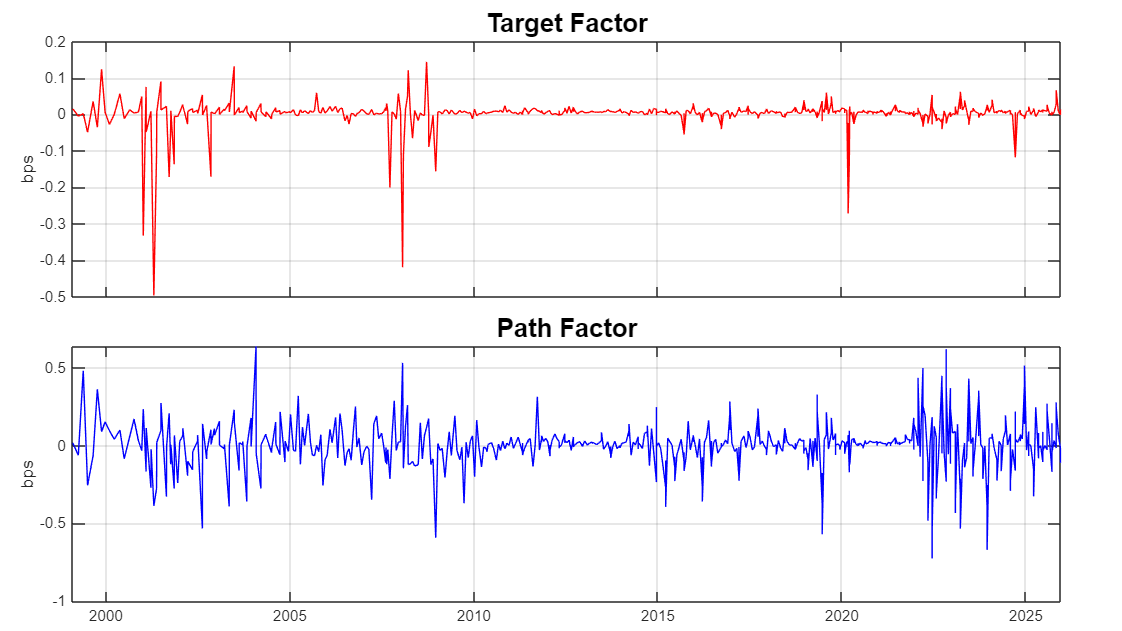

f9 = figure("Units","normalized","Position",[0,0,1,1]);
t = tiledlayout(2,1,'Padding','compact','TileSpacing','compact');
nexttile 
plot(combined_data.Date, target_reg_all,'r'); 
title("Target Factor", 'FontSize', 16, 'FontWeight', 'bold');
ylabel("bps"); 
xticklabels({}); 
grid on;

nexttile  
plot(combined_data.Date, path_reg_all, 'b'); 
title("Path Factor", 'FontSize', 16, 'FontWeight', 'bold');
ylabel("bps"); 
grid on;

exportgraphics(f9, 'graphs/factors_all.pdf', 'ContentType', 'vector');

%% =========================================================
% ACM Term Premium Analysis on combined dataset
% =========================================================

fprintf('\n\n================================================================================\n');

fprintf('ACM TERM PREMIUM ANALYSIS (COMBINED DATASET)\n');

ACM TERM PREMIUM ANALYSIS (COMBINED DATASET)


fprintf('================================================================================\n');


% Import the ACM database and align dates
raw_acm = readtable('data\ACMTermPremium.xls', 'Sheet', 'ACM Daily');
raw_acm.DATE = datetime(raw_acm.DATE);

% Calculate changes in ACM variables
acm_changes = diff(raw_acm(:,2:size(raw_acm,2)), 1);
acm_changes_dataset = array2table(raw_acm.DATE(2:size(raw_acm.DATE,1)), ...
    'VariableNames', {'Dates'});
acm_changes_dataset = [acm_changes_dataset acm_changes];

% Extract dates from orthogonalized sample
dates_reg_all = combined_data.Date(mask_orth_all);
combined_dates_table = table(dates_reg_all, 'VariableNames', {'Dates'});

% Outer join with ACM data (keep all combined_data dates)
acm_merged = outerjoin(combined_dates_table, acm_changes_dataset, ...
    'Keys', 'Dates', 'MergeKeys', true, 'Type', 'left');

% Forward fill missing ACM values
acm_merged = fillmissing(acm_merged, 'previous');

% Check for remaining NaN values
n_missing = sum(any(isnan(acm_merged{:,2:end}), 2));
if n_missing > 0
    fprintf('\nWarning: %d observations still have missing ACM data after forward fill.\n', n_missing);
    fprintf('These observations will be dropped from the ACM analysis.\n');
end

% Create mask for valid ACM observations (no NaN)
mask_valid_acm = ~any(isnan(acm_merged{:,2:end}), 2);

if sum(mask_valid_acm) == 0
    fprintf('\nWarning: No valid observations for ACM analysis after forward fill.\n');
else
    fprintf('\nNumber of valid observations: %d (out of %d)\n', ...
            sum(mask_valid_acm), length(mask_valid_acm));
    
    % Create expectation hypothesis change estimates as the difference
    % between nominal yield and term premium
    eh_changes = table(...
        acm_merged.ACMY02(mask_valid_acm) - acm_merged.ACMTP02(mask_valid_acm), ...
        acm_merged.ACMY05(mask_valid_acm) - acm_merged.ACMTP05(mask_valid_acm), ...
        acm_merged.ACMY10(mask_valid_acm) - acm_merged.ACMTP10(mask_valid_acm), ...
        'VariableNames', {'ACMEH02', 'ACMEH05', 'ACMEH10'});
    
    % Prepare regression variables
    Y_acm_all = [acm_merged.ACMY02(mask_valid_acm), ...
                 acm_merged.ACMY05(mask_valid_acm), ...
                 acm_merged.ACMY10(mask_valid_acm), ...
                 eh_changes.ACMEH02, ...
                 eh_changes.ACMEH05, ...
                 eh_changes.ACMEH10, ...
                 acm_merged.ACMTP02(mask_valid_acm), ...
                 acm_merged.ACMTP05(mask_valid_acm), ...
                 acm_merged.ACMTP10(mask_valid_acm)];
    
    % Extract corresponding X variables
    mps_acm_all = mps_reg_all(mask_valid_acm);
    indic_att_acm_all = indic_att_reg_all(mask_valid_acm);
    indic_hom_acm_all = indic_hom_reg_all(mask_valid_acm);
    
    X_att_hom_acm_all = [mps_acm_all, ...
                         mps_acm_all .* indic_att_acm_all, ...
                         mps_acm_all .* indic_hom_acm_all, ...
                         indic_att_acm_all, ...
                         indic_hom_acm_all];
    
    colNames_acm = {'NIR-2y','NIR-5y','NIR-10y','EH-2y',...
                    'EH-5y','EH-10y','TP-2y','TP-5y','TP-10y'};
    
    % Main regression
    display_regression_results(Y_acm_all, {X_att_hom_acm_all}, ...
        'YNames', colNames_acm, ...
        'XNames', {{'MPS_ORTH', 'MPS_ORTH x Att', 'MPS_ORTH x HOM', 'Att', 'HOM'}}, ...
        'Title', 'Table 10 (Combined) - BS2023 Orthogonalized: Decomposition of nominal rates (EH and TP)');
    
    % Marginal effects
    const_acm_all = ones(sum(mask_valid_acm), 1);
    
    % HOM marginal effect
    tab_me_hom_acm_all = array2table(nan(2, length(colNames_acm)), ...
        'RowNames', {'Marginal_Hom', 'se_hom'}, 'VariableNames', colNames_acm);
    tab_me_hom_acm_all = me_results(Y_acm_all, [const_acm_all X_att_hom_acm_all], ...
                                     tab_me_hom_acm_all, [2, 4]);
    
    fprintf('\n==== Marginal Effect: HOM (ACM - Combined) ====\n');
    disp(tab_me_hom_acm_all);
    
    % Attenuation marginal effect
    tab_me_att_acm_all = array2table(nan(2, length(colNames_acm)), ...
        'RowNames', {'Marginal_Att', 'se_att'}, 'VariableNames', colNames_acm);
    tab_me_att_acm_all = me_results(Y_acm_all, [const_acm_all X_att_hom_acm_all], ...
                                     tab_me_att_acm_all, [2, 3]);
    
    fprintf('\n==== Marginal Effect: Attenuation (ACM - Combined) ====\n');
    disp(tab_me_att_acm_all);
    
    % R2 decomposition by event type
    [~, ~, r2_same_acm_all, ~] = robust_ols(Y_acm_all(~indic_hom_acm_all,:), ...
                                             mps_acm_all(~indic_hom_acm_all), true);
    [~, ~, r2_hom_acm_all, ~] = robust_ols(Y_acm_all(indic_hom_acm_all,:), ...
                                            mps_acm_all(indic_hom_acm_all), true);
    
    results_r2_acm_all = [r2_same_acm_all; r2_hom_acm_all; repmat(sum(mask_valid_acm), 1, length(colNames_acm))];
    tab_r2_acm_all = array2table(results_r2_acm_all, ...
        'RowNames', {'R2 Other', 'R2 HOM', 'Obs'}, ...
        'VariableNames', colNames_acm);
    
    fprintf('\n==== R2 Decomposition (ACM - Combined) ====\n');
    disp(tab_r2_acm_all);
    
    % Summary statistics by event type
    fprintf('\n==== Event Type Distribution (ACM sample) ====\n');
    fprintf('Same signs: %d (%.1f%%)\n', sum(~indic_hom_acm_all), ...
            100*sum(~indic_hom_acm_all)/length(indic_hom_acm_all));
    fprintf('HOM events: %d (%.1f%%)\n', sum(indic_hom_acm_all), ...
            100*sum(indic_hom_acm_all)/length(indic_hom_acm_all));
    fprintf('Attenuation events: %d (%.1f%%)\n', sum(indic_att_acm_all), ...
            100*sum(indic_att_acm_all)/length(indic_att_acm_all));
end


Number of valid observations: 751 (out of 751)



Table 10 (Combined) - BS2023 Orthogonalized: Decomposition of nominal rates (EH and TP)

======= Spec1 ======= 

                           NIR-2y        NIR-5y       NIR-10y        EH-2y         EH-5y         EH-10y        TP-2y         TP-5y        TP-10y  
                         __________    __________    __________    __________    __________    __________    _________    ___________    _________

    MPS_ORTH                0.49802        0.3644       0.17223        0.5218       0.48063        0.3786 


==== Marginal Effect: HOM (ACM - Combined) ====


                    NIR-2y    NIR-5y    NIR-10y    EH-2y    EH-5y    EH-10y    TP-2y    TP-5y    TP-10y
                    ______    ______    _______    _____    _____    ______    _____    _____    ______

    Marginal_Hom    0.924     0.863      0.583      0.56    0.685    0.585     0.363    0.179    -0.001
    se_hom          0.087     0.098      0.079     0.111    0.102    0.082     0.068    0.051     0.067




==== Marginal Effect: Attenuation (ACM - Combined) ====


                    NIR-2y    NIR-5y    NIR-10y    EH-2y    EH-5y    EH-10y    TP-2y     TP-5y     TP-10y
                    ______    ______    _______    _____    _____    ______    ______    ______    ______

    Marginal_Att    0.144     -0.286    -0.225     0.367    0.067    -0.019    -0.223    -0.353    -0.206
    se_att          0.302      0.458     0.399     0.314     0.34     0.289     0.054     0.179     0.213




==== R2 Decomposition (ACM - Combined) ====


                NIR-2y      NIR-5y     NIR-10y      EH-2y      EH-5y     EH-10y       TP-2y       TP-5y        TP-10y  
                _______    ________    ________    _______    _______    _______    _________    ________    __________

    R2 Other    0.19042    0.075223    0.018825    0.23788    0.19023    0.17187    0.0045862    0.033364      0.047876
    R2 HOM      0.34727     0.23687     0.13407    0.16246     0.2267    0.23954      0.16691    0.033214    1.3578e-06
    Obs             751         751         751        751        751        751          751         751           751




==== Event Type Distribution (ACM sample) ====


Same signs: 458 (61.0%)


HOM events: 293 (39.0%)


Attenuation events: 39 (5.2%)



fprintf('\n================================================================================\n');

### *Controls with extended dataset*

%% =========================================================
%  FFTR decision-type controls on the FULL orthogonalized sample
%  (1994--2025, using MPS_ORTH)
% =========================================================

% Dates used in the main regressions (orthogonalized sample)
dates_reg_all = combined_data.Date(mask_orth_all);

% --- Load FFTR and align to regression dates
FFTR = readtable("data\FED_rates.xlsx");
FFTR.Date = datetime(FFTR.Date);

% Ensure dates are sorted
FFTR = sortrows(FFTR, "Date");

% Match FFTR dates to regression dates
[isMatch, idxFFTR] = ismember(dates_reg_all, FFTR.Date);
if any(~isMatch)
    warning("Some regression dates are missing in FED_rates.xlsx (%d missing). Dropping them.", sum(~isMatch));
end

% Keep only dates with FFTR available (align everything)
dates_reg_all2    = dates_reg_all(isMatch);
Y_assets_all2     = Y_assets_all(isMatch, :);
mps_reg_all2      = mps_reg_all(isMatch);          % MPS_ORTH
indic_att_all2    = indic_att_reg_all(isMatch);
indic_hom_all2    = indic_hom_reg_all(isMatch);

% Decision rate series aligned
rate_all = FFTR.FFTR(idxFFTR(isMatch));

% --- Build decision-type dummies within the aligned event sample
Hike_all = [false; rate_all(2:end) > rate_all(1:end-1)];
Cut_all  = [false; rate_all(2:end) < rate_all(1:end-1)];
Hold_all = [false; rate_all(2:end) == rate_all(1:end-1)];

% For the first observation, force a baseline (as you did before)
Hold_all(1) = true;
Cut_all(1)  = false;
Hike_all(1) = false;

% Sanity check: exactly one category per obs
if any((Hike_all + Cut_all + Hold_all) ~= 1)
    warning("Decision dummies are not mutually exclusive/exhaustive for some rows.");
end

% --- Regression design matrix (baseline category = Cut)
X_att_hom_dec_all = [ ...
    mps_reg_all2, ...
    mps_reg_all2 .* indic_att_all2, ...
    mps_reg_all2 .* indic_hom_all2, ...
    indic_att_all2, ...
    indic_hom_all2, ...
    mps_reg_all2 .* Hike_all, ...
    mps_reg_all2 .* Hold_all, ...
    Hike_all, ...
    Hold_all ...
];

% Run regression
display_regression_results(Y_assets_all2, {X_att_hom_dec_all}, ...
    'YNames', {'SP500', '2y', '5y', '10y'}, ...
    'XNames', {{ ...
        'MPS_ORTH', ...
        'MPS_ORTH x indic_att', ...
        'MPS_ORTH x indic_hom', ...
        'indic_att', ...
        'indic_hom', ...
        'MPS_ORTH x Hike', ...
        'MPS_ORTH x Hold', ...
        'Hike', ...
        'Hold' ...
    }}, ...
    'Title', 'Controlling for the type of decision (Full sample, MPS_ORTH)');


Controlling for the type of decision (Full sample, MPS_ORTH)

======= Spec1 ======= 

                                SP500          2y            5y           10y    
                               ________    __________    __________    __________

    MPS_ORTH                     -8.573       0.35345       0.24386       0.15573
    se_MPS_ORTH                  2.8261       0.14744       0.15087       0.13461
    MPS_ORTH x indic_att        -4.9535      -0.47996      -0.70455      -0.40069
    se_MPS_ORTH x indic_att      11.363       0.31436       0.45027        0.3915
    MPS_ORTH x indic_hom         1.81


% Marginal effect for HOM
const_all2 = ones(length(mps_reg_all2), 1);
colNames = {'SP500', '2y', '5y', '10y'};
tab_me_hom_all2 = array2table(nan(2, length(colNames)), ...
    'RowNames', {'Marginal_Hom', 'se_hom'}, 'VariableNames', colNames);

% HOM statements
tab_me_hom_all2 = array2table(nan(2, length(colNames)), ...
    'RowNames', {'Marginal_Hom', 'se_hom'}, 'VariableNames', colNames);

tab_me_hom_all2 = me_results(Y_assets_all2, [const_all2 X_att_hom_dec_all], tab_me_hom_all2, [2, 4]);
disp('==== Marginal Effect: HOM (Full sample, decision controls) ====');

==== Marginal Effect: HOM (Full sample, decision controls) ====


disp(tab_me_hom_all2);

                    SP500      2y       5y       10y 
                    ______    _____    _____    _____

    Marginal_Hom    -6.757    0.644    0.595    0.483
    se_hom            3.94    0.207    0.214    0.181




% Attenuation statements
tab_me_att_all2 = array2table(nan(2, length(colNames)), ...
    'RowNames', {'Marginal_Att', 'se_att'}, 'VariableNames', colNames);

tab_me_att_all2 = me_results(Y_assets_all2, [const_all2 X_att_hom_dec_all], tab_me_att_all2, [2, 3]);
fprintf('\n==== Marginal Effect: Attenuation (Full sample, decision controls) ====\n');


==== Marginal Effect: Attenuation (Full sample, decision controls) ====


disp(tab_me_att_all2);

                     SP500       2y        5y       10y  
                    _______    ______    ______    ______

    Marginal_Att    -13.526    -0.127    -0.461    -0.245
    se_att           11.546     0.353     0.481     0.419



% =======================================
% QE Control Setup
% =======================================
QE_dates_list = [ ...
    datetime(2008, 11, 25); % QE1
    datetime(2009, 03, 18); % QE1 expansion
    datetime(2010, 11, 03); % QE2
    datetime(2011, 09, 21); % Operation Twist
    datetime(2012, 09, 13); % QE3
    datetime(2013, 12, 18); % Tapering start (souvent inclus comme event majeur)
    datetime(2014, 10, 29); % QE3 end
];

I_QE_all = ismember(combined_data.Date, QE_dates_list);
I_QE_reg_all = I_QE_all(mask_orth_all);
fprintf('Number of QE events in regression sample: %d\n', sum(I_QE_reg_all));

Number of QE events in regression sample: 14


X_att_hom_qe_all = [ ...
    mps_reg_all, ...                     % MPS
    mps_reg_all .* indic_att_reg_all, ...% MPS x Attenuation
    mps_reg_all .* indic_hom_reg_all, ...% MPS x HOM
    indic_att_reg_all, ...               % Dummy Attenuation
    indic_hom_reg_all, ...               % Dummy HOM
    mps_reg_all .* I_QE_reg_all, ...     % MPS x QE
    I_QE_reg_all ...                     % Dummy QE
];

display_regression_results(Y_assets_all, {X_att_hom_qe_all}, ...
    'YNames', {'SP500', '2y', '5y', '10y'}, ...
    'XNames', {{ ...
        'MPS_ORTH', ...
        'MPS x Att', ...
        'MPS x HOM', ...
        'Att', ...
        'HOM', ...
        'MPS x QE', ...
        'QE' ...
    }}, ...
    'Title', 'Table Robustness (Combined): Controlling for QE periods')


Table Robustness (Combined): Controlling for QE periods

======= Spec1 ======= 

                      SP500          2y            5y           10y    
                    _________    __________    __________    __________

    MPS_ORTH          -5.3585       0.48179       0.34124       0.15415
    se_MPS_ORTH        1.5744      0.061066      0.064712      0.056556
    MPS x Att          -4.933      -0.45656      -0.69151      -0.41049
    se_MPS x Att       11.296       0.32019       0.46334       0.39826
    MPS x HOM          2.3123       0.31979       0.38209       0.31885
    se_MPS x HOM

const_qe_all = ones(length(mps_reg_all), 1);
colNamesME = {'SP500', '2y', '5y', '10y'};
table_me_hom_qe = array2table(nan(2,4), 'RowNames', {'Marginal_Hom_QE', 'se_hom_qe'}, 'VariableNames', colNamesME);
table_me_hom_qe = me_results(Y_assets_all, [const_qe_all X_att_hom_qe_all], table_me_hom_qe, [2, 4]);

fprintf('\nMarginal Effect: HOM (Controlling for QE)\n');


Marginal Effect: HOM (Controlling for QE)


disp(table_me_hom_qe);

                       SP500      2y       5y       10y 
                       ______    _____    _____    _____

    Marginal_Hom_QE    -3.046    0.802    0.723    0.473
    se_hom_qe           2.207    0.092    0.095    0.074



% =======================================
% Euro area 
% =======================================

raw_eu_mpd_dataset = readtable('data\Dataset_EA-MPD.xlsx', 'Sheet', 'Press Release Window');
raw_eu_mpd_dataset.date = datetime(raw_eu_mpd_dataset.date);
mask = raw_eu_mpd_dataset.date>= datetime(1999,1,1) ;
eu_mpd_dataset = raw_eu_mpd_dataset(mask,:);

% Factors construction
eu_target = eu_mpd_dataset.OIS_1M;
mdl = fitlm(eu_target, eu_mpd_dataset.OIS_1Y);
eu_path = mdl.Residuals.Raw;
eu_target = eu_target./std(eu_target);
eu_path = eu_path./std(eu_path);
disp(['Target/Path correlation: ', num2str(corr(eu_target, eu_path))]);

Target/Path correlation: -1.188e-16


mps_base_eu = table(eu_target, eu_path, 'VariableNames', {'Target','Path'});
mps_base_eu.Total = eu_mpd_dataset.OIS_1Y;

% Indicators for HOM statements
[indic_opp_eu, indic_att_eu, indic_hom_eu] = classifier_mp_events(mps_base_eu);

% Regressions
Y_eu = [eu_mpd_dataset.STOXX50 eu_mpd_dataset.DE2Y eu_mpd_dataset.DE5Y eu_mpd_dataset.DE10Y];
X_att_hom_eu = [mps_base_eu.Total mps_base_eu.Total.* indic_att_eu ...
                mps_base_eu.Total.* indic_hom_eu indic_att_eu indic_hom_eu];
const = ones(height(mps_base_eu), 1);
display_regression_results(Y_eu, {X_att_hom_eu}, ...
    'YNames', {'STOXX50', '2y', '5y', '10y'}, ...
    'XNames', {{'MPS', 'MPS x indic_att', 'MPS x indic_hom', 'indic_att', 'indic_hom'}}, ...
    'Title', 'Table 8: Euro area evidence, full sample');


Table 8: Euro area evidence, full sample

======= Spec1 ======= 

                           STOXX50         2y          5y           10y   
                          __________    ________    _________    _________

    MPS                    -0.059032     0.85089      0.60005      0.21243
    se_MPS                   0.02178    0.055321       0.0707     0.080164
    MPS x indic_att        0.0083091    -0.43786     -0.56405     -0.39245
    se_MPS x indic_att      0.025258     0.15895      0.18892       0.1793
    MPS x indic_hom         0.013831     0.33724      0.63492      0.65018
    se_MPS x ind


% Marginal effects of MPS depending on the type of statement

colNames = {'STOXX50', '2y', '5y', '10y'}; 

% HOM statements
rowNames_Hom = {'Marginal_Hom', 'se_hom'};
table_me_hom = array2table(nan(2, length(colNames)), ...
    'RowNames', rowNames_Hom, 'VariableNames', colNames);
table_me_hom = me_results(Y_eu, [const X_att_hom_eu], table_me_hom, [2, 4]);

disp('==== Marginal Effect: HOM ====');

==== Marginal Effect: HOM ====


disp(table_me_hom);

                    STOXX50     2y       5y       10y 
                    _______    _____    _____    _____

    Marginal_Hom    -0.045     1.188    1.235    0.863
    se_hom           0.014     0.112    0.115    0.106




% R2 on the subsamples
[~, ~, r2_same, n_same] = robust_ols(Y_eu(~indic_hom_eu,:), mps_base_eu.Total(~indic_hom_eu), true);
[~, ~, r2_hom, n_hom] = robust_ols(Y_eu(indic_hom_eu,:), mps_base_eu.Total(indic_hom_eu), true);

results_r2_subsamples = [r2_same; r2_hom; repmat(height(Y_eu), 1, width(Y_eu))];
rowNamesR2 = {'R2 Other', 'R2 HOM', 'Obs'};
table_r2_final = array2table(results_r2_subsamples, 'RowNames', rowNamesR2, 'VariableNames', colNames);
disp(' ==== R2 Decomposition ====');

 ==== R2 Decomposition ====


disp(table_r2_final);

                STOXX50      2y         5y         10y   
                _______    _______    _______    ________

    R2 Other    0.15445    0.69767    0.39768    0.058435
    R2 HOM      0.10147    0.81009    0.77642     0.65272
    Obs             315        315        315         315



%% ============================
% Triple interactions: MPS x HOM x Sheet
% Reference category: Statements
% ============================

% Work on the same filtered sample as before
sheet_all = combined_data.Sheet(mask_orth_all);

D_PC = strcmp(sheet_all, 'Press Conferences');
D_ME = strcmp(sheet_all, 'Monetary Events');
D_MIN = strcmp(sheet_all, 'Minutes');   % optional (see note below)

% If Minutes give you issues, just comment D_MIN and remove it from X.
% Also: Statements is the omitted category (when all dummies = 0).

MPS = mps_reg_all;
Att = indic_att_reg_all;
HOM = indic_hom_reg_all;

% --- Baseline HOM spec + sheet controls + sheet-varying slopes
X_triple = [ ...
    MPS, ...
    MPS.*Att, ...
    MPS.*HOM, ...                         % HOM effect in reference sheet (Statements)
    Att, ...
    HOM, ...
    D_PC, D_ME, D_MIN, ...                % sheet FE (levels)
    MPS.*D_PC, MPS.*D_ME, MPS.*D_MIN, ...  % allow baseline MPS slope differ by sheet
    (MPS.*HOM).*D_PC, ...
    (MPS.*HOM).*D_ME, ...
    (MPS.*HOM).*D_MIN ...
];

XNames_triple = { ...
    'MPS_ORTH', ...
    'MPS_ORTH x Att', ...
    'MPS_ORTH x HOM', ...
    'Att', ...
    'HOM', ...
    'D_PC', 'D_ME', 'D_Minutes', ...
    'MPS_ORTH x D_PC', 'MPS_ORTH x D_ME', 'MPS_ORTH x D_Minutes', ...
    'MPS_ORTH x HOM x D_PC', ...
    'MPS_ORTH x HOM x D_ME', ...
    'MPS_ORTH x HOM x D_Minutes' ...
};

display_regression_results(Y_assets_all, {X_triple}, ...
    'YNames', {'SP500', '2y', '5y', '10y'}, ...
    'XNames', {XNames_triple}, ...
    'Title', 'Triple interactions: MPS x HOM x Sheet (ref = Statements)');


Triple interactions: MPS x HOM x Sheet (ref = Statements)

======= Spec1 ======= 

                                       SP500          2y            5y           10y    
                                     _________    __________    __________    __________

    MPS_ORTH                           -4.7728       0.45303        0.2972       0.10906
    se_MPS_ORTH                         2.6918      0.097328       0.10047      0.091138
    MPS_ORTH x Att                     -4.4672       -0.4954      -0.72191      -0.42165
    se_MPS_ORTH x Att                   11.451       0.31784       0.45996       0.39489
    MPS

%% =========================================================
% Attenuation/HOM analysis by SUBSAMPLES (without FFTR controls)
% Subsamples: 1999-Dec2008, 2009-Dec2022, 2023-2025
% =========================================================

% Dates used in the main regressions (orthogonalized sample)
dates_reg_all = combined_data.Date(mask_orth_all);

subsample_ranges = {
    [datetime(1999,1,1), datetime(2008,12,16)];      % Pre-GFC
    [datetime(2008,12,17), datetime(2022,3,16)];     % Post-GFC to tightening
    [datetime(2022,3,17), datetime(2025,12,31)]      % Recent tightening
};
subsample_names = {
    '1999-Dec2008 (Pre-GFC)';
    '2009-March2022 (Post-GFC)';
    '2023-2025 (Recent)'
};

colNames = {'SP500', '2y', '5y', '10y'};

% Minimum number of events required for meaningful estimation
MIN_EVENTS = 5;

% Loop over subsamples
for s = 1:length(subsample_ranges)
    
    fprintf('\n\n');
    fprintf('========================================================\n');
    fprintf('  SUBSAMPLE: %s\n', subsample_names{s});
    fprintf('========================================================\n\n');
    
    % Create subsample mask
    mask_sub = (dates_reg_all >= subsample_ranges{s}(1)) & ...
               (dates_reg_all <= subsample_ranges{s}(2));
    
    % Extract subsample data
    dates_sub = dates_reg_all(mask_sub);
    Y_assets_sub = Y_assets_all(mask_sub, :);
    mps_reg_sub = mps_reg_all(mask_sub);          % MPS_ORTH
    indic_att_sub = indic_att_reg_all(mask_sub);
    indic_hom_sub = indic_hom_reg_all(mask_sub);
    
    % Check if subsample has enough observations
    n_obs = sum(mask_sub);
    n_att = sum(indic_att_sub);
    n_hom = sum(indic_hom_sub);
    
    fprintf('Number of observations: %d\n', n_obs);
    fprintf('  - Attenuation events: %d\n', n_att);
    fprintf('  - HOM events: %d\n', n_hom);
    
    if n_obs < 10
        warning('Subsample %s has too few observations (%d). Skipping.', ...
                subsample_names{s}, n_obs);
        continue;
    end
    
    % Determine which indicators to include based on event counts
    include_att = (n_att >= MIN_EVENTS);
    include_hom = (n_hom >= MIN_EVENTS);
    
    if ~include_att && ~include_hom
        warning('Subsample %s has insufficient ATT (%d) and HOM (%d) events. Running baseline only.', ...
                subsample_names{s}, n_att, n_hom);
        
        % Run simple regression without interactions
        X_baseline = mps_reg_sub;
        const_sub = ones(length(mps_reg_sub), 1);
        
        display_regression_results(Y_assets_sub, {X_baseline}, ...
            'YNames', colNames, ...
            'XNames', {{'MPS_ORTH'}}, ...
            'Title', sprintf('Baseline only (%s, MPS_ORTH)', subsample_names{s}));
        continue;
    end
    
    % Build regression matrix based on available indicators
    const_sub = ones(length(mps_reg_sub), 1);
    
    if include_att && include_hom
        % Full model with both ATT and HOM
        fprintf('  -> Running FULL model (ATT + HOM)\n\n');
        
        X_att_hom_sub = [ ...
            mps_reg_sub, ...
            mps_reg_sub .* indic_att_sub, ...
            mps_reg_sub .* indic_hom_sub, ...
            indic_att_sub, ...
            indic_hom_sub ...
        ];
        
        xnames = { ...
            'MPS_ORTH', ...
            'MPS_ORTH x indic_att', ...
            'MPS_ORTH x indic_hom', ...
            'indic_att', ...
            'indic_hom' ...
        };
        
        display_regression_results(Y_assets_sub, {X_att_hom_sub}, ...
            'YNames', colNames, ...
            'XNames', {xnames}, ...
            'Title', sprintf('Attenuation/HOM (%s, MPS_ORTH)', subsample_names{s}));
        
        % Marginal effects
        tab_me_hom_sub = array2table(nan(2, length(colNames)), ...
            'RowNames', {'Marginal_Hom', 'se_hom'}, 'VariableNames', colNames);
        tab_me_hom_sub = me_results(Y_assets_sub, [const_sub X_att_hom_sub], ...
                                     tab_me_hom_sub, [2, 4]);
        fprintf('\n==== Marginal Effect: HOM (%s) ====\n', subsample_names{s});
        disp(tab_me_hom_sub);
        
        tab_me_att_sub = array2table(nan(2, length(colNames)), ...
            'RowNames', {'Marginal_Att', 'se_att'}, 'VariableNames', colNames);
        tab_me_att_sub = me_results(Y_assets_sub, [const_sub X_att_hom_sub], ...
                                     tab_me_att_sub, [2, 3]);
        fprintf('\n==== Marginal Effect: Attenuation (%s) ====\n', subsample_names{s});
        disp(tab_me_att_sub);
        
    elseif include_hom && ~include_att
        % HOM only model (insufficient ATT events)
        fprintf('  -> Running HOM-only model (insufficient ATT events: %d < %d)\n\n', ...
                n_att, MIN_EVENTS);
        
        X_hom_sub = [ ...
            mps_reg_sub, ...
            mps_reg_sub .* indic_hom_sub, ...
            indic_hom_sub ...
        ];
        
        xnames = { ...
            'MPS_ORTH', ...
            'MPS_ORTH x indic_hom', ...
            'indic_hom' ...
        };
        
        display_regression_results(Y_assets_sub, {X_hom_sub}, ...
            'YNames', colNames, ...
            'XNames', {xnames}, ...
            'Title', sprintf('HOM only (%s, MPS_ORTH)', subsample_names{s}));
        
        % Marginal effect for HOM
        tab_me_hom_sub = array2table(nan(2, length(colNames)), ...
            'RowNames', {'Marginal_Hom', 'se_hom'}, 'VariableNames', colNames);
        tab_me_hom_sub = me_results(Y_assets_sub, [const_sub X_hom_sub], ...
                                     tab_me_hom_sub, [2, 3]);
        fprintf('\n==== Marginal Effect: HOM (%s) ====\n', subsample_names{s});
        disp(tab_me_hom_sub);
        
    elseif include_att && ~include_hom
        % ATT only model (insufficient HOM events)
        fprintf('  -> Running ATT-only model (insufficient HOM events: %d < %d)\n\n', ...
                n_hom, MIN_EVENTS);
        
        X_att_sub = [ ...
            mps_reg_sub, ...
            mps_reg_sub .* indic_att_sub, ...
            indic_att_sub ...
        ];
        
        xnames = { ...
            'MPS_ORTH', ...
            'MPS_ORTH x indic_att', ...
            'indic_att' ...
        };
        
        display_regression_results(Y_assets_sub, {X_att_sub}, ...
            'YNames', colNames, ...
            'XNames', {xnames}, ...
            'Title', sprintf('Attenuation only (%s, MPS_ORTH)', subsample_names{s}));
        
        % Marginal effect for ATT
        tab_me_att_sub = array2table(nan(2, length(colNames)), ...
            'RowNames', {'Marginal_Att', 'se_att'}, 'VariableNames', colNames);
        tab_me_att_sub = me_results(Y_assets_sub, [const_sub X_att_sub], ...
                                     tab_me_att_sub, [2, 3]);
        fprintf('\n==== Marginal Effect: Attenuation (%s) ====\n', subsample_names{s});
        disp(tab_me_att_sub);
    end
    target_sub = target_reg_all(mask_orth_all & mask_sub  & indic_hom_reg_all);
        path_sub = path_reg_all(mask_orth_all & mask_sub);
        
        fprintf('\n==== Target and Path Means (for HOM) (%s) ====\n', subsample_names{s});
        fprintf('Mean Target: %.4f\n', mean(target_sub, 'omitnan'));
        fprintf('Mean Path:   %.4f\n', mean(path_sub, 'omitnan'));
        fprintf('Std Target:  %.4f\n', std(target_sub, 'omitnan'));
        fprintf('Std Path:    %.4f\n', std(path_sub, 'omitnan'));
    
end

  SUBSAMPLE: 1999-Dec2008 (Pre-GFC)


Number of observations: 240


  - Attenuation events: 9


  - HOM events: 96


  -> Running FULL model (ATT + HOM)




Attenuation/HOM (1999-Dec2008 (Pre-GFC), MPS_ORTH)

======= Spec1 ======= 

                                SP500         2y           5y           10y   
                               ________    _________    _________    _________

    MPS_ORTH                    -6.8359      0.54366      0.37158      0.19942
    se_MPS_ORTH                  1.7911     0.072518     0.074162     0.069072
    MPS_ORTH x indic_att        -28.038      -1.0484      -1.4419     -0.99638
    se_MPS_ORTH x indic_att      8.2297      0.15477      0.43595      0.50681
    MPS_ORTH x indic_hom         3.0962      0.35715      0.49064


==== Marginal Effect: HOM (1999-Dec2008 (Pre-GFC)) ====


                    SP500     2y       5y       10y 
                    _____    _____    _____    _____

    Marginal_Hom    -3.74    0.901    0.862    0.655
    se_hom           2.71    0.185    0.182    0.142




==== Marginal Effect: Attenuation (1999-Dec2008 (Pre-GFC)) ====


                     SP500       2y       5y       10y  
                    _______    ______    _____    ______

    Marginal_Att    -34.874    -0.505    -1.07    -0.797
    se_att            8.032     0.137     0.43     0.502




==== Target and Path Means (for HOM) (1999-Dec2008 (Pre-GFC)) ====


Mean Target: -0.0025


Mean Path:   -0.0014


Std Target:  0.0723


Std Path:    0.1889


  SUBSAMPLE: 2009-March2022 (Post-GFC)


Number of observations: 391


  - Attenuation events: 26


  - HOM events: 141


  -> Running FULL model (ATT + HOM)




Attenuation/HOM (2009-March2022 (Post-GFC), MPS_ORTH)

======= Spec1 ======= 

                                SP500          2y           5y           10y    
                               ________    __________    _________    __________

    MPS_ORTH                     0.4885       0.51893      0.35016    -0.0074606
    se_MPS_ORTH                  3.3258       0.11109      0.12106       0.12088
    MPS_ORTH x indic_att         10.393       0.22783      0.18409       0.36071
    se_MPS_ORTH x indic_att      9.8863       0.17711      0.19468       0.20768
    MPS_ORTH x indic_hom         2.0315       0.25


==== Marginal Effect: HOM (2009-March2022 (Post-GFC)) ====


                    SP500     2y       5y       10y 
                    _____    _____    _____    _____

    Marginal_Hom     2.52    0.778    0.854    0.561
    se_hom          2.354    0.107    0.173    0.166




==== Marginal Effect: Attenuation (2009-March2022 (Post-GFC)) ====


                    SP500      2y       5y       10y 
                    ______    _____    _____    _____

    Marginal_Att    10.881    0.747    0.534    0.353
    se_att            9.31    0.138    0.152    0.169




==== Target and Path Means (for HOM) (2009-March2022 (Post-GFC)) ====


Mean Target: 0.0051


Mean Path:   0.0051


Std Target:  0.0094


Std Path:    0.1031


  SUBSAMPLE: 2023-2025 (Recent)


Number of observations: 120


  - Attenuation events: 4


  - HOM events: 56


  -> Running HOM-only model (insufficient ATT events: 4 < 5)




HOM only (2023-2025 (Recent), MPS_ORTH)

======= Spec1 ======= 

                                 SP500         2y           5y           10y    
                               _________    _________    _________    __________

    MPS_ORTH                     -6.7057      0.24457      0.27931       0.14467
    se_MPS_ORTH                   2.6449      0.19192      0.17967        0.1276
    MPS_ORTH x indic_hom       -0.042319      0.55882       0.3321        0.1879
    se_MPS_ORTH x indic_hom       4.9087       0.2273      0.20437       0.15011
    indic_hom                   -0.21395    0.0054913    -0.0020


==== Marginal Effect: HOM (2023-2025 (Recent)) ====


                    SP500      2y       5y       10y 
                    ______    _____    _____    _____

    Marginal_Hom    -6.748    0.803    0.611    0.333
    se_hom           4.135    0.122    0.097    0.079




==== Target and Path Means (for HOM) (2023-2025 (Recent)) ====


Mean Target: 0.0065


Mean Path:   -0.0139


Std Target:  0.0174


Std Path:    0.2303



fprintf('\n\n========================================================\n');

fprintf('  SUBSAMPLE ANALYSIS COMPLETE\n');

  SUBSAMPLE ANALYSIS COMPLETE


fprintf('========================================================\n');

## 4. Local projections

In order to analyze the macro effects of monetary policy surprises, we will implement the LP-IV procedure (as in Bauer & Swanson 2023, Ramey 2016, Stock & Watson 2018...). Our goal is to estimate: 


$$Y_{t+h} = \alpha^{h} + A^{h}(L) Y_{t-1} + \theta^{h} Y_t^{2y} + \eta_t^{h}$$


where $Y$ includes the industrial production, the CPI, the excess bond premium and the 2 year treasury yield. This last variable needs to be instrumented because of its endogeneity (with respect to monetary policy shocks), thus needing the LP-IV procedure. For that, we will use our reconstructed MPSs with all the events available, mensualize them and orthogonalize these monthly MPS (as in Bauer & Swanson 2023) and use 2SLS to perform our local projections.

### *4.1. Monthly monetary surprises*

full_events = combined_data;
% We sum the raw MPS other each month
full_events.MonthDate = dateshift(full_events.Date, 'start', 'month');
mps_sum = groupsummary(full_events, "MonthDate", "sum", "MPS");
mps_sum = table(mps_sum.MonthDate, mps_sum.sum_MPS, ...
    'VariableNames', {'MonthDate','MPS'});
first_date = groupsummary(full_events, "MonthDate", "min", "Date");
first_date = table(first_date.MonthDate, first_date.min_Date, ...
    'VariableNames', {'MonthDate','FirstMPSDate'});
monthly_agg = outerjoin(mps_sum, first_date, ...
    'Keys','MonthDate','MergeKeys',true);
% For months that do not have any MPS, put zeros
start_date = dateshift(min(monthly_agg.MonthDate), 'start', 'month');
end_date   = dateshift(max(monthly_agg.MonthDate), 'start', 'month');
timeline   = (start_date : calmonths(1) : end_date)';
full_time_table = table(timeline, 'VariableNames', {'MonthDate'});
monthly_data_full = outerjoin(full_time_table, monthly_agg, ...
    'Type','left','Keys','MonthDate','MergeKeys',true);
monthly_data_full.MPS(isnan(monthly_data_full.MPS)) = 0;
monthly_data_full.Date = monthly_data_full.MonthDate;
hasEvent = ~isnat(monthly_data_full.FirstMPSDate);
monthly_data_full.Date(hasEvent) = monthly_data_full.FirstMPSDate(hasEvent);
monthly_final = table(monthly_data_full.Date, monthly_data_full.MPS, ...
    'VariableNames', {'Date','MPS'});

% We orthogonalize the aggregated MPS
% As Bauer & Swanson prescribed, we use available data before the first MPS
% of the month

mps_monthly_orth_table = orthogonalize_mps_BS2023(monthly_final, macro_data, ...
    'MPSVarName', 'MPS', ...
    'Orthogonalize', true, ...
    'Verbose', true);


=== Bauer & Swanson (2023) Orthogonalization ===
MPS variable used: MPS
Original sample size: 323
Complete cases: 297 (92.0%)
Missing observations: 26
R² of MPS on macro variables: 0.0940
Adj. R²: 0.0785

Regression coefficients:
                   Estimate        SE         tStat      pValue  
                   _________    _________    _______    _________

    (Intercept)    -0.012852    0.0075089    -1.7115      0.08805
    NFP_YoY        0.0019635    0.0026714    0.73503      0.46292
    SP500_3m         0.32366     0.094379     3.4293    0.0006925
    Slope_3m       0.0018468    0.0030548    0.60454      0.54595
    BCOM_3m         0.080803     0.085587     0.9441       0.3459
    Skew_Avg        0.049808     0.021268      2.342     0.019857




mps_monthly_orth_table.MPS_ORTH(isnan(mps_monthly_orth_table.MPS_ORTH)) = ...
    mps_monthly_orth_table.MPS(isnan(mps_monthly_orth_table.MPS_ORTH));

We now compare our orthogonalized MPS, that includes a lot more events, to those of Bauer & Swanson.

lp_data = readtable("data/FOMC_surprises_Bauer_Swanson.xlsx",...
    "Sheet","Monthly (update 2023)"); 

indic_year = lp_data.Year >= 1999;
lp_data = lp_data(indic_year == 1,:);
% Our data begins in February 
lp_data = lp_data(2:end,:);
lp_data.MPS_ORTH_reconstructed = mps_monthly_orth_table.MPS_ORTH(1:end-2);

% We plot our monthly MPS compared to B&S's one
lp_data.Dates = datetime(lp_data.Year, lp_data.Month, 1);
lp_data.Dates.Format = 'yyyy-MM';
% Align dates
[commonDates, idx_orig, idx_recon] = intersect( ...
    lp_data.Dates(~isnan(lp_data.MPS_ORTH)), ...
    lp_data.Dates(~isnan(lp_data.MPS_ORTH_reconstructed)) ...
);

MPS_orig = lp_data.MPS_ORTH(idx_orig);
MPS_recon = lp_data.MPS_ORTH_reconstructed(idx_recon);
corr_val = corr(MPS_orig, MPS_recon); 
std_orig = std(MPS_orig);             
std_recon = std(MPS_recon);          
fprintf('\n=== Comparison between B&S MPSs and all events MPSs ===\n');


=== Comparison between B&S MPSs and all events MPSs ===


fprintf('Correlation: %.4f\n', corr_val);

Correlation: 0.8143


fprintf('Std Dev (B&S) : %.4f\n', std_orig);

Std Dev (B&S) : 0.0494


fprintf('Std Dev (Rec) : %.4f\n', std_recon);

Std Dev (Rec) : 0.1188


fprintf('Std Dev Ratio (Rec/B&S) : %.2f%%\n', (std_recon/std_orig)*100);

Std Dev Ratio (Rec/B&S) : 240.56%


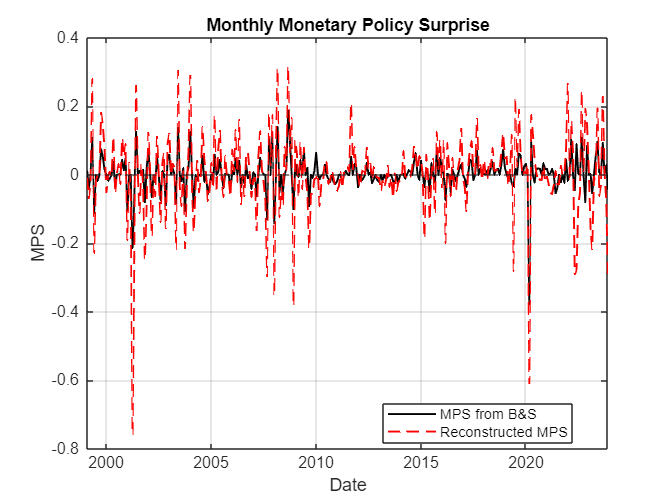


figure;
plot(commonDates, MPS_orig, 'k-', 'LineWidth', 1.2); hold on;
plot(commonDates, MPS_recon, 'r--', 'LineWidth', 1.2);
yline(0,'--');
grid on;
xlabel('Date'); ylabel('MPS');
title('Monthly Monetary Policy Surprise');
legend_str_MPS = sprintf('Reconstructed MPS');
legend({'MPS from B&S', legend_str_MPS}, 'Location', 'best');

ax = gca;
ax.XAxis.TickLabelFormat = 'yyyy';

The orthogonalized MPSs with all events is far more volatile than the Bauer & Swanson (with only statements) one, which was expected and is actually desirable.

### *4.2. Instrument strength*

    We want to perform a 2SLS regression to estimate our local projections for each horizon, but we first want to check if our instrument (orthogonalized MPS) is relevant. A rule of thumb is to check if the F-stat of the first stage regression is over 10 (if not, the instrument is considered weak). 

data_mat = [log(lp_data.IP), log(lp_data.CPI), ...
    lp_data.EBP, lp_data.x2yTreas];
var_names = {'IP (Log)', 'CPI (Log)', 'Excess Bond Premium', '2Y Treasury Yield'};

% Instrument = reconstructed orthogonalized MPS
MPS_vec = lp_data.MPS_ORTH_reconstructed;
[T, n_vars] = size(data_mat);
p = 12; % Number of lags
H = 50; % Horizon (50 months)

% LAG CONSTRUCTION
X_lags = [];
for i = 1:p
    X_lags = [X_lags, lagmatrix(data_mat, i)];
end

% We add a constant term
X_ctrl = [ones(T, 1), X_lags];

% We take valid observations (remove rows with NaNs in lags or instrument)
valid_idx = all(~isnan([data_mat, X_ctrl, MPS_vec]), 2);
Y_t = data_mat(valid_idx, :);
X_ctrl_t = X_ctrl(valid_idx, :);
Z_t = MPS_vec(valid_idx);

% 2-year yield at time t (endogenous)
R2Y_t = Y_t(:, 4);

%% FIRST STAGE REGRESSION
% R2Y_t = alpha + beta * MPS_t + gamma * Controls + u

% Build regressor matrix: [constant, MPS, controls (excluding constant)]
regressors_fs = [ones(size(Z_t)), Z_t, X_ctrl_t(:, 2:end)];

% Estimate first stage
Mdl_fs = fitlm(regressors_fs(:, 2:end), R2Y_t, 'Intercept', true);

% Huber-White standard errors
[VarCov_robust, se_robust, b_fs] = hac(Mdl_fs, "Type", "HC", ...
    "Weights", "HC0", "Display", "off");

% Fitted values
R2Y_hat = Mdl_fs.Fitted;

% F-Stat for instrument relevance
% Test H0: beta_MPS = 0
% Since only one instrument, F* = (t*)^2
beta_mps = b_fs(2);  % Coefficient on MPS (first regressor after intercept)
se_mps = se_robust(2);
t_stat_robust = beta_mps / se_mps;
F_stat = t_stat_robust^2;

fprintf('=== First Stage Results ===\n');

=== First Stage Results ===


fprintf('Coefficient on MPS: %.4f (se = %.4f)\n', beta_mps, se_mps);

Coefficient on MPS: 0.2317 (se = 0.1466)


fprintf('t-statistic: %.2f\n', t_stat_robust);

t-statistic: 1.58


fprintf('F-statistic: %.2f\n', F_stat);

F-statistic: 2.50


fprintf('Relevant instrument (F > 10): %s\n', string(F_stat > 10));

Relevant instrument (F > 10): false


The instrument is weak. 

### *4.3. Local projections*

Despite that, we will compute the local projections for test purposes. 

% Storage matrices
IRFs = zeros(H+1, n_vars);
SEs  = zeros(H+1, n_vars); % Newey-West Standard Errors

% We want the response to a 25 basis point shock.
% Since we regress on R2Y_hat (measured in percentage points), a coeff of 1 = 1pp increase.
% We scale this down to 25 bps.
scaling_factor = 0.25; 

fprintf('\nComputing Local Projections (h=0 to %d)...\n', H);


Computing Local Projections (h=0 to 50)...



for h = 0:H
    % Temporal Alignment for Horizon h
    
    % Get indices of regressors (time t)
    indices_t = find(valid_idx);
    
    % Get target indices (time t + h)
    indices_h = indices_t + h;
    
    valid_rows = indices_h <= T;
    
    % Effective sample for this specific horizon
    curr_idx_t = indices_t(valid_rows); 
    curr_idx_h = indices_h(valid_rows); 
    
    % Construct regression matrices for horizon h
    % Left hand side: Y_{t+h}
    Y_lhs = data_mat(curr_idx_h, :);
    
    % Right hand side: [R2Y_hat_t, Controls_t]
    % R2Y_hat was computed on the "valid_idx" sample, so we filter it again.
    X_rhs = [R2Y_hat(valid_rows), X_ctrl_t(valid_rows, :)];
    
    N_h = length(curr_idx_h);
    K   = size(X_rhs, 2);
    
    % IV Estimation (2nd Stage) via OLS on Fitted Values 
    invXtX = (X_rhs' * X_rhs) \ eye(K); 
    Betas = invXtX * (X_rhs' * Y_lhs);
    
    % Store the IRF 
    IRFs(h+1, :) = Betas(1, :) * scaling_factor;
    
    % Newey-West Standard Errors 
    Resids = Y_lhs - X_rhs * Betas;
   
    % We loop over each response variable (j) to compute HAC SEs
    for j = 1:n_vars
        u = Resids(:, j);
        
        % White Matrix (X' diag(u^2) X) 
        % Starting point for Omega
        Omega = X_rhs' * (X_rhs .* (u.^2));
        
        % Add Autocovariance terms 
        % Newey-West lag selection rule of thumb: h + 1
        L = h + 1; 
        
        for l = 1:L
            weight = 1 - l/(L+1);
            
            % Shifted matrices: X_t * u_t and X_{t-l} * u_{t-l}
            % We compute the cross-products directly
            Z = X_rhs .* u; % (N x K)
            
            % Covariance: Gamma_l + Gamma_l'
            Gamma_l = Z(l+1:end, :)' * Z(1:end-l, :);
            Omega = Omega + weight * (Gamma_l + Gamma_l');
        end
        
        % Variance-Covariance Matrix of Estimators: V = (X'X)^-1 Omega (X'X)^-1
        V_beta = invXtX * Omega * invXtX;
        
        % Standard Error of the coefficient of interest (1st element)
        se_j = sqrt(V_beta(1, 1));
        SEs(h+1, j) = se_j * scaling_factor;
    end
end
fprintf('Calculation complete.\n');

Calculation complete.


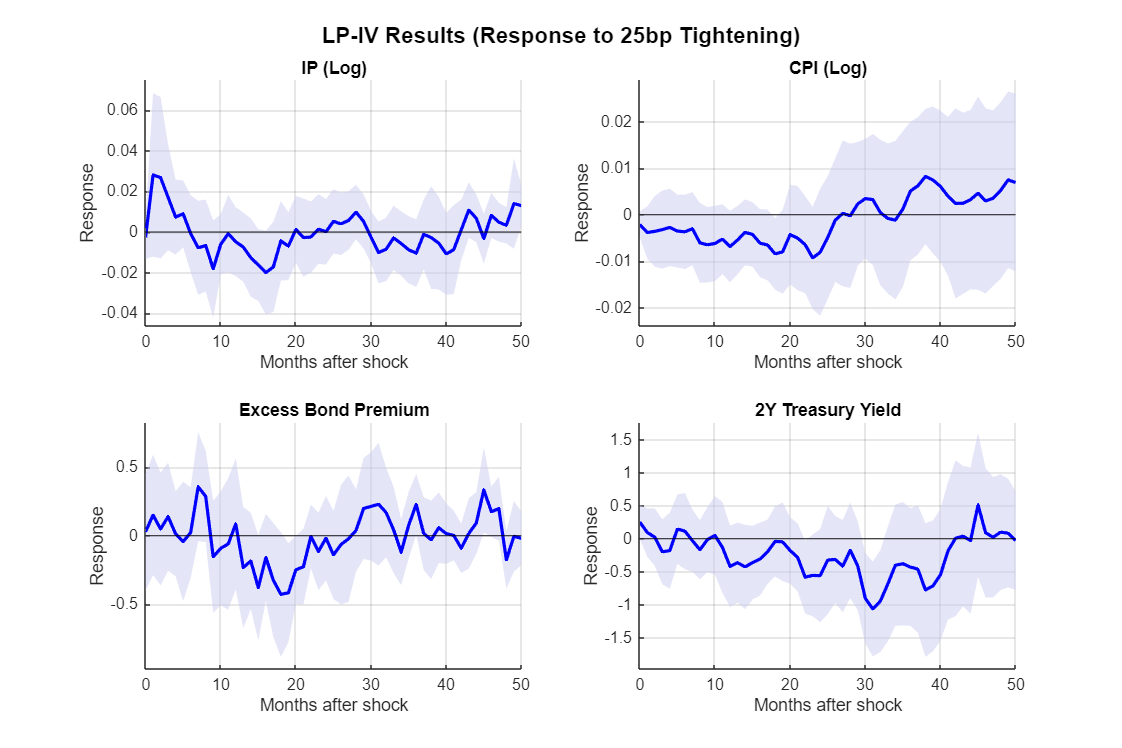


%% PLOTTING RESULTS
horizons = 0:H;
figure('Position', [100 100 1200 800], 'Color', 'w');

conf_val = 1.645; % 90% Confidence Interval

for j = 1:n_vars
    subplot(2, 2, j);
    hold on;
    
    % Confidence Bounds
    upper = IRFs(:,j) + conf_val * SEs(:,j);
    lower = IRFs(:,j) - conf_val * SEs(:,j);
    
    % Shaded Confidence Interval area
    x_fill = [horizons, fliplr(horizons)];
    y_fill = [upper', fliplr(lower')];
    fill(x_fill, y_fill, [0.8 0.8 0.95], 'EdgeColor', 'none', 'FaceAlpha', 0.5);
    
    % Impulse Response Line
    plot(horizons, IRFs(:,j), 'b-', 'LineWidth', 2);
    
    % Zero line
    yline(0, 'k-', 'LineWidth', 0.8);
    
    % Labels and formatting
    xlabel('Months after shock');
    ylabel('Response');
    title(var_names{j}, 'FontWeight', 'bold');
    grid on;
    axis tight;
    
    % Aesthetic adjustment for Y-axis limits
    yl = ylim;
    ylim([yl(1)-0.1*abs(yl(1)), yl(2)+0.1*abs(yl(2))]);
end

sgtitle('LP-IV Results (Response to 25bp Tightening)', 'FontSize', 14, 'FontWeight', 'bold');

%% ========================================================================
% LOCAL PROJECTIONS FOR HOM EVENTS ONLY
% ========================================================================

fprintf('\n\n================================================================================\n');

fprintf('LOCAL PROJECTIONS - HOM EVENTS ONLY (Monthly Aggregation)\n');

LOCAL PROJECTIONS - HOM EVENTS ONLY (Monthly Aggregation)


fprintf('================================================================================\n');


%% Step 1: Identify HOM events at daily level
% Use combined_data which has Target, Path, and raw MPS
fprintf('Total events in dataset: %d\n', height(combined_data));

Total events in dataset: 751



% Classify all events
[~, ~, indic_hom_all_events] = classifier_mp_events(...
    table(combined_data.Target, combined_data.Path, ...
    'VariableNames', {'Target', 'Path'}));

fprintf('HOM events: %d (%.1f%%)\n', ...
    sum(indic_hom_all_events), 100*sum(indic_hom_all_events)/height(combined_data));

HOM events: 293 (39.0%)



%% Step 2: Filter HOM events (keep only those with raw MPS available)
mask_hom = indic_hom_all_events & ~isnan(combined_data.MPS);
hom_events = combined_data(mask_hom, {'Date', 'MPS', 'Target', 'Path', 'Sheet'});

fprintf('\nHOM events with valid raw MPS: %d\n', height(hom_events));


HOM events with valid raw MPS: 293


fprintf('  Mean raw MPS: %.4f\n', mean(hom_events.MPS));

  Mean raw MPS: -0.0086


fprintf('  Std raw MPS: %.4f\n', std(hom_events.MPS));

  Std raw MPS: 0.0505


fprintf('  Date range: %s to %s\n', ...
    datestr(min(hom_events.Date)), datestr(max(hom_events.Date)));

  Date range: 24-Aug-1999 to 10-Dec-2025



% Display breakdown by sheet
fprintf('\nHOM events by type:\n');


HOM events by type:


for i = 1:length(sheet_names)
    n_sheet = sum(strcmp(hom_events.Sheet, sheet_names{i}));
    fprintf('  %s: %d (%.1f%%)\n', ...
        sheet_names{i}, n_sheet, 100*n_sheet/height(hom_events));
end

  Statements: 88 (30.0%)
  Press Conferences: 36 (12.3%)
  Monetary Events: 100 (34.1%)
  Minutes: 69 (23.5%)



%% Step 3: Monthly aggregation (sum RAW MPS across HOM events)
hom_events.MonthDate = dateshift(hom_events.Date, 'start', 'month');

% Sum raw MPS within each month
mps_monthly_sum = groupsummary(hom_events, "MonthDate", "sum", "MPS");
mps_monthly_sum.Properties.VariableNames = {'MonthDate', 'GroupCount', 'MPS'};

% Get first event date in each month (important for orthogonalization timing)
first_event_date = groupsummary(hom_events, "MonthDate", "min", "Date");
first_event_date.Properties.VariableNames = {'MonthDate', 'GroupCount', 'FirstEventDate'};

% Join
monthly_hom_raw = outerjoin(mps_monthly_sum(:, {'MonthDate', 'MPS'}), ...
    first_event_date(:, {'MonthDate', 'FirstEventDate'}), ...
    'Keys', 'MonthDate', 'MergeKeys', true);

fprintf('\n=== Monthly HOM aggregation (raw MPS) ===\n');


=== Monthly HOM aggregation (raw MPS) ===


fprintf('Months with HOM events: %d\n', height(monthly_hom_raw));

Months with HOM events: 165


fprintf('Mean monthly MPS (HOM): %.4f\n', mean(monthly_hom_raw.MPS));

Mean monthly MPS (HOM): -0.0153


fprintf('Std monthly MPS (HOM): %.4f\n', std(monthly_hom_raw.MPS));

Std monthly MPS (HOM): 0.0925



%% Step 4: Create full monthly timeline (fill non-HOM months with zeros)
start_month = dateshift(min(monthly_hom_raw.MonthDate), 'start', 'month');
end_month   = dateshift(max(monthly_hom_raw.MonthDate), 'start', 'month');
all_months  = (start_month : calmonths(1) : end_month)';

timeline_table = table(all_months, 'VariableNames', {'MonthDate'});

% Left join to keep all months
monthly_hom_full = outerjoin(timeline_table, monthly_hom_raw, ...
    'Type', 'left', 'Keys', 'MonthDate', 'MergeKeys', true);

% Fill missing MPS with zeros (months without HOM events)
monthly_hom_full.MPS(isnan(monthly_hom_full.MPS)) = 0;

% Assign proper dates for orthogonalization
% Use first event date if available, otherwise use month start
monthly_hom_full.Date = monthly_hom_full.MonthDate;
has_event = ~isnat(monthly_hom_full.FirstEventDate);
monthly_hom_full.Date(has_event) = monthly_hom_full.FirstEventDate(has_event);

fprintf('\n=== Full monthly timeline ===\n');


=== Full monthly timeline ===


fprintf('Total months: %d\n', height(monthly_hom_full));

Total months: 317


fprintf('Months with HOM events: %d (%.1f%%)\n', ...
    sum(has_event), 100*sum(has_event)/height(monthly_hom_full));

Months with HOM events: 165 (52.1%)


fprintf('Months with zero MPS: %d (%.1f%%)\n', ...
    sum(monthly_hom_full.MPS == 0), ...
    100*sum(monthly_hom_full.MPS == 0)/height(monthly_hom_full));

Months with zero MPS: 152 (47.9%)



%% Step 5: Orthogonalize the monthly HOM series
% THIS is where orthogonalization happens - after monthly aggregation
monthly_hom_table = table(monthly_hom_full.Date, monthly_hom_full.MPS, ...
    'VariableNames', {'Date', 'MPS'});

fprintf('\n=== Orthogonalizing monthly HOM MPS ===\n');


=== Orthogonalizing monthly HOM MPS ===


mps_hom_orth = orthogonalize_mps_BS2023(monthly_hom_table, macro_data, ...
    'MPSVarName', 'MPS', ...
    'Orthogonalize', true, ...
    'Verbose', true);


=== Bauer & Swanson (2023) Orthogonalization ===
MPS variable used: MPS
Original sample size: 317
Complete cases: 295 (93.1%)
Missing observations: 22
R² of MPS on macro variables: 0.0285
Adj. R²: 0.0117

Regression coefficients:
                    Estimate        SE         tStat       pValue  
                   __________    _________    ________    _________

    (Intercept)     -0.011666    0.0043024     -2.7115    0.0070982
    NFP_YoY          0.001658    0.0014974      1.1072      0.26911
    SP500_3m         0.039535     0.056849     0.69544      0.48734
    Slope_3m       -0.0013945    0.0018144    -0.76858      0.44277
    BCOM_3m          0.061612      0.04983      1.2364       0.2173
    Skew_Avg         0.016803     0.012461      1.3484


% Handle any remaining NaNs (fill with raw MPS)
mps_hom_orth.MPS_ORTH(isnan(mps_hom_orth.MPS_ORTH)) = ...
    mps_hom_orth.MPS(isnan(mps_hom_orth.MPS_ORTH));

fprintf('\n=== Orthogonalized HOM MPS statistics ===\n');


=== Orthogonalized HOM MPS statistics ===


fprintf('Mean MPS_ORTH: %.4f\n', mean(mps_hom_orth.MPS_ORTH));

Mean MPS_ORTH: -0.0003


fprintf('Std MPS_ORTH: %.4f\n', std(mps_hom_orth.MPS_ORTH));

Std MPS_ORTH: 0.0662


fprintf('Correlation (raw vs orth): %.4f\n', ...
    corr(mps_hom_orth.MPS, mps_hom_orth.MPS_ORTH));

Correlation (raw vs orth): 0.9857



% Count truly non-zero months (after orthogonalization)
nonzero_orth = abs(mps_hom_orth.MPS_ORTH) > 1e-10;
fprintf('Non-zero MPS_ORTH: %d (%.1f%%)\n', ...
    sum(nonzero_orth), 100*sum(nonzero_orth)/height(mps_hom_orth));

Non-zero MPS_ORTH: 305 (96.2%)



%% Step 6: Merge with B&S LP data
% Match dates with lp_data
lp_data.MPS_HOM_ORTH = nan(height(lp_data), 1);

[~, idx_lp, idx_hom] = intersect(lp_data.Dates, mps_hom_orth.Date);
lp_data.MPS_HOM_ORTH(idx_lp) = mps_hom_orth.MPS_ORTH(idx_hom);

% Fill remaining NaNs with zeros (months without any HOM events)
lp_data.MPS_HOM_ORTH(isnan(lp_data.MPS_HOM_ORTH)) = 0;

%% Step 7: Compare instruments
fprintf('\n=== INSTRUMENT COMPARISON ===\n');


=== INSTRUMENT COMPARISON ===



% Full sample (reconstructed)
fprintf('\nFull Sample MPS_ORTH_reconstructed:\n');


Full Sample MPS_ORTH_reconstructed:


fprintf('  Mean: %.4f, Std: %.4f\n', ...
    mean(lp_data.MPS_ORTH_reconstructed, 'omitnan'), ...
    std(lp_data.MPS_ORTH_reconstructed, 'omitnan'));

  Mean: 0.0030, Std: 0.1187


fprintf('  Non-missing: %d\n', sum(~isnan(lp_data.MPS_ORTH_reconstructed)));

  Non-missing: 321



% HOM only
fprintf('\nHOM MPS_ORTH:\n');


HOM MPS_ORTH:


fprintf('  Mean (all): %.4f, Std (all): %.4f\n', ...
    mean(lp_data.MPS_HOM_ORTH), std(lp_data.MPS_HOM_ORTH));

  Mean (all): 0.0025, Std (all): 0.0138


fprintf('  Mean (non-zero): %.4f, Std (non-zero): %.4f\n', ...
    mean(lp_data.MPS_HOM_ORTH(lp_data.MPS_HOM_ORTH ~= 0)), ...
    std(lp_data.MPS_HOM_ORTH(lp_data.MPS_HOM_ORTH ~= 0)));

  Mean (non-zero): 0.0056, Std (non-zero): 0.0202


fprintf('  Non-zero months: %d (%.1f%%)\n', ...
    sum(lp_data.MPS_HOM_ORTH ~= 0), ...
    100*sum(lp_data.MPS_HOM_ORTH ~= 0)/height(lp_data));

  Non-zero months: 145 (45.2%)



% Correlation (for non-zero HOM months)
valid_both = ~isnan(lp_data.MPS_ORTH_reconstructed) & (lp_data.MPS_HOM_ORTH ~= 0);
if sum(valid_both) > 0
    corr_val = corr(lp_data.MPS_ORTH_reconstructed(valid_both), ...
                    lp_data.MPS_HOM_ORTH(valid_both));
    fprintf('\nCorrelation (Full vs HOM, non-zero HOM months): %.4f\n', corr_val);
end


Correlation (Full vs HOM, non-zero HOM months): 0.1238



%% Step 9: First Stage Regression
data_mat_hom = [log(lp_data.IP), log(lp_data.CPI), ...
                lp_data.EBP, lp_data.x2yTreas];
var_names_hom = {'IP (Log)', 'CPI (Log)', 'Excess Bond Premium', '2Y Treasury Yield'};

MPS_hom_instrument = lp_data.MPS_HOM_ORTH;

[T_hom, n_vars_hom] = size(data_mat_hom);
p_hom = 12; % Number of lags
H_hom = 50; % Horizon

% Construct lags
X_lags_hom = [];
for i = 1:p_hom
    X_lags_hom = [X_lags_hom, lagmatrix(data_mat_hom, i)];
end
X_ctrl_hom = [ones(T_hom, 1), X_lags_hom];

% Valid observations
valid_idx_hom = all(~isnan([data_mat_hom, X_ctrl_hom, MPS_hom_instrument]), 2);
Y_t_hom      = data_mat_hom(valid_idx_hom, :);
X_ctrl_t_hom = X_ctrl_hom(valid_idx_hom, :);
Z_t_hom      = MPS_hom_instrument(valid_idx_hom);

R2Y_t_hom = Y_t_hom(:, 4); % 2-year yield

fprintf('\n=== First Stage Sample ===\n');


=== First Stage Sample ===


fprintf('Valid observations: %d\n', length(Z_t_hom));

Valid observations: 309


fprintf('Non-zero instrument values: %d (%.1f%%)\n', ...
    sum(abs(Z_t_hom) > 1e-10), 100*sum(abs(Z_t_hom) > 1e-10)/length(Z_t_hom));

Non-zero instrument values: 141 (45.6%)



% First stage: R2Y_t = alpha + beta*MPS_HOM_t + gamma*Controls + u
regressors_fs = [Z_t_hom, X_ctrl_t_hom];
b_fs_hom = regressors_fs \ R2Y_t_hom;
R2Y_hat_hom = regressors_fs * b_fs_hom;

% F-statistic
resid_fs = R2Y_t_hom - R2Y_hat_hom;
SSR_u = sum(resid_fs.^2);

b_r = X_ctrl_t_hom \ R2Y_t_hom;
resid_r = R2Y_t_hom - X_ctrl_t_hom * b_r;
SSR_r = sum(resid_r.^2);

df1 = 1;
df2 = length(R2Y_t_hom) - size(regressors_fs, 2);
F_stat_hom = ((SSR_r - SSR_u)/df1) / (SSR_u/df2);

fprintf('\n=== FIRST STAGE RESULTS ===\n');


=== FIRST STAGE RESULTS ===


fprintf('F-statistic (Full Sample): %.2f\n', F_stat);

F-statistic (Full Sample): 2.50


fprintf('F-statistic (HOM Only): %.2f\n', F_stat_hom);

F-statistic (HOM Only): 2.07


fprintf('\nFirst stage coefficient on instrument:\n');


First stage coefficient on instrument:


fprintf('  Full Sample: %.4f\n', b_fs(1));

  Full Sample: 2.6470


fprintf('  HOM Only: %.4f\n', b_fs_hom(1));

  HOM Only: -1.5634



%% Step 10: Local Projections
IRFs_hom = zeros(H_hom+1, n_vars_hom);
SEs_hom  = zeros(H_hom+1, n_vars_hom);
scaling_factor = 0.25; % 25 bp shock

fprintf('\nComputing Local Projections for HOM events (h=0 to %d)...\n', H_hom);


Computing Local Projections for HOM events (h=0 to 50)...



for h = 0:H_hom
    % Temporal alignment
    indices_t = find(valid_idx_hom);
    indices_h = indices_t + h;
    valid_rows = indices_h <= T_hom;
    
    curr_idx_t = indices_t(valid_rows);
    curr_idx_h = indices_h(valid_rows);
    
    % Regression matrices
    Y_lhs = data_mat_hom(curr_idx_h, :);
    X_rhs = [R2Y_hat_hom(valid_rows), X_ctrl_t_hom(valid_rows, :)];
    
    K = size(X_rhs, 2);
    
    % Second stage OLS
    invXtX = (X_rhs' * X_rhs) \ eye(K);
    Betas = invXtX * (X_rhs' * Y_lhs);
    
    % Store IRF
    IRFs_hom(h+1, :) = Betas(1, :) * scaling_factor;
    
    % Newey-West standard errors
    Resids = Y_lhs - X_rhs * Betas;
    
    for j = 1:n_vars_hom
        u = Resids(:, j);
        Omega = X_rhs' * (X_rhs .* (u.^2));
        
        L = h + 1;
        for l = 1:L
            weight = 1 - l/(L+1);
            Z = X_rhs .* u;
            Gamma_l = Z(l+1:end, :)' * Z(1:end-l, :);
            Omega = Omega + weight * (Gamma_l + Gamma_l');
        end
        
        V_beta = invXtX * Omega * invXtX;
        se_j = sqrt(V_beta(1, 1));
        SEs_hom(h+1, j) = se_j * scaling_factor;
    end
end

fprintf('LP-IV computation complete.\n');

LP-IV computation complete.


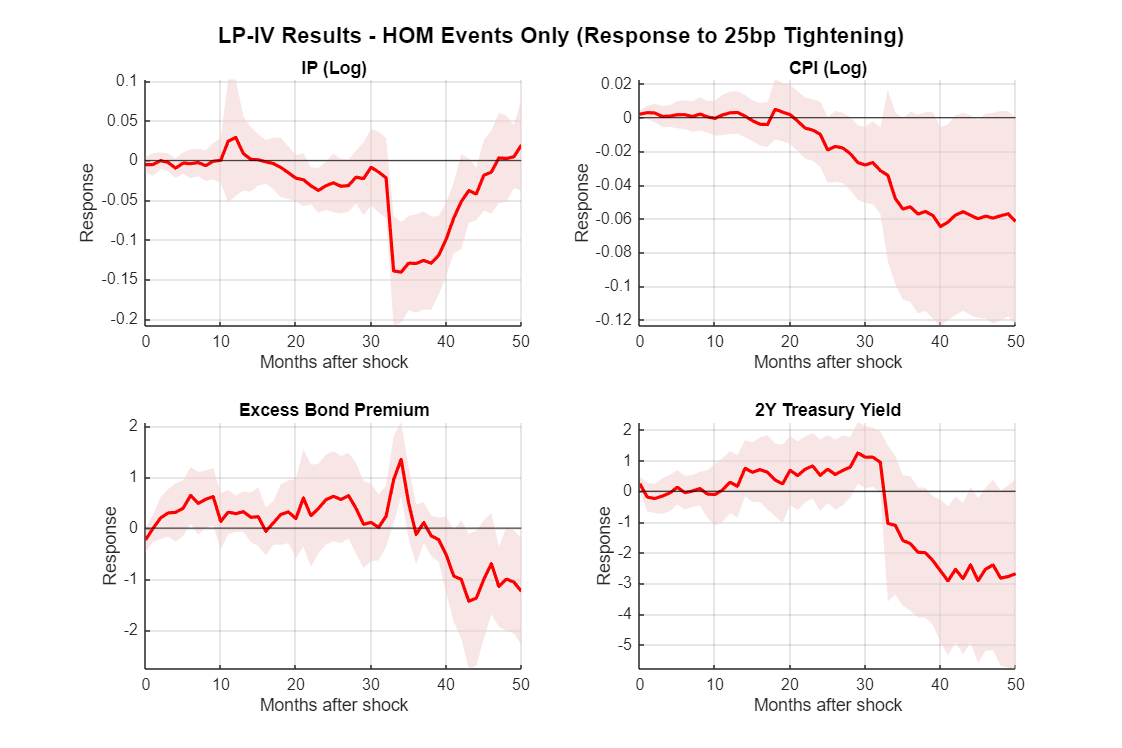


%% Step 11: Plot IRFs
horizons = 0:H_hom;
figure('Position', [100 100 1200 800], 'Color', 'w');

conf_val = 1.645; % 90% CI

for j = 1:n_vars_hom
    subplot(2, 2, j);
    hold on;
    
    % Confidence interval
    upper = IRFs_hom(:,j) + conf_val * SEs_hom(:,j);
    lower = IRFs_hom(:,j) - conf_val * SEs_hom(:,j);
    
    x_fill = [horizons, fliplr(horizons)];
    y_fill = [upper', fliplr(lower')];
    fill(x_fill, y_fill, [0.95 0.8 0.8], 'EdgeColor', 'none', 'FaceAlpha', 0.5);
    
    plot(horizons, IRFs_hom(:,j), 'r-', 'LineWidth', 2);
    yline(0, 'k-', 'LineWidth', 0.8);
    
    xlabel('Months after shock');
    ylabel('Response');
    title(var_names_hom{j}, 'FontWeight', 'bold');
    grid on;
    axis tight;
end

sgtitle('LP-IV Results - HOM Events Only (Response to 25bp Tightening)', ...
    'FontSize', 14, 'FontWeight', 'bold');

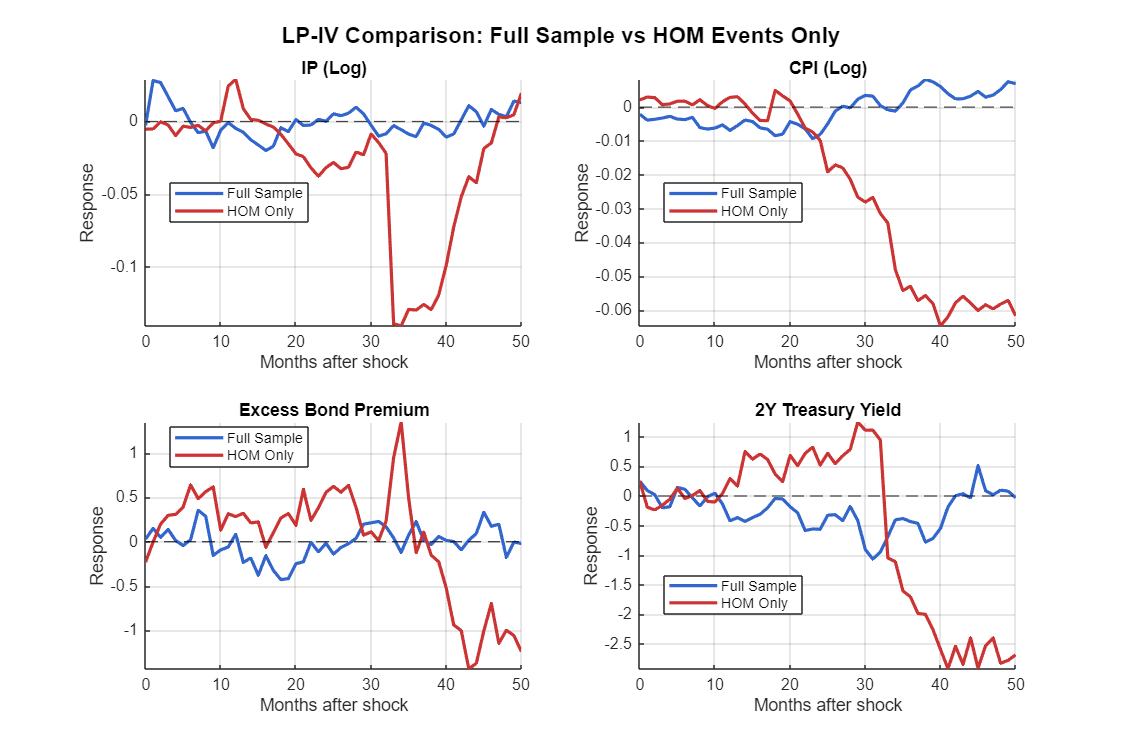


%% Step 12: Comparison plot
figure('Position', [150 150 1200 800], 'Color', 'w');

colors_comp = [0.2 0.4 0.8; 0.8 0.2 0.2];

for j = 1:n_vars_hom
    subplot(2, 2, j);
    hold on;
    
    % Full sample
    plot(horizons, IRFs(:,j), '-', 'Color', colors_comp(1,:), 'LineWidth', 2);
    
    % HOM only
    plot(horizons, IRFs_hom(:,j), '-', 'Color', colors_comp(2,:), 'LineWidth', 2);
    
    yline(0, 'k--', 'LineWidth', 0.8);
    
    xlabel('Months after shock');
    ylabel('Response');
    title(var_names_hom{j}, 'FontWeight', 'bold');
    grid on;
    legend({'Full Sample', 'HOM Only'}, 'Location', 'best');
    axis tight;
end

sgtitle('LP-IV Comparison: Full Sample vs HOM Events Only', ...
    'FontSize', 14, 'FontWeight', 'bold');